
addpath('siec_neuronowa\')

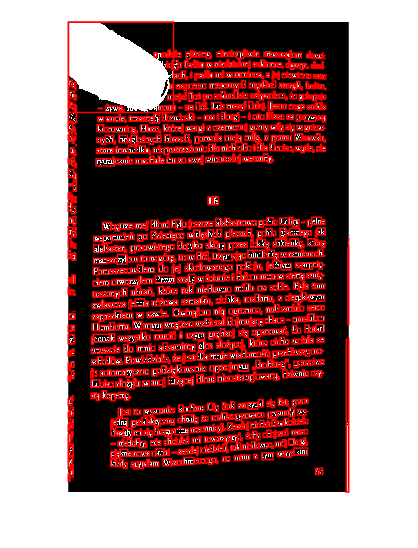

% Wczytaj obraz strony
pageImage = imread('Skan_20241005-1445.jpg');
grayImage = rgb2gray(pageImage); % Konwersja do odcieni szarości
bwImage = imbinarize(grayImage); % Binarne przetwarzanie obrazu (czarny/biały)

% Usuń tło
bwImage = imcomplement(bwImage); % Zamienia kolory tła i liter

% Znajdź obszary (znaki)
stats = regionprops(bwImage, 'BoundingBox', 'Image');

% Rysowanie obramowania dla każdego znaku (opcja podglądu)
imshow(bwImage);
hold on;
for k = 1 : length(stats)
    rectangle('Position', stats(k).BoundingBox, 'EdgeColor', 'r', 'LineWidth', 1);
end
hold off;

% Wczytaj wytrenowaną sieć
net = load('trainedNetwork.mat'); % Upewnij się, że to właściwy obiekt sieci
  % Dostosuj, jeśli struktura jest inna

disp(class(net));

struct


% Inicjalizacja zmiennej dla rozpoznanego tekstu
recognizedText = '';

% Przetwarzanie każdego znaku z obrazu
for k = 1 : length(stats)
    % Wyciągnij każdy znak z bounding box
    charImage = stats(k).Image;
    
    % Zmień rozmiar obrazu znaku, aby pasował do wejść sieci CNN
    charImageResized = imresize(charImage, [28 28]);
    %charImageResized = double(charImageResized) / 255; % Normalizacja do [0, 1]

    % Sprawdzenie wymiarów obrazu (RGB jeśli to konieczne)
    % if size(charImageResized, 3) == 1
    %     charImageResized = repmat(charImageResized, [1 1 3]); % Konwersja do RGB, jeśli potrzebne
    % end
    
    % Klasyfikacja znaku przy użyciu sieci CNN
    label=predict(net.TrainedNetwork,single(charImageResized))
  
    
    % Zakładając, że label to indeks
    recognizedText = strcat(recognizedText, char(label)); % Zamiana etykiety na znak
end

label = 1×10 single row vector
    0.7358    0.0708    0.0065    0.0008    0.0000    0.0005    0.0379    0.0000    0.1476    0.0000


label = 1×10 single row vector
    0.0000    0.0983    0.0006    0.0000    0.0000    0.0000    0.9006    0.0000    0.0004    0.0000


label = 1×10 single row vector
    0.0000    0.2630    0.0061    0.6894    0.0000    0.0008    0.0006    0.0001    0.0387    0.0014


label = 1×10 single row vector
    0.0000    0.0000    0.0000    0.9995    0.0000    0.0004    0.0000    0.0000    0.0001    0.0000


label = 1×10 single row vector
    0.0010    0.0270    0.3336    0.1504    0.0000    0.0000    0.0078    0.0000    0.4802    0.0000


label = 1×10 single row vector
    0.0000    0.0000    0.0001    0.0000    0.0000    0.0012    0.4547    0.0000    0.5439    0.0000


label = 1×10 single row vector
    0.0004    0.1330    0.0338    0.0000    0.0000    0.0000    0.8038    0.0000    0.0289    0.0000


label = 1×10 single row vector
    0.0001    0.1284    0.0045    0.7791    0.0000    0.0024    0.0001    0.0003    0.0329    0.0523


label = 1×10 single row vector
    0.0000    0.0001    0.0000    0.9982    0.0000    0.0001    0.0000    0.0000    0.0016    0.0000


label = 1×10 single row vector
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10 single row vector
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10 single row vector
    0.0000    0.0000    0.0000    0.9562    0.0000    0.0328    0.0001    0.0000    0.0109    0.0000


label = 1×10 single row vector
    0.0000    0.0000    0.0000    0.9991    0.0000    0.0002    0.0000    0.0000    0.0006    0.0001


label = 1×10 single row vector
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10 single row vector
    0.0001    0.0011    0.0001    0.0004    0.0000    0.0003    0.0014    0.0001    0.9963    0.0001


label = 1×10 single row vector
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10 single row vector
    0.0001    0.0374    0.0000    0.0081    0.0000    0.2504    0.5082    0.0000    0.1955    0.0002


label = 1×10 single row vector
    0.0000    0.0000    0.0000    0.9984    0.0000    0.0000    0.0000    0.0000    0.0016    0.0000


label = 1×10 single row vector
    0.0362    0.6001    0.0016    0.1154    0.0000    0.0369    0.0023    0.0003    0.2065    0.0006


label = 1×10 single row vector
    0.0002    0.9141    0.0021    0.0006    0.0000    0.0000    0.0827    0.0000    0.0003    0.0000


label = 1×10 single row vector
    0.0032    0.0048    0.0000    0.0001    0.0000    0.0488    0.6216    0.0000    0.3147    0.0067


label = 1×10 single row vector
    0.0300    0.0327    0.0151    0.2139    0.0000    0.0009    0.6364    0.0000    0.0682    0.0028


label = 1×10 single row vector
    0.0000    0.0367    0.5642    0.0001    0.0196    0.0000    0.0001    0.0013    0.3780    0.0000


label = 1×10 single row vector
    0.0008    0.0086    0.0002    0.0309    0.0000    0.0022    0.9517    0.0000    0.0057    0.0000


label = 1×10 single row vector
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10 single row vector
    0.0000    0.2923    0.4033    0.0028    0.0000    0.0002    0.2991    0.0000    0.0023    0.0000


label = 1×10 single row vector
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10 single row vector
    0.0025    0.2362    0.0018    0.0000    0.0000    0.0001    0.7523    0.0000    0.0071    0.0000


label = 1×10 single row vector
    0.0028    0.0023    0.0275    0.0000    0.0000    0.0012    0.9642    0.0000    0.0020    0.0000


label = 1×10 single row vector
    0.5856    0.3518    0.0001    0.0005    0.0000    0.0001    0.0034    0.0557    0.0027    0.0000


label = 1×10 single row vector
    0.0012    0.5758    0.0229    0.0675    0.0000    0.0037    0.0000    0.0008    0.3275    0.0006


label = 1×10 single row vector
    0.0404    0.0000    0.0013    0.0000    0.0001    0.0000    0.0000    0.0000    0.9580    0.0002


label = 1×10 single row vector
    0.0843    0.0000    0.9086    0.0000    0.0000    0.0000    0.0062    0.0000    0.0009    0.0000


label = 1×10 single row vector
    0.0152    0.7983    0.0026    0.0079    0.0000    0.0004    0.1606    0.0000    0.0148    0.0001


label = 1×10 single row vector
    0.0002    0.0004    0.0012    0.0000    0.0000    0.0000    0.9981    0.0000    0.0001    0.0000


label = 1×10 single row vector
    0.0000    0.0012    0.0000    0.5767    0.0001    0.0300    0.0160    0.0002    0.3718    0.0040


label = 1×10 single row vector
    0.9426    0.0000    0.0001    0.0000    0.0000    0.0000    0.0213    0.0000    0.0360    0.0000


label = 1×10 single row vector
    0.0063    0.0072    0.0650    0.0927    0.0000    0.0093    0.0028    0.0000    0.8135    0.0032


label = 1×10 single row vector
    0.1505    0.0022    0.0010    0.0325    0.0000    0.0008    0.0001    0.0001    0.7473    0.0655


label = 1×10 single row vector
    0.0002    0.0006    0.0000    0.0000    0.0000    0.0000    0.3776    0.0000    0.6216    0.0000


label = 1×10 single row vector
    0.0145    0.0006    0.0182    0.8531    0.0000    0.0099    0.0183    0.0000    0.0850    0.0003


label = 1×10 single row vector
    0.0122    0.1291    0.0505    0.0070    0.0000    0.0000    0.7612    0.0000    0.0398    0.0001


label = 1×10 single row vector
    0.1238    0.5696    0.0007    0.0014    0.0000    0.0001    0.2638    0.0005    0.0400    0.0001


label = 1×10 single row vector
    0.0415    0.0827    0.7539    0.0117    0.0000    0.0000    0.0989    0.0000    0.0112    0.0000


label = 1×10 single row vector
    0.0008    0.0035    0.0001    0.0000    0.0000    0.0116    0.7631    0.0000    0.2209    0.0000


label = 1×10 single row vector
    0.0000    0.0846    0.0046    0.7948    0.0002    0.0508    0.0038    0.0007    0.0528    0.0076


label = 1×10 single row vector
    0.0040    0.0820    0.0016    0.0017    0.0000    0.0001    0.0019    0.0000    0.9087    0.0000


label = 1×10 single row vector
    0.0009    0.0004    0.0049    0.2052    0.0000    0.7172    0.0060    0.0000    0.0652    0.0002


label = 1×10 single row vector
    0.0010    0.0155    0.0024    0.0144    0.0000    0.0083    0.0022    0.0000    0.9554    0.0008


label = 1×10 single row vector
    0.1546    0.0028    0.0008    0.0030    0.0000    0.0214    0.1833    0.0000    0.6340    0.0000


label = 1×10
    0.0000    0.4718    0.5261    0.0000    0.0000    0.0000    0.0020    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0000    0.9537    0.0301    0.0000    0.0000    0.0000    0.0000    0.0162    0.0000


label = 1×10
    0.0532    0.3239    0.0010    0.0024    0.0000    0.0091    0.5258    0.0000    0.0846    0.0001


label = 1×10
    0.0980    0.6723    0.0124    0.0013    0.0000    0.0000    0.0167    0.0000    0.1992    0.0000


label = 1×10
    0.0130    0.0787    0.0037    0.0005    0.0000    0.0001    0.0018    0.0000    0.9020    0.0002


label = 1×10
    0.0047    0.0004    0.0000    0.0000    0.0000    0.0028    0.2090    0.0000    0.7829    0.0001


label = 1×10
    0.1242    0.5490    0.2445    0.0007    0.0000    0.0000    0.0612    0.0107    0.0095    0.0002


label = 1×10
    0.0164    0.3744    0.0007    0.0054    0.0000    0.0001    0.5918    0.0000    0.0113    0.0000


label = 1×10
    0.0001    0.0001    0.0010    0.0000    0.0000    0.0006    0.3307    0.0000    0.6674    0.0000


label = 1×10
    0.0043    0.0043    0.7991    0.0018    0.0003    0.0003    0.1713    0.0000    0.0187    0.0000


label = 1×10
    0.0092    0.0001    0.0129    0.7360    0.0000    0.1276    0.0028    0.0000    0.1104    0.0009


label = 1×10
    0.0000    0.0001    0.0001    0.0026    0.0000    0.0000    0.6475    0.0000    0.3497    0.0000


label = 1×10
    0.0010    0.9340    0.0346    0.0177    0.0000    0.0000    0.0120    0.0001    0.0002    0.0002


label = 1×10
    0.0286    0.0000    0.0009    0.0023    0.0000    0.0113    0.0109    0.0000    0.9459    0.0001


label = 1×10
    0.0325    0.1257    0.0587    0.0000    0.0002    0.0000    0.7733    0.0000    0.0096    0.0000


label = 1×10
    0.0132    0.0001    0.0003    0.0000    0.0000    0.0000    0.2415    0.0000    0.7449    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0000    0.0000    0.0162    0.0011    0.0000    0.4307    0.0016    0.0000    0.5501    0.0003


label = 1×10
    0.1146    0.7535    0.0149    0.0011    0.0000    0.0000    0.1097    0.0000    0.0061    0.0000


label = 1×10
    0.0000    0.0024    0.0000    0.0054    0.0000    0.0003    0.2062    0.0000    0.7856    0.0000


label = 1×10
    0.3273    0.3657    0.1827    0.0013    0.0000    0.0000    0.1180    0.0047    0.0003    0.0000


label = 1×10
    0.5876    0.1615    0.0019    0.0005    0.0000    0.0006    0.1404    0.0000    0.1074    0.0000


label = 1×10
    0.0108    0.0000    0.0005    0.0000    0.0000    0.0001    0.0015    0.0000    0.9870    0.0000


label = 1×10
    0.0001    0.0559    0.0082    0.0000    0.0000    0.0002    0.8485    0.0000    0.0872    0.0000


label = 1×10
    0.0097    0.1927    0.0064    0.0104    0.0000    0.0002    0.7642    0.0000    0.0165    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.0129    0.0000    0.0000    0.0105    0.0000    0.9765    0.0000


label = 1×10
    0.0010    0.0024    0.0000    0.0000    0.0000    0.0026    0.9636    0.0000    0.0303    0.0000


label = 1×10
    0.0001    0.0045    0.0309    0.0013    0.0000    0.0001    0.7219    0.0000    0.2412    0.0000


label = 1×10
    0.0002    0.0255    0.9421    0.0085    0.0000    0.0000    0.0224    0.0000    0.0013    0.0000


label = 1×10
    0.7714    0.0505    0.0004    0.0013    0.0000    0.0004    0.1553    0.0001    0.0205    0.0001


label = 1×10
    0.0683    0.4893    0.0006    0.0025    0.0000    0.0002    0.4118    0.0000    0.0272    0.0000


label = 1×10
    0.0238    0.0000    0.0007    0.0000    0.0000    0.0004    0.0001    0.0000    0.9750    0.0000


label = 1×10
    0.0001    0.0000    0.0353    0.8360    0.0000    0.0000    0.0006    0.0000    0.1280    0.0000


label = 1×10
    0.0301    0.0116    0.0063    0.0006    0.0000    0.0116    0.2094    0.0000    0.7067    0.0237


label = 1×10
    0.0091    0.0057    0.0485    0.0004    0.0000    0.0008    0.0211    0.0000    0.9144    0.0000


label = 1×10
    0.0081    0.5037    0.0264    0.0714    0.0000    0.0030    0.0126    0.0000    0.3742    0.0004


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0323    0.0000    0.0031    0.0006    0.0000    0.0007    0.0001    0.0000    0.9632    0.0001


label = 1×10
    0.5955    0.3243    0.0044    0.0000    0.0004    0.0000    0.0006    0.0011    0.0734    0.0001


label = 1×10
    0.0043    0.9573    0.0046    0.0009    0.0000    0.0000    0.0318    0.0000    0.0010    0.0000


label = 1×10
    0.2465    0.0915    0.0024    0.0003    0.0006    0.0005    0.0612    0.0005    0.5718    0.0247


label = 1×10
    0.0213    0.0058    0.0001    0.0001    0.0001    0.0000    0.1185    0.0000    0.8523    0.0019


label = 1×10
    0.0004    0.8875    0.0697    0.0054    0.0000    0.0000    0.0316    0.0000    0.0054    0.0000


label = 1×10
    0.0660    0.0000    0.0017    0.0003    0.0000    0.0024    0.0002    0.0000    0.9292    0.0002


label = 1×10
    0.0042    0.1070    0.0041    0.6161    0.0000    0.0274    0.1492    0.0000    0.0920    0.0001


label = 1×10
    0.0780    0.7632    0.0506    0.0006    0.0000    0.0000    0.0544    0.0020    0.0478    0.0034


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.2553    0.2827    0.0008    0.0043    0.0000    0.0181    0.1909    0.0000    0.2478    0.0001


label = 1×10
    0.2426    0.6856    0.0008    0.0000    0.0000    0.0000    0.0678    0.0001    0.0031    0.0000


label = 1×10
    0.0081    0.9582    0.0051    0.0005    0.0004    0.0001    0.0155    0.0001    0.0116    0.0004


label = 1×10
    0.0000    0.0001    0.7499    0.0000    0.0000    0.0003    0.2487    0.0000    0.0010    0.0000


label = 1×10
    0.0000    0.0748    0.0657    0.8574    0.0000    0.0001    0.0000    0.0000    0.0013    0.0006


label = 1×10
    0.0008    0.0151    0.9251    0.0015    0.0000    0.0000    0.0574    0.0000    0.0001    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.2488    0.2751    0.0010    0.0004    0.0000    0.0041    0.1369    0.0000    0.3334    0.0003


label = 1×10
    0.1251    0.3782    0.0021    0.0021    0.0000    0.0095    0.2472    0.0000    0.2357    0.0001


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0001    0.0213    0.7499    0.0275    0.0001    0.0048    0.0914    0.0000    0.1036    0.0012


label = 1×10
    0.0397    0.1884    0.5245    0.0018    0.0000    0.0001    0.0100    0.0003    0.2202    0.0149


label = 1×10
    0.0016    0.0409    0.0596    0.0335    0.0000    0.0120    0.0058    0.0000    0.8446    0.0020


label = 1×10
    0.1711    0.6063    0.0188    0.0001    0.0000    0.0000    0.1251    0.0002    0.0781    0.0001


label = 1×10
    0.0764    0.2544    0.2628    0.0008    0.0000    0.0000    0.1791    0.0003    0.2197    0.0065


label = 1×10
    0.0092    0.3031    0.0000    0.0000    0.0000    0.0007    0.1003    0.0000    0.5867    0.0000


label = 1×10
    0.0159    0.0000    0.0014    0.0000    0.0000    0.0542    0.0037    0.0000    0.9248    0.0000


label = 1×10
    0.0384    0.3329    0.0020    0.0067    0.0000    0.0003    0.5979    0.0000    0.0217    0.0000


label = 1×10
    0.0002    0.0004    0.0017    0.0001    0.0000    0.0000    0.0051    0.0000    0.9925    0.0000


label = 1×10
    0.0016    0.0087    0.0278    0.9344    0.0000    0.0004    0.0121    0.0000    0.0150    0.0000


label = 1×10
    0.0096    0.8130    0.0030    0.0085    0.0000    0.0003    0.1520    0.0000    0.0134    0.0001


label = 1×10
    0.0000    0.0001    0.9999    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0057    0.0000    0.0040    0.0001    0.0000    0.0001    0.0001    0.0000    0.9900    0.0000


label = 1×10
    0.0387    0.0050    0.0091    0.0054    0.0000    0.0041    0.0067    0.0000    0.9309    0.0001


label = 1×10
    0.0000    0.1395    0.7927    0.0653    0.0000    0.0009    0.0002    0.0000    0.0013    0.0000


label = 1×10
    0.0000    0.2766    0.7096    0.0002    0.0000    0.0000    0.0125    0.0000    0.0010    0.0000


label = 1×10
    0.0052    0.2427    0.0073    0.6859    0.0000    0.0003    0.0448    0.0000    0.0137    0.0000


label = 1×10
    0.0282    0.2813    0.5848    0.0080    0.0000    0.0000    0.0417    0.0000    0.0559    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.7663    0.0650    0.0010    0.0002    0.0000    0.0002    0.0001    0.0000    0.1670    0.0001


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.6996    0.1766    0.0097    0.0000    0.0000    0.0000    0.0087    0.0007    0.1045    0.0001


label = 1×10
    0.0033    0.0003    0.0032    0.0000    0.0000    0.0337    0.2363    0.0000    0.7226    0.0006


label = 1×10
    0.4175    0.2427    0.0015    0.0009    0.0000    0.0008    0.2177    0.0000    0.1190    0.0000


label = 1×10
    0.0003    0.0199    0.0000    0.9644    0.0000    0.0074    0.0030    0.0000    0.0050    0.0000


label = 1×10
    0.0575    0.8391    0.0005    0.0001    0.0000    0.0001    0.0545    0.0000    0.0482    0.0000


label = 1×10
    0.0015    0.0422    0.0016    0.9487    0.0000    0.0038    0.0006    0.0002    0.0011    0.0003


label = 1×10
    0.0056    0.0465    0.0410    0.0072    0.0000    0.0000    0.8977    0.0000    0.0019    0.0000


label = 1×10
    0.0000    0.0045    0.3954    0.0000    0.0000    0.0000    0.5998    0.0000    0.0003    0.0000


label = 1×10
    0.0000    0.0278    0.0028    0.0157    0.0002    0.0452    0.3255    0.0000    0.5813    0.0013


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.2222    0.5853    0.0815    0.0036    0.0000    0.0000    0.0687    0.0008    0.0376    0.0003


label = 1×10
    0.0144    0.4477    0.0126    0.2478    0.0000    0.0093    0.0804    0.0000    0.1877    0.0001


label = 1×10
    0.0208    0.5329    0.4134    0.0002    0.0000    0.0000    0.0103    0.0006    0.0210    0.0007


label = 1×10
    0.1421    0.2589    0.0238    0.0138    0.0000    0.0075    0.1936    0.0000    0.3604    0.0000


label = 1×10
    0.1859    0.5055    0.0033    0.0308    0.0000    0.0011    0.2380    0.0000    0.0349    0.0003


label = 1×10
    0.0001    0.9306    0.0632    0.0000    0.0000    0.0000    0.0048    0.0000    0.0012    0.0000


label = 1×10
    0.0000    0.0049    0.0000    0.9815    0.0000    0.0122    0.0000    0.0000    0.0014    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0063    0.0002    0.0137    0.0000    0.0002    0.9365    0.0000    0.0430    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0137    0.0000    0.3538    0.0428    0.0000    0.5898    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.1145    0.0000    0.8765    0.0090


label = 1×10
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0029    0.0000    0.0000    0.0006    0.0013    0.0571    0.0000    0.9378    0.0003


label = 1×10
    0.0142    0.3911    0.0233    0.0096    0.0000    0.0000    0.5593    0.0000    0.0025    0.0000


label = 1×10
    0.0000    0.0088    0.0000    0.1596    0.0000    0.0013    0.4043    0.0000    0.4228    0.0032


label = 1×10
    0.0000    0.0001    0.0346    0.9564    0.0000    0.0000    0.0060    0.0000    0.0029    0.0000


label = 1×10
    0.0000    0.0013    0.0008    0.0033    0.0002    0.0000    0.0166    0.0003    0.9771    0.0004


label = 1×10
    0.0244    0.0476    0.0518    0.0030    0.0000    0.0000    0.8539    0.0000    0.0192    0.0000


label = 1×10
    0.0747    0.0074    0.2485    0.0002    0.0000    0.0006    0.5400    0.0000    0.1286    0.0000


label = 1×10
    0.0001    0.0013    0.0028    0.9524    0.0000    0.0000    0.0409    0.0000    0.0009    0.0015


label = 1×10
    0.0007    0.0000    0.0013    0.0000    0.0000    0.0000    0.8815    0.0000    0.1165    0.0000


label = 1×10
    0.0067    0.0004    0.0109    0.4588    0.0000    0.1410    0.0385    0.0000    0.3423    0.0014


label = 1×10
    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.1900    0.0000    0.8096    0.0000


label = 1×10
    0.0055    0.0004    0.0457    0.0002    0.0000    0.0003    0.7018    0.0000    0.2460    0.0000


label = 1×10
    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0653    0.0000    0.9346    0.0000


label = 1×10
    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0000    0.9991    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0032    0.0001    0.0001    0.0051    0.0000    0.9912    0.0002


label = 1×10
    0.0148    0.0001    0.0001    0.0012    0.0000    0.0000    0.9415    0.0000    0.0424    0.0000


label = 1×10
    0.0000    0.0000    0.0002    0.9986    0.0000    0.0000    0.0004    0.0000    0.0008    0.0001


label = 1×10
    0.4629    0.0000    0.0074    0.0000    0.0000    0.0000    0.5138    0.0000    0.0159    0.0000


label = 1×10
    0.0000    0.0000    0.0278    0.9708    0.0000    0.0000    0.0000    0.0000    0.0014    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.1193    0.0000    0.8580    0.0119    0.0000    0.0107    0.0001


label = 1×10
    0.4142    0.1363    0.0038    0.0421    0.0000    0.0008    0.3520    0.0016    0.0455    0.0036


label = 1×10
    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.2343    0.0000    0.7657    0.0000


label = 1×10
    0.0228    0.1101    0.1287    0.1643    0.0000    0.0000    0.5685    0.0000    0.0056    0.0000


label = 1×10
    0.0001    0.0025    0.0001    0.0000    0.0000    0.0000    0.0148    0.0000    0.9825    0.0000


label = 1×10
    0.0001    0.0317    0.0000    0.0312    0.0000    0.0387    0.7302    0.0000    0.1673    0.0008


label = 1×10
    0.1695    0.7397    0.0004    0.0002    0.0000    0.0000    0.0483    0.0000    0.0420    0.0000


label = 1×10
    0.0038    0.0007    0.0004    0.0278    0.0000    0.0005    0.9635    0.0000    0.0032    0.0000


label = 1×10
    0.0012    0.0001    0.0015    0.2503    0.0000    0.1681    0.2102    0.0000    0.3673    0.0012


label = 1×10
    0.0001    0.0010    0.0000    0.0000    0.0000    0.0000    0.9983    0.0000    0.0007    0.0000


label = 1×10
    0.0407    0.0005    0.0792    0.0000    0.0000    0.0000    0.8649    0.0000    0.0147    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.7677    0.0000    0.1823    0.0017    0.0000    0.0483    0.0000


label = 1×10
    0.1044    0.0016    0.7452    0.0000    0.0000    0.0003    0.1223    0.0000    0.0261    0.0000


label = 1×10
    0.0001    0.0000    0.0013    0.9503    0.0000    0.0028    0.0009    0.0000    0.0440    0.0005


label = 1×10
    0.0877    0.0928    0.0002    0.1640    0.0000    0.0022    0.6494    0.0000    0.0035    0.0002


label = 1×10
    0.0000    0.0000    0.0001    0.9991    0.0000    0.0000    0.0001    0.0000    0.0008    0.0000


label = 1×10
    0.0002    0.2478    0.0003    0.0081    0.0000    0.0008    0.3669    0.0001    0.3756    0.0001


label = 1×10
    0.0000    0.0397    0.5607    0.1713    0.0000    0.0041    0.0005    0.0002    0.2233    0.0001


label = 1×10
    0.0000    0.0003    0.0016    0.0000    0.0000    0.0000    0.9866    0.0000    0.0116    0.0000


label = 1×10
    0.0033    0.0001    0.0000    0.0104    0.0000    0.0002    0.9784    0.0000    0.0076    0.0000


label = 1×10
    0.0001    0.1162    0.0002    0.2429    0.0000    0.0011    0.3880    0.0000    0.2512    0.0002


label = 1×10
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0010    0.0000    0.9989    0.0000


label = 1×10
    0.0000    0.0263    0.0004    0.3698    0.0000    0.0004    0.3837    0.0000    0.2172    0.0021


label = 1×10
    0.0417    0.3150    0.3114    0.0037    0.0000    0.0000    0.3191    0.0000    0.0091    0.0000


label = 1×10
    0.0051    0.0047    0.0072    0.0002    0.0000    0.0001    0.3750    0.0000    0.6077    0.0000


label = 1×10
    0.0011    0.0074    0.0000    0.0001    0.0000    0.0000    0.2032    0.0000    0.7882    0.0001


label = 1×10
    0.0000    0.0004    0.2201    0.7206    0.0000    0.0000    0.0492    0.0000    0.0096    0.0000


label = 1×10
    0.0001    0.0019    0.0000    0.0016    0.0000    0.0302    0.8809    0.0000    0.0852    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.3428    0.0000    0.5632    0.0176    0.0000    0.0763    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.2311    0.2060    0.0018    0.0435    0.0000    0.0014    0.4920    0.0000    0.0235    0.0007


label = 1×10
    0.0000    0.3931    0.2820    0.0958    0.0000    0.0001    0.2171    0.0000    0.0119    0.0000


label = 1×10
    0.0017    0.0000    0.0051    0.5045    0.0000    0.0178    0.0040    0.0000    0.4612    0.0058


label = 1×10
    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0149    0.2840    0.1441    0.0222    0.0000    0.0000    0.5242    0.0000    0.0106    0.0000


label = 1×10
    0.0000    0.0009    0.0001    0.6626    0.0000    0.0022    0.0001    0.0009    0.3197    0.0135


label = 1×10
    0.0053    0.0000    0.0001    0.0000    0.0000    0.0000    0.0879    0.0000    0.9067    0.0000


label = 1×10
    0.0048    0.0005    0.0002    0.0264    0.0000    0.0009    0.9578    0.0000    0.0095    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9998    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0002    0.0000    0.0000    0.0169    0.0000    0.0000    0.1364    0.0000    0.8463    0.0002


label = 1×10
    0.0000    0.0000    0.0000    0.5412    0.0000    0.4524    0.0006    0.0000    0.0059    0.0000


label = 1×10
    0.0074    0.0004    0.0003    0.0055    0.0000    0.0001    0.9754    0.0000    0.0110    0.0000


label = 1×10
    0.0000    0.0000    0.0110    0.9881    0.0000    0.0000    0.0003    0.0000    0.0006    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.1631    0.0000    0.8152    0.0051    0.0000    0.0166    0.0000


label = 1×10
    0.0470    0.6286    0.0089    0.0258    0.0000    0.0006    0.2490    0.0000    0.0399    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.4551    0.0000    0.5096    0.0029    0.0000    0.0324    0.0000


label = 1×10
    0.0000    0.0000    0.0014    0.9983    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000


label = 1×10
    0.0001    0.0034    0.0001    0.0044    0.0000    0.0000    0.8873    0.0000    0.1047    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.4786    0.0000    0.5170    0.0013    0.0000    0.0031    0.0000


label = 1×10
    0.0018    0.0006    0.5440    0.0001    0.0000    0.0010    0.3241    0.0000    0.1283    0.0000


label = 1×10
    0.0099    0.0002    0.0199    0.1653    0.0000    0.0877    0.0407    0.0000    0.6754    0.0009


label = 1×10
    0.0000    0.0000    0.0001    0.9991    0.0000    0.0000    0.0001    0.0000    0.0007    0.0001


label = 1×10
    0.0000    0.0007    0.2498    0.6157    0.0000    0.0000    0.1268    0.0000    0.0070    0.0000


label = 1×10
    0.0000    0.0002    0.0000    0.0028    0.0000    0.0068    0.9174    0.0000    0.0727    0.0000


label = 1×10
    0.0000    0.0004    0.0004    0.0000    0.0000    0.0000    0.9482    0.0000    0.0510    0.0000


label = 1×10
    0.0002    0.0002    0.0009    0.0000    0.0000    0.0006    0.9955    0.0000    0.0024    0.0001


label = 1×10
    0.0972    0.0070    0.0000    0.0010    0.0000    0.0003    0.8869    0.0000    0.0076    0.0000


label = 1×10
    0.0074    0.4297    0.0003    0.4421    0.0000    0.0006    0.0770    0.0016    0.0058    0.0353


label = 1×10
    0.0149    0.0000    0.0203    0.0000    0.0000    0.0000    0.8974    0.0000    0.0674    0.0000


label = 1×10
    0.0000    0.0001    0.0274    0.9711    0.0000    0.0000    0.0008    0.0000    0.0006    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.5831    0.0000    0.4169    0.0000


label = 1×10
    0.3362    0.2282    0.0103    0.1405    0.0000    0.0008    0.2477    0.0008    0.0282    0.0073


label = 1×10
    0.0452    0.5104    0.0231    0.1690    0.0000    0.0023    0.2193    0.0000    0.0293    0.0014


label = 1×10
    0.0429    0.0000    0.0290    0.0000    0.0000    0.0000    0.9006    0.0000    0.0275    0.0000


label = 1×10
    0.0043    0.0001    0.0001    0.0049    0.0000    0.0002    0.9751    0.0000    0.0153    0.0000


label = 1×10
    0.0179    0.0001    0.0001    0.0032    0.0000    0.0001    0.9522    0.0000    0.0265    0.0000


label = 1×10
    0.0000    0.0004    0.0000    0.9995    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000


label = 1×10
    0.0001    0.0001    0.0000    0.9991    0.0000    0.0000    0.0004    0.0000    0.0003    0.0000


label = 1×10
    0.0000    0.0000    0.0035    0.9938    0.0000    0.0000    0.0025    0.0000    0.0001    0.0000


label = 1×10
    0.0003    0.0005    0.0000    0.0000    0.0000    0.0000    0.4865    0.0000    0.5125    0.0000


label = 1×10
    0.0238    0.1940    0.6186    0.0136    0.0000    0.0000    0.1423    0.0000    0.0076    0.0000


label = 1×10
    0.0107    0.0002    0.0000    0.0094    0.0000    0.0002    0.9644    0.0000    0.0152    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.3288    0.0000    0.6596    0.0018    0.0000    0.0098    0.0000


label = 1×10
    0.6124    0.1470    0.0018    0.0007    0.0000    0.0000    0.2213    0.0000    0.0167    0.0001


label = 1×10
    0.0490    0.0016    0.0215    0.4623    0.0000    0.0576    0.1067    0.0000    0.2983    0.0031


label = 1×10
    0.0183    0.5688    0.0529    0.0152    0.0000    0.0001    0.3398    0.0000    0.0049    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.5986    0.0000    0.3916    0.0014    0.0000    0.0084    0.0000


label = 1×10
    0.0001    0.0002    0.0018    0.0002    0.0000    0.0023    0.9905    0.0000    0.0048    0.0001


label = 1×10
    0.0000    0.5837    0.1344    0.1808    0.0000    0.0001    0.0929    0.0000    0.0081    0.0000


label = 1×10
    0.0010    0.2985    0.5800    0.0849    0.0000    0.0002    0.0343    0.0001    0.0011    0.0000


label = 1×10
    0.0001    0.0001    0.0030    0.0007    0.0000    0.0006    0.9935    0.0000    0.0018    0.0001


label = 1×10
    0.0775    0.4259    0.0872    0.1529    0.0000    0.0000    0.2316    0.0002    0.0247    0.0000


label = 1×10
    0.0000    0.4405    0.0572    0.4199    0.0000    0.0001    0.0811    0.0000    0.0012    0.0001


label = 1×10
    0.0007    0.0000    0.0013    0.0000    0.0000    0.0001    0.9920    0.0000    0.0059    0.0000


label = 1×10
    0.0020    0.0014    0.0000    0.0097    0.0000    0.0015    0.6746    0.0000    0.3103    0.0004


label = 1×10
    0.0408    0.0002    0.4115    0.0000    0.0000    0.0001    0.4811    0.0000    0.0663    0.0000


label = 1×10
    0.0000    0.3702    0.0008    0.0147    0.0000    0.0008    0.2137    0.0000    0.3997    0.0000


label = 1×10
    0.0012    0.0003    0.0016    0.5523    0.0000    0.0673    0.1583    0.0000    0.2171    0.0019


label = 1×10
    0.0001    0.0047    0.0014    0.8228    0.0000    0.0005    0.1267    0.0000    0.0438    0.0000


label = 1×10
    0.0001    0.0053    0.0000    0.0000    0.0002    0.0000    0.0355    0.0000    0.9589    0.0000


label = 1×10
    0.0174    0.2282    0.0043    0.0250    0.0000    0.0002    0.6749    0.0000    0.0499    0.0000


label = 1×10
    0.0145    0.4258    0.0120    0.0164    0.0000    0.0001    0.4987    0.0000    0.0326    0.0000


label = 1×10
    0.0000    0.0107    0.0002    0.4252    0.0000    0.0005    0.0878    0.0000    0.4682    0.0074


label = 1×10
    0.0034    0.0002    0.0108    0.2445    0.0000    0.1299    0.0545    0.0000    0.5500    0.0067


label = 1×10
    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0560    0.0000    0.9436    0.0003


label = 1×10
    0.0000    0.0014    0.0000    0.0009    0.0000    0.0000    0.9119    0.0000    0.0859    0.0000


label = 1×10
    0.0000    0.0000    0.0004    0.9874    0.0000    0.0000    0.0006    0.0000    0.0110    0.0006


label = 1×10
    0.0000    0.0000    0.7330    0.0005    0.0000    0.0131    0.2408    0.0000    0.0088    0.0037


label = 1×10
    0.0000    0.0000    0.0204    0.9769    0.0000    0.0000    0.0025    0.0000    0.0002    0.0000


label = 1×10
    0.0026    0.0002    0.0040    0.2635    0.0000    0.4061    0.0681    0.0000    0.2543    0.0012


label = 1×10
    0.0078    0.2291    0.0039    0.0103    0.0000    0.0005    0.7390    0.0000    0.0092    0.0001


label = 1×10
    0.0005    0.0002    0.0000    0.0014    0.0002    0.0001    0.0275    0.0000    0.9683    0.0018


label = 1×10
    0.0000    0.0000    0.0042    0.9941    0.0000    0.0000    0.0004    0.0000    0.0013    0.0000


label = 1×10
    0.1403    0.0000    0.0017    0.0005    0.0000    0.0000    0.0534    0.0000    0.8041    0.0000


label = 1×10
    0.0020    0.0000    0.0081    0.0895    0.0000    0.0059    0.0023    0.0000    0.8917    0.0003


label = 1×10
    0.0000    0.0000    0.4243    0.0008    0.0000    0.0415    0.5041    0.0000    0.0292    0.0001


label = 1×10
    0.0115    0.0166    0.0167    0.0237    0.0018    0.0006    0.0005    0.3848    0.5433    0.0005


label = 1×10
    0.0019    0.0000    0.0105    0.6699    0.0000    0.0331    0.0110    0.0000    0.2716    0.0020


label = 1×10
    0.0000    0.0001    0.0116    0.9830    0.0000    0.0000    0.0044    0.0000    0.0009    0.0000


label = 1×10
    0.0016    0.0124    0.0001    0.0327    0.0000    0.0000    0.0654    0.0000    0.8870    0.0007


label = 1×10
    0.0000    0.4045    0.0003    0.5941    0.0000    0.0000    0.0005    0.0003    0.0002    0.0000


label = 1×10
    0.0001    0.0091    0.0000    0.0000    0.0003    0.0000    0.0050    0.0000    0.9854    0.0001


label = 1×10
    0.0001    0.0102    0.0000    0.0000    0.0007    0.0000    0.0109    0.0000    0.9779    0.0001


label = 1×10
    0.0006    0.0254    0.0008    0.0144    0.0000    0.0001    0.0960    0.0030    0.8239    0.0356


label = 1×10
    0.0005    0.0000    0.0001    0.1272    0.0000    0.0004    0.1156    0.0000    0.7169    0.0393


label = 1×10
    0.0082    0.0942    0.0000    0.8831    0.0000    0.0004    0.0022    0.0011    0.0044    0.0064


label = 1×10
    0.0001    0.0002    0.0007    0.0001    0.0000    0.0014    0.9942    0.0000    0.0032    0.0000


label = 1×10
    0.0135    0.2460    0.0001    0.6135    0.0000    0.0006    0.0023    0.0020    0.1136    0.0082


label = 1×10
    0.0000    0.0042    0.0408    0.0006    0.0000    0.0001    0.2004    0.0000    0.7536    0.0001


label = 1×10
    0.0636    0.6199    0.0076    0.0163    0.0000    0.0021    0.2518    0.0000    0.0387    0.0001


label = 1×10
    0.0293    0.2542    0.0045    0.1887    0.0000    0.0020    0.0270    0.0013    0.4912    0.0018


label = 1×10
    0.0000    0.0333    0.8535    0.0836    0.0000    0.0003    0.0028    0.0039    0.0223    0.0003


label = 1×10
    0.0001    0.0002    0.0001    0.9988    0.0000    0.0000    0.0003    0.0000    0.0005    0.0000


label = 1×10
    0.0016    0.0002    0.0001    0.0006    0.0000    0.0003    0.8626    0.0000    0.1343    0.0002


label = 1×10
    0.0048    0.0007    0.0108    0.0575    0.0000    0.3537    0.1913    0.0000    0.3798    0.0013


label = 1×10
    0.0155    0.2244    0.0285    0.0007    0.0000    0.0000    0.7126    0.0000    0.0182    0.0000


label = 1×10
    0.0112    0.0001    0.0475    0.2416    0.0000    0.0158    0.0408    0.0000    0.6343    0.0087


label = 1×10
    0.0164    0.2521    0.2568    0.0553    0.0000    0.0000    0.4170    0.0000    0.0024    0.0000


label = 1×10
    0.0031    0.0008    0.0021    0.0000    0.0000    0.0000    0.9938    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9997    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000


label = 1×10
    0.0070    0.0001    0.0121    0.1054    0.0000    0.0019    0.0139    0.0000    0.8595    0.0002


label = 1×10
    0.0017    0.0001    0.0008    0.0370    0.0000    0.1657    0.4702    0.0000    0.3239    0.0008


label = 1×10
    0.0082    0.0001    0.0000    0.0029    0.0000    0.0002    0.9692    0.0000    0.0194    0.0000


label = 1×10
    0.0000    0.0076    0.0000    0.0000    0.0002    0.0000    0.0299    0.0000    0.9623    0.0000


label = 1×10
    0.0001    0.0458    0.0000    0.0210    0.0000    0.0695    0.8297    0.0000    0.0308    0.0030


label = 1×10
    0.0000    0.0000    0.0002    0.9980    0.0000    0.0000    0.0002    0.0000    0.0015    0.0002


label = 1×10
    0.0350    0.1296    0.4013    0.0085    0.0000    0.0000    0.4201    0.0000    0.0054    0.0000


label = 1×10
    0.0122    0.9205    0.0366    0.0037    0.0000    0.0007    0.0225    0.0003    0.0035    0.0001


label = 1×10
    0.0175    0.0000    0.0008    0.0004    0.0000    0.0000    0.0004    0.0000    0.9809    0.0000


label = 1×10
    0.0325    0.1714    0.1369    0.1122    0.0000    0.0000    0.5361    0.0000    0.0108    0.0001


label = 1×10
    0.0001    0.4808    0.0017    0.0678    0.0003    0.0008    0.1447    0.0005    0.3028    0.0006


label = 1×10
    0.0048    0.0007    0.0088    0.0000    0.0000    0.0000    0.9855    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0003    0.0001    0.9984    0.0000    0.0004    0.0003    0.0000    0.0004    0.0000


label = 1×10
    0.0358    0.0002    0.0799    0.1752    0.0000    0.0162    0.0201    0.0000    0.6709    0.0018


label = 1×10
    0.0002    0.1536    0.5885    0.2547    0.0000    0.0003    0.0014    0.0000    0.0012    0.0000


label = 1×10
    0.0035    0.0003    0.0001    0.0151    0.0000    0.0001    0.9767    0.0000    0.0043    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9997    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.5074    0.0000    0.4389    0.0008    0.0000    0.0530    0.0000


label = 1×10
    0.0000    0.0000    0.0133    0.0000    0.0000    0.0035    0.9822    0.0000    0.0009    0.0000


label = 1×10
    0.0037    0.8508    0.0096    0.0073    0.0000    0.0280    0.0631    0.0000    0.0367    0.0008


label = 1×10
    0.0003    0.0000    0.0012    0.0000    0.0000    0.0000    0.9485    0.0000    0.0499    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.3715    0.0000    0.6161    0.0014    0.0000    0.0110    0.0000


label = 1×10
    0.0009    0.0009    0.0169    0.6458    0.0000    0.1906    0.0370    0.0000    0.1066    0.0013


label = 1×10
    0.0000    0.0001    0.0002    0.2432    0.0000    0.0007    0.2127    0.0000    0.5431    0.0000


label = 1×10
    0.0005    0.4312    0.0896    0.2766    0.0000    0.0003    0.2007    0.0000    0.0006    0.0004


label = 1×10
    0.0000    0.0539    0.0250    0.5721    0.0001    0.0014    0.0005    0.0016    0.3410    0.0044


label = 1×10
    0.0100    0.0075    0.2260    0.0111    0.0000    0.0000    0.0415    0.0000    0.7034    0.0004


label = 1×10
    0.0205    0.6630    0.1769    0.0030    0.0000    0.0000    0.1294    0.0000    0.0071    0.0000


label = 1×10
    0.0057    0.0002    0.0022    0.2075    0.0000    0.1640    0.1017    0.0000    0.5158    0.0028


label = 1×10
    0.0080    0.0002    0.0001    0.0214    0.0000    0.0002    0.9628    0.0000    0.0073    0.0000


label = 1×10
    0.0144    0.7184    0.0021    0.0006    0.0000    0.0000    0.2633    0.0000    0.0012    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9990    0.0000    0.0000    0.0000    0.0000    0.0007    0.0003


label = 1×10
    0.0000    0.0000    0.0085    0.9906    0.0000    0.0000    0.0002    0.0000    0.0006    0.0000


label = 1×10
    0.0047    0.0002    0.0273    0.3693    0.0000    0.3062    0.0063    0.0000    0.2853    0.0006


label = 1×10
    0.0103    0.0564    0.0554    0.0375    0.0000    0.0000    0.8369    0.0000    0.0034    0.0000


label = 1×10
    0.0045    0.0097    0.1517    0.0150    0.0000    0.0001    0.0413    0.0000    0.7771    0.0005


label = 1×10
    0.0678    0.0424    0.0522    0.0001    0.0000    0.0013    0.2001    0.0000    0.6362    0.0000


label = 1×10
    0.0012    0.0001    0.0029    0.0003    0.0000    0.0007    0.9731    0.0000    0.0216    0.0001


label = 1×10
    0.0229    0.0049    0.0019    0.0000    0.0002    0.0001    0.0004    0.0004    0.9690    0.0002


label = 1×10
    0.0133    0.0012    0.0004    0.0279    0.0000    0.0002    0.9512    0.0000    0.0057    0.0000


label = 1×10
    0.0000    0.0004    0.0000    0.9994    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000


label = 1×10
    0.0022    0.0000    0.0024    0.0564    0.0000    0.0084    0.0093    0.0000    0.9012    0.0201


label = 1×10
    0.0032    0.0001    0.0016    0.0776    0.0000    0.0509    0.1211    0.0000    0.7417    0.0039


label = 1×10
    0.0167    0.0700    0.3219    0.0420    0.0000    0.0000    0.5475    0.0000    0.0018    0.0000


label = 1×10
    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.9989    0.0000    0.0008    0.0000


label = 1×10
    0.0096    0.3426    0.0365    0.0095    0.0000    0.0000    0.5966    0.0000    0.0052    0.0000


label = 1×10
    0.1288    0.2174    0.0341    0.4291    0.0000    0.0002    0.1098    0.0049    0.0226    0.0531


label = 1×10
    0.1318    0.0041    0.3211    0.0000    0.0000    0.0006    0.1877    0.0000    0.3547    0.0001


label = 1×10
    0.1403    0.1867    0.1581    0.0207    0.0000    0.0000    0.4182    0.0000    0.0759    0.0000


label = 1×10
    0.0377    0.0001    0.0182    0.0000    0.0000    0.0000    0.9366    0.0000    0.0074    0.0000


label = 1×10
    0.6489    0.1768    0.0050    0.0001    0.0000    0.0000    0.1673    0.0002    0.0016    0.0000


label = 1×10
    0.0001    0.0122    0.0000    0.0407    0.0000    0.0007    0.4178    0.0000    0.5285    0.0001


label = 1×10
    0.0059    0.0004    0.0001    0.0080    0.0000    0.0001    0.9833    0.0000    0.0022    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.9990    0.0008


label = 1×10
    0.0001    0.0029    0.0000    0.0000    0.0000    0.0000    0.0048    0.0000    0.9921    0.0000


label = 1×10
    0.0770    0.1317    0.0005    0.0719    0.0000    0.0008    0.7148    0.0000    0.0031    0.0002


label = 1×10
    0.0022    0.0000    0.0050    0.0000    0.0000    0.0000    0.9900    0.0000    0.0029    0.0000


label = 1×10
    0.0019    0.0025    0.0054    0.2945    0.0000    0.3351    0.2559    0.0000    0.1041    0.0007


label = 1×10
    0.0000    0.0000    0.0000    0.8048    0.0000    0.1661    0.0005    0.0000    0.0284    0.0002


label = 1×10
    0.0173    0.0004    0.0006    0.0100    0.0000    0.0003    0.9411    0.0000    0.0303    0.0000


label = 1×10
    0.0000    0.0000    0.0014    0.8970    0.0000    0.0000    0.0034    0.0000    0.0605    0.0376


label = 1×10
    0.0004    0.0015    0.0281    0.0988    0.0000    0.0000    0.8509    0.0000    0.0202    0.0002


label = 1×10
    0.0004    0.0005    0.0071    0.0003    0.0000    0.0015    0.9854    0.0000    0.0040    0.0008


label = 1×10
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0000    0.9994    0.0000


label = 1×10
    0.3972    0.0643    0.0013    0.2526    0.0000    0.0003    0.1679    0.0087    0.0468    0.0608


label = 1×10
    0.0000    0.0721    0.5469    0.3322    0.0000    0.0002    0.0004    0.0072    0.0407    0.0003


label = 1×10
    0.0103    0.0182    0.0011    0.0204    0.0000    0.0016    0.3094    0.0002    0.6357    0.0033


label = 1×10
    0.0521    0.0728    0.2697    0.0002    0.0000    0.0011    0.3927    0.0000    0.2113    0.0000


label = 1×10
    0.0064    0.0000    0.0029    0.0000    0.0000    0.0000    0.9681    0.0000    0.0226    0.0000


label = 1×10
    0.0411    0.6295    0.1523    0.0310    0.0000    0.0001    0.1340    0.0000    0.0119    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.1313    0.0000    0.8686    0.0000


label = 1×10
    0.0000    0.0039    0.0002    0.3456    0.0000    0.0002    0.2297    0.0000    0.4182    0.0021


label = 1×10
    0.0241    0.0001    0.0002    0.0021    0.0000    0.0001    0.9396    0.0000    0.0338    0.0000


label = 1×10
    0.0002    0.0087    0.0003    0.6735    0.0001    0.0029    0.0637    0.0025    0.2305    0.0175


label = 1×10
    0.0000    0.0000    0.0000    0.3123    0.0000    0.6467    0.0046    0.0000    0.0364    0.0000


label = 1×10
    0.0001    0.0434    0.0004    0.0513    0.0000    0.0007    0.5971    0.0000    0.3057    0.0013


label = 1×10
    0.0001    0.0016    0.0000    0.0050    0.0000    0.0210    0.9217    0.0000    0.0506    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9996    0.0000    0.0000    0.0001    0.0000    0.0004    0.0000


label = 1×10
    0.0004    0.7522    0.0077    0.2343    0.0000    0.0003    0.0040    0.0004    0.0007    0.0001


label = 1×10
    0.0001    0.0023    0.0000    0.0037    0.0000    0.0223    0.9391    0.0000    0.0324    0.0000


label = 1×10
    0.0000    0.0000    0.0158    0.9829    0.0000    0.0000    0.0004    0.0000    0.0009    0.0000


label = 1×10
    0.0000    0.0288    0.8639    0.0977    0.0002    0.0000    0.0004    0.0034    0.0029    0.0027


label = 1×10
    0.0000    0.0000    0.0001    0.9946    0.0000    0.0000    0.0002    0.0000    0.0051    0.0000


label = 1×10
    0.0120    0.0003    0.0008    0.0190    0.0000    0.0001    0.9604    0.0000    0.0074    0.0000


label = 1×10
    0.0001    0.0064    0.0000    0.0000    0.0001    0.0000    0.0195    0.0000    0.9739    0.0000


label = 1×10
    0.0005    0.0001    0.0001    0.0000    0.0000    0.0000    0.7632    0.0000    0.2362    0.0000


label = 1×10
    0.0132    0.0006    0.0006    0.0632    0.0000    0.0006    0.9164    0.0000    0.0055    0.0000


label = 1×10
    0.0005    0.0088    0.0113    0.0208    0.0000    0.0193    0.0003    0.0008    0.9294    0.0088


label = 1×10
    0.0013    0.0002    0.0001    0.1241    0.0000    0.0007    0.8632    0.0000    0.0103    0.0000


label = 1×10
    0.1453    0.0014    0.0120    0.0000    0.0000    0.0000    0.8361    0.0000    0.0052    0.0000


label = 1×10
    0.2868    0.6155    0.0015    0.0000    0.0022    0.0000    0.0657    0.0004    0.0277    0.0001


label = 1×10
    0.0166    0.0062    0.0239    0.0003    0.0000    0.0021    0.7285    0.0000    0.2223    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.1527    0.0000    0.0002    0.0028    0.0000    0.8353    0.0090


label = 1×10
    0.0107    0.0004    0.0016    0.0000    0.0000    0.0000    0.9869    0.0000    0.0003    0.0000


label = 1×10
    0.0000    0.0173    0.7142    0.0392    0.0000    0.0014    0.0021    0.0002    0.2255    0.0001


label = 1×10
    0.0002    0.4603    0.0250    0.3116    0.0004    0.0023    0.0103    0.0044    0.1316    0.0539


label = 1×10
    0.0397    0.5372    0.0001    0.1148    0.0000    0.0019    0.2962    0.0003    0.0045    0.0054


label = 1×10
    0.0000    0.0000    0.0000    0.6698    0.0000    0.3233    0.0009    0.0000    0.0060    0.0000


label = 1×10
    0.0000    0.0005    0.0000    0.0260    0.0000    0.0004    0.6064    0.0000    0.3666    0.0001


label = 1×10
    0.0742    0.0133    0.2488    0.0001    0.0000    0.0010    0.5963    0.0000    0.0663    0.0000


label = 1×10
    0.0037    0.0479    0.0166    0.0259    0.0000    0.0000    0.9044    0.0000    0.0015    0.0000


label = 1×10
    0.0004    0.0002    0.0002    0.0000    0.0000    0.0001    0.9990    0.0000    0.0001    0.0000


label = 1×10
    0.0001    0.0271    0.0000    0.0000    0.0004    0.0000    0.0247    0.0000    0.9476    0.0000


label = 1×10
    0.0000    0.0003    0.0035    0.0000    0.0000    0.0000    0.9916    0.0000    0.0046    0.0000


label = 1×10
    0.0756    0.0776    0.1782    0.0145    0.0000    0.0000    0.6408    0.0000    0.0133    0.0000


label = 1×10
    0.0089    0.0001    0.0027    0.1404    0.0000    0.0076    0.1016    0.0000    0.7373    0.0014


label = 1×10
    0.0009    0.0524    0.0551    0.5395    0.0000    0.1277    0.0017    0.0001    0.2000    0.0226


label = 1×10
    0.0000    0.0000    0.0000    0.5622    0.0000    0.3974    0.0011    0.0000    0.0393    0.0000


label = 1×10
    0.0076    0.0000    0.0024    0.1114    0.0000    0.0302    0.0796    0.0000    0.7663    0.0023


label = 1×10
    0.0002    0.0000    0.0002    0.7040    0.0000    0.0002    0.0483    0.0000    0.2354    0.0118


label = 1×10
    0.0000    0.0000    0.0000    0.0165    0.0000    0.2890    0.0507    0.0000    0.6228    0.0209


label = 1×10
    0.0118    0.0007    0.0002    0.1401    0.0000    0.0011    0.8288    0.0000    0.0173    0.0000


label = 1×10
    0.0001    0.0161    0.0000    0.0000    0.0003    0.0000    0.0149    0.0000    0.9685    0.0000


label = 1×10
    0.0000    0.0018    0.0006    0.0000    0.0000    0.0000    0.9787    0.0000    0.0188    0.0000


label = 1×10
    0.2680    0.1787    0.4637    0.0024    0.0000    0.0000    0.0155    0.0121    0.0517    0.0077


label = 1×10
    0.0123    0.0541    0.0005    0.1757    0.0000    0.0005    0.7524    0.0000    0.0036    0.0009


label = 1×10
    0.0109    0.0004    0.0002    0.0134    0.0000    0.0001    0.9718    0.0000    0.0033    0.0000


label = 1×10
    0.0043    0.0001    0.0026    0.1767    0.0000    0.0745    0.0841    0.0000    0.6562    0.0016


label = 1×10
    0.0028    0.0001    0.0029    0.2705    0.0000    0.0774    0.1349    0.0000    0.5087    0.0028


label = 1×10
    0.0000    0.0000    0.0001    0.9991    0.0000    0.0000    0.0003    0.0000    0.0004    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9961    0.0000    0.0000    0.0006    0.0000    0.0032    0.0000


label = 1×10
    0.0000    0.0350    0.0002    0.3873    0.0000    0.0005    0.3137    0.0000    0.2570    0.0063


label = 1×10
    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0222    0.0000    0.9776    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.1531    0.0000    0.7132    0.0031    0.0000    0.1306    0.0000


label = 1×10
    0.0039    0.0010    0.0157    0.5155    0.0000    0.1551    0.0354    0.0001    0.2722    0.0012


label = 1×10
    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0096    0.0204    0.0006    0.8426    0.0000    0.0001    0.0727    0.0005    0.0431    0.0104


label = 1×10
    0.0001    0.0000    0.0001    0.5652    0.0000    0.0001    0.0087    0.0000    0.3883    0.0376


label = 1×10
    0.0000    0.0117    0.0001    0.1255    0.0000    0.0025    0.1450    0.0000    0.7115    0.0038


label = 1×10
    0.0009    0.0217    0.8965    0.0731    0.0000    0.0000    0.0075    0.0000    0.0002    0.0000


label = 1×10
    0.0164    0.0002    0.0006    0.0823    0.0000    0.0003    0.8682    0.0000    0.0320    0.0000


label = 1×10
    0.1913    0.0399    0.0005    0.0826    0.0000    0.0037    0.5175    0.0000    0.1601    0.0044


label = 1×10
    0.0000    0.0001    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0020    0.0001    0.0013    0.0000    0.0000    0.0003    0.9921    0.0000    0.0041    0.0000


label = 1×10
    0.0083    0.0000    0.0114    0.2432    0.0000    0.0040    0.0059    0.0000    0.7240    0.0031


label = 1×10
    0.0000    0.7652    0.0218    0.1195    0.0000    0.0009    0.0912    0.0000    0.0012    0.0000


label = 1×10
    0.0084    0.6438    0.0385    0.0043    0.0000    0.0001    0.2917    0.0000    0.0131    0.0001


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.1445    0.0000    0.8082    0.0028    0.0000    0.0445    0.0000


label = 1×10
    0.0000    0.0382    0.7116    0.1073    0.0000    0.0031    0.0051    0.0006    0.1339    0.0002


label = 1×10
    0.0001    0.0616    0.0010    0.6333    0.0000    0.0003    0.2458    0.0000    0.0569    0.0009


label = 1×10
    0.0000    0.0000    0.0001    0.9945    0.0000    0.0000    0.0001    0.0000    0.0052    0.0000


label = 1×10
    0.0122    0.1873    0.0110    0.0356    0.0000    0.0000    0.7480    0.0000    0.0060    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.1101    0.0000    0.8899    0.0000


label = 1×10
    0.0000    0.0003    0.0000    0.9987    0.0000    0.0003    0.0003    0.0000    0.0003    0.0000


label = 1×10
    0.0150    0.5390    0.0001    0.1651    0.0000    0.0012    0.2713    0.0004    0.0029    0.0051


label = 1×10
    0.0002    0.0001    0.0000    0.0617    0.0000    0.0003    0.0089    0.0000    0.7880    0.1409


label = 1×10
    0.0000    0.0000    0.0682    0.0000    0.0000    0.0038    0.9252    0.0000    0.0028    0.0000


label = 1×10
    0.7842    0.1498    0.0077    0.0004    0.0000    0.0000    0.0562    0.0000    0.0015    0.0002


label = 1×10
    0.0019    0.0055    0.0000    0.0000    0.0000    0.0000    0.9580    0.0000    0.0345    0.0000


label = 1×10
    0.0000    0.0735    0.0002    0.0012    0.0000    0.0007    0.1708    0.0000    0.7535    0.0001


label = 1×10
    0.0005    0.5073    0.0507    0.4264    0.0000    0.0010    0.0042    0.0001    0.0099    0.0000


label = 1×10
    0.0121    0.4825    0.0193    0.0010    0.0000    0.0000    0.4818    0.0000    0.0034    0.0000


label = 1×10
    0.0025    0.0117    0.0000    0.0002    0.0000    0.0349    0.8151    0.0000    0.1355    0.0001


label = 1×10
    0.0001    0.0021    0.0000    0.0000    0.0001    0.0000    0.0091    0.0000    0.9885    0.0000


label = 1×10
    0.0000    0.0000    0.1115    0.0017    0.0000    0.0382    0.6863    0.0000    0.1529    0.0093


label = 1×10
    0.0000    0.0001    0.0009    0.0049    0.0024    0.0001    0.0230    0.0002    0.9672    0.0010


label = 1×10
    0.0000    0.0035    0.0013    0.0000    0.0000    0.0000    0.9643    0.0000    0.0308    0.0000


label = 1×10
    0.0005    0.0608    0.0000    0.0654    0.0000    0.0001    0.1715    0.0000    0.7009    0.0008


label = 1×10
    0.0132    0.0000    0.0007    0.0000    0.0000    0.0000    0.9574    0.0000    0.0287    0.0000


label = 1×10
    0.0130    0.0003    0.0050    0.1973    0.0000    0.1589    0.2039    0.0000    0.4193    0.0023


label = 1×10
    0.0000    0.0004    0.0005    0.4923    0.0000    0.0000    0.0000    0.0000    0.5005    0.0062


label = 1×10
    0.0000    0.0001    0.0583    0.9395    0.0000    0.0000    0.0011    0.0000    0.0011    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.9994    0.0000    0.0002    0.0003    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0010    0.0001    0.8348    0.0000    0.0009    0.0088    0.0000    0.1515    0.0030


label = 1×10
    0.0050    0.0001    0.0001    0.0009    0.0000    0.0001    0.9702    0.0000    0.0237    0.0000


label = 1×10
    0.0011    0.0003    0.0043    0.0000    0.0000    0.0000    0.9942    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0003    0.0183    0.9539    0.0000    0.0000    0.0236    0.0000    0.0038    0.0000


label = 1×10
    0.0080    0.0000    0.0108    0.0000    0.0000    0.0000    0.9791    0.0000    0.0021    0.0000


label = 1×10
    0.0000    0.2500    0.1388    0.6052    0.0000    0.0002    0.0036    0.0005    0.0016    0.0000


label = 1×10
    0.0001    0.0093    0.0001    0.0654    0.0000    0.0003    0.8688    0.0000    0.0558    0.0001


label = 1×10
    0.0007    0.0002    0.0004    0.0000    0.0000    0.0003    0.9960    0.0000    0.0022    0.0000


label = 1×10
    0.0009    0.3992    0.0003    0.0928    0.0000    0.0001    0.2045    0.0000    0.3008    0.0015


label = 1×10
    0.0677    0.1683    0.2866    0.0610    0.0000    0.0001    0.4112    0.0000    0.0052    0.0000


label = 1×10
    0.0003    0.0767    0.0002    0.5021    0.0000    0.0037    0.0016    0.0001    0.4149    0.0003


label = 1×10
    0.0000    0.0000    0.0011    0.0192    0.0000    0.0790    0.2577    0.0000    0.6156    0.0273


label = 1×10
    0.0004    0.0001    0.0008    0.0000    0.0000    0.0000    0.9985    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0004    0.0000    0.0086    0.0000    0.0039    0.3999    0.0000    0.5872    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9906    0.0000    0.0000    0.0004    0.0000    0.0086    0.0003


label = 1×10
    0.0000    0.0573    0.0242    0.8352    0.0000    0.0007    0.0003    0.0008    0.0726    0.0088


label = 1×10
    0.0043    0.0002    0.0583    0.1223    0.0000    0.0157    0.0326    0.0000    0.7540    0.0125


label = 1×10
    0.0001    0.0000    0.0000    0.0007    0.0001    0.0054    0.0025    0.0001    0.9764    0.0146


label = 1×10
    0.0039    0.0008    0.0001    0.0107    0.0000    0.0005    0.9770    0.0000    0.0070    0.0000


label = 1×10
    0.0061    0.0814    0.0652    0.0067    0.0000    0.0000    0.8381    0.0000    0.0025    0.0000


label = 1×10
    0.0000    0.4766    0.1001    0.0665    0.0000    0.0007    0.3557    0.0000    0.0004    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.3467    0.0000    0.6112    0.0085    0.0000    0.0335    0.0000


label = 1×10
    0.0451    0.0018    0.0001    0.0060    0.0002    0.0048    0.4618    0.0000    0.4410    0.0393


label = 1×10
    0.0000    0.0000    0.0017    0.9970    0.0000    0.0000    0.0001    0.0000    0.0013    0.0000


label = 1×10
    0.0219    0.4630    0.0268    0.0024    0.0000    0.0000    0.4858    0.0000    0.0002    0.0000


label = 1×10
    0.0009    0.0054    0.0000    0.0020    0.0000    0.0103    0.9203    0.0000    0.0612    0.0000


label = 1×10
    0.5889    0.2854    0.0371    0.0034    0.0001    0.0000    0.0330    0.0006    0.0475    0.0039


label = 1×10
    0.0059    0.0009    0.0249    0.7224    0.0000    0.1146    0.0289    0.0000    0.1022    0.0003


label = 1×10
    0.0019    0.0003    0.0000    0.0406    0.0000    0.0003    0.9529    0.0000    0.0040    0.0000


label = 1×10
    0.0000    0.0002    0.0179    0.9751    0.0000    0.0000    0.0063    0.0000    0.0005    0.0000


label = 1×10
    0.0246    0.0009    0.0005    0.0166    0.0000    0.0001    0.9465    0.0000    0.0107    0.0000


label = 1×10
    0.0000    0.0029    0.9895    0.0029    0.0000    0.0000    0.0009    0.0002    0.0036    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9993    0.0000    0.0000    0.0000    0.0000    0.0006    0.0000


label = 1×10
    0.0000    0.0003    0.0003    0.0000    0.0000    0.0000    0.9960    0.0000    0.0033    0.0000


label = 1×10
    0.0265    0.1663    0.0344    0.0206    0.0000    0.0001    0.7083    0.0000    0.0438    0.0001


label = 1×10
    0.0000    0.0000    0.0551    0.6668    0.0000    0.0002    0.0012    0.0000    0.2767    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9920    0.0000    0.0000    0.0036    0.0000    0.0043    0.0000


label = 1×10
    0.0001    0.0006    0.0001    0.9959    0.0000    0.0003    0.0025    0.0000    0.0005    0.0000


label = 1×10
    0.1777    0.0006    0.0266    0.0000    0.0000    0.0008    0.7526    0.0000    0.0416    0.0000


label = 1×10
    0.0007    0.6515    0.1405    0.1633    0.0000    0.0125    0.0083    0.0002    0.0231    0.0000


label = 1×10
    0.0000    0.0000    0.0002    0.9992    0.0000    0.0000    0.0001    0.0000    0.0005    0.0001


label = 1×10
    0.0044    0.0020    0.0122    0.5127    0.0000    0.0959    0.2456    0.0000    0.1266    0.0006


label = 1×10
    0.0005    0.0001    0.0003    0.0000    0.0000    0.0001    0.9974    0.0000    0.0015    0.0000


label = 1×10
    0.0001    0.5788    0.0962    0.3038    0.0000    0.0001    0.0206    0.0000    0.0005    0.0001


label = 1×10
    0.0000    0.0000    0.0017    0.9970    0.0000    0.0000    0.0004    0.0000    0.0009    0.0000


label = 1×10
    0.0350    0.0004    0.0342    0.1201    0.0000    0.1064    0.0682    0.0000    0.6171    0.0188


label = 1×10
    0.0004    0.0001    0.0016    0.0002    0.0000    0.0005    0.9918    0.0000    0.0054    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.9959    0.0000    0.0000    0.0001    0.0000    0.0038    0.0000


label = 1×10
    0.0383    0.0640    0.0213    0.0437    0.0000    0.0001    0.8123    0.0000    0.0203    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.8995    0.0000    0.0001    0.0008    0.0000    0.0984    0.0011


label = 1×10
    0.0800    0.6927    0.0120    0.0121    0.0000    0.0000    0.1976    0.0000    0.0056    0.0000


label = 1×10
    0.0126    0.5004    0.0260    0.0256    0.0000    0.0003    0.4260    0.0000    0.0089    0.0002


label = 1×10
    0.0141    0.0827    0.0003    0.1645    0.0000    0.0006    0.7372    0.0000    0.0006    0.0000


label = 1×10
    0.0010    0.0000    0.0001    0.0374    0.0000    0.1987    0.2266    0.0000    0.5353    0.0010


label = 1×10
    0.0007    0.0004    0.0001    0.9919    0.0000    0.0009    0.0042    0.0000    0.0016    0.0000


label = 1×10
    0.0005    0.2592    0.5817    0.0000    0.0000    0.0000    0.1560    0.0000    0.0027    0.0000


label = 1×10
    0.0000    0.0724    0.5598    0.1217    0.0000    0.0004    0.0010    0.0006    0.2440    0.0002


label = 1×10
    0.0000    0.0003    0.0568    0.9345    0.0000    0.0000    0.0069    0.0000    0.0015    0.0000


label = 1×10
    0.0033    0.0004    0.0065    0.0757    0.0000    0.3538    0.1212    0.0000    0.4376    0.0015


label = 1×10
    0.0004    0.1076    0.0003    0.5507    0.0000    0.0003    0.1212    0.0000    0.2166    0.0029


label = 1×10
    0.0001    0.0000    0.0000    0.9883    0.0000    0.0004    0.0023    0.0000    0.0087    0.0000


label = 1×10
    0.0007    0.0001    0.0028    0.5495    0.0000    0.1028    0.0302    0.0000    0.3127    0.0012


label = 1×10
    0.0132    0.0003    0.0002    0.0616    0.0000    0.0008    0.8944    0.0000    0.0296    0.0000


label = 1×10
    0.0000    0.0022    0.0041    0.0001    0.0000    0.0000    0.8983    0.0000    0.0953    0.0001


label = 1×10
    0.0000    0.0003    0.0000    0.9997    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0000    0.9994    0.0000


label = 1×10
    0.2861    0.0013    0.0128    0.0000    0.0000    0.0007    0.6839    0.0000    0.0152    0.0000


label = 1×10
    0.0002    0.0002    0.0000    0.0531    0.0000    0.0009    0.9393    0.0000    0.0064    0.0000


label = 1×10
    0.0000    0.0014    0.0034    0.0000    0.0000    0.0000    0.9842    0.0000    0.0110    0.0000


label = 1×10
    0.0012    0.1501    0.0005    0.5688    0.0000    0.0002    0.1559    0.0000    0.1218    0.0014


label = 1×10
    0.0000    0.0000    0.0030    0.9921    0.0000    0.0000    0.0026    0.0000    0.0022    0.0000


label = 1×10
    0.0032    0.0001    0.0001    0.0136    0.0000    0.0001    0.9752    0.0000    0.0077    0.0000


label = 1×10
    0.0000    0.0090    0.0004    0.9887    0.0000    0.0000    0.0000    0.0000    0.0018    0.0000


label = 1×10
    0.0022    0.0002    0.0001    0.0133    0.0000    0.0008    0.9627    0.0000    0.0207    0.0000


label = 1×10
    0.0088    0.0547    0.0034    0.0367    0.0000    0.0000    0.8925    0.0000    0.0039    0.0000


label = 1×10
    0.0997    0.0001    0.0444    0.0001    0.0000    0.0000    0.8371    0.0000    0.0187    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.0002    0.0001    0.0002    0.0667    0.0000    0.9324    0.0004


label = 1×10
    0.7101    0.0736    0.1298    0.0026    0.0000    0.0000    0.0232    0.0006    0.0556    0.0045


label = 1×10
    0.0007    0.0006    0.0012    0.0000    0.0000    0.0001    0.9961    0.0000    0.0012    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9996    0.0000    0.0000    0.0001    0.0000    0.0003    0.0000


label = 1×10
    0.0000    0.0002    0.0001    0.0006    0.0000    0.0000    0.0369    0.0000    0.9621    0.0002


label = 1×10
    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0047    0.4847    0.1191    0.0008    0.0008    0.3761    0.0000    0.0136    0.0002


label = 1×10
    0.0000    0.0000    0.0213    0.2721    0.0000    0.0004    0.0025    0.0000    0.7037    0.0001


label = 1×10
    0.0058    0.0002    0.0001    0.0115    0.0000    0.0002    0.9742    0.0000    0.0081    0.0000


label = 1×10
    0.0024    0.0620    0.7267    0.0000    0.0000    0.0000    0.1929    0.0000    0.0160    0.0000


label = 1×10
    0.0001    0.0024    0.0007    0.9756    0.0000    0.0003    0.0153    0.0000    0.0056    0.0001


label = 1×10
    0.0001    0.0001    0.0002    0.0000    0.0000    0.0004    0.9987    0.0000    0.0005    0.0000


label = 1×10
    0.0037    0.0625    0.0241    0.7293    0.0000    0.0016    0.1432    0.0000    0.0356    0.0001


label = 1×10
    0.0000    0.0000    0.0944    0.9027    0.0000    0.0000    0.0013    0.0000    0.0014    0.0000


label = 1×10
    0.0201    0.2117    0.0001    0.3608    0.0000    0.0042    0.3961    0.0002    0.0043    0.0026


label = 1×10
    0.0902    0.1951    0.0447    0.0581    0.0000    0.0001    0.6011    0.0000    0.0106    0.0001


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0004    0.0089    0.0003    0.0018    0.0000    0.0011    0.9466    0.0000    0.0386    0.0023


label = 1×10
    0.0316    0.5144    0.0368    0.0099    0.0000    0.0000    0.4028    0.0000    0.0045    0.0000


label = 1×10
    0.0023    0.0005    0.0014    0.0000    0.0000    0.0001    0.9954    0.0000    0.0002    0.0000


label = 1×10
    0.1322    0.0380    0.0136    0.0000    0.0000    0.0005    0.8060    0.0000    0.0097    0.0000


label = 1×10
    0.0329    0.1771    0.0573    0.0168    0.0000    0.0000    0.7060    0.0000    0.0097    0.0000


label = 1×10
    0.0071    0.5387    0.0289    0.0174    0.0000    0.0000    0.3984    0.0000    0.0095    0.0000


label = 1×10
    0.6836    0.1113    0.0072    0.0010    0.0000    0.0000    0.1789    0.0002    0.0175    0.0003


label = 1×10
    0.0005    0.0232    0.0000    0.0070    0.0000    0.0178    0.8386    0.0000    0.1122    0.0006


label = 1×10
    0.0451    0.0419    0.0001    0.0273    0.0000    0.0018    0.8381    0.0000    0.0456    0.0002


label = 1×10
    0.0000    0.0000    0.0000    0.2717    0.0000    0.6974    0.0042    0.0000    0.0268    0.0000


label = 1×10
    0.0001    0.0040    0.0000    0.0078    0.0000    0.0011    0.0884    0.0000    0.8722    0.0264


label = 1×10
    0.0000    0.0039    0.0000    0.0000    0.0001    0.0000    0.0228    0.0000    0.9731    0.0000


label = 1×10
    0.5531    0.0141    0.0139    0.0000    0.0000    0.0037    0.2172    0.0000    0.1975    0.0006


label = 1×10
    0.0290    0.1203    0.4178    0.1030    0.0000    0.0000    0.3264    0.0000    0.0035    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0016    0.2039    0.0053    0.0304    0.0000    0.0000    0.7511    0.0000    0.0077    0.0000


label = 1×10
    0.0007    0.1505    0.0841    0.7566    0.0000    0.0003    0.0068    0.0002    0.0008    0.0000


label = 1×10
    0.0041    0.0667    0.0984    0.0007    0.0000    0.0000    0.8296    0.0000    0.0004    0.0000


label = 1×10
    0.0128    0.0083    0.0091    0.0002    0.0000    0.0004    0.9370    0.0000    0.0320    0.0001


label = 1×10
    0.0000    0.0222    0.4798    0.2848    0.0001    0.0000    0.0006    0.0006    0.2098    0.0020


label = 1×10
    0.0030    0.0002    0.0000    0.0080    0.0000    0.0007    0.9719    0.0000    0.0162    0.0000


label = 1×10
    0.0190    0.0003    0.0001    0.0156    0.0000    0.0004    0.9529    0.0000    0.0117    0.0000


label = 1×10
    0.0000    0.1173    0.0684    0.8134    0.0000    0.0002    0.0005    0.0000    0.0003    0.0000


label = 1×10
    0.0003    0.0003    0.0005    0.1787    0.0000    0.5398    0.1802    0.0000    0.0995    0.0007


label = 1×10
    0.0000    0.0000    0.0001    0.0029    0.0002    0.0000    0.0041    0.0000    0.9915    0.0012


label = 1×10
    0.0000    0.2074    0.0105    0.7796    0.0000    0.0002    0.0020    0.0000    0.0002    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.3325    0.0000    0.0000    0.0040    0.0000    0.6563    0.0070


label = 1×10
    0.0995    0.3736    0.0202    0.0355    0.0000    0.0000    0.4687    0.0000    0.0024    0.0000


label = 1×10
    0.0000    0.0000    0.0989    0.0013    0.0000    0.0231    0.8739    0.0000    0.0028    0.0001


label = 1×10
    0.0598    0.0732    0.0632    0.1190    0.0000    0.0000    0.6652    0.0000    0.0195    0.0001


label = 1×10
    0.0015    0.0001    0.0003    0.0000    0.0000    0.0000    0.9981    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0108    0.0009    0.0002    0.0315    0.0000    0.0006    0.9387    0.0000    0.0174    0.0000


label = 1×10
    0.0537    0.0614    0.4257    0.0216    0.0000    0.0005    0.1753    0.0001    0.2609    0.0008


label = 1×10
    0.0000    0.0000    0.0000    0.3501    0.0000    0.6206    0.0022    0.0000    0.0271    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9998    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0024    0.1340    0.0229    0.0077    0.0000    0.0000    0.8295    0.0000    0.0035    0.0000


label = 1×10
    0.0225    0.7092    0.2603    0.0003    0.0000    0.0000    0.0063    0.0010    0.0004    0.0001


label = 1×10
    0.0000    0.0000    0.0011    0.9988    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0001    0.0014    0.0000    0.0005    0.0000    0.0160    0.9718    0.0000    0.0101    0.0000


label = 1×10
    0.0000    0.0000    0.0003    0.9978    0.0000    0.0000    0.0003    0.0000    0.0016    0.0000


label = 1×10
    0.0003    0.0014    0.0006    0.0000    0.0000    0.0003    0.9964    0.0000    0.0009    0.0000


label = 1×10
    0.0000    0.0000    0.0067    0.0000    0.0000    0.0168    0.9737    0.0000    0.0028    0.0000


label = 1×10
    0.0000    0.0006    0.0000    0.9990    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000


label = 1×10
    0.0001    0.0001    0.0004    0.0002    0.0000    0.0003    0.9983    0.0000    0.0006    0.0000


label = 1×10
    0.0075    0.4363    0.1653    0.0041    0.0000    0.0000    0.3861    0.0000    0.0006    0.0000


label = 1×10
    0.0000    0.0000    0.0004    0.0005    0.0000    0.0000    0.0001    0.0000    0.9986    0.0004


label = 1×10
    0.0000    0.0000    0.0000    0.2083    0.0000    0.0000    0.0036    0.0000    0.5467    0.2412


label = 1×10
    0.3903    0.4639    0.0897    0.0042    0.0000    0.0000    0.0441    0.0003    0.0075    0.0000


label = 1×10
    0.0009    0.0016    0.0005    0.9945    0.0000    0.0002    0.0003    0.0009    0.0011    0.0001


label = 1×10
    0.0000    0.0000    0.0056    0.0000    0.0000    0.0085    0.9851    0.0000    0.0008    0.0000


label = 1×10
    0.0000    0.0002    0.0294    0.9455    0.0000    0.0000    0.0236    0.0000    0.0013    0.0000


label = 1×10
    0.0552    0.3242    0.0319    0.0569    0.0000    0.0001    0.5200    0.0000    0.0117    0.0000


label = 1×10
    0.0002    0.0012    0.0000    0.1394    0.0000    0.0037    0.8548    0.0000    0.0007    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.1228    0.0000    0.8658    0.0016    0.0000    0.0098    0.0000


label = 1×10
    0.0210    0.0835    0.0886    0.0526    0.0000    0.0003    0.7443    0.0000    0.0097    0.0000


label = 1×10
    0.0039    0.0002    0.0028    0.2409    0.0000    0.0798    0.0758    0.0000    0.5938    0.0027


label = 1×10
    0.6586    0.2652    0.0018    0.0003    0.0000    0.0001    0.0718    0.0001    0.0021    0.0001


label = 1×10
    0.0541    0.1398    0.0640    0.0620    0.0000    0.0001    0.6694    0.0000    0.0106    0.0000


label = 1×10
    0.0000    0.0000    0.1207    0.8656    0.0000    0.0000    0.0093    0.0000    0.0044    0.0000


label = 1×10
    0.0088    0.2184    0.0539    0.0269    0.0000    0.0000    0.6883    0.0000    0.0038    0.0000


label = 1×10
    0.0000    0.0000    0.0066    0.9907    0.0000    0.0000    0.0002    0.0000    0.0026    0.0000


label = 1×10
    0.0000    0.0156    0.0061    0.9772    0.0000    0.0003    0.0003    0.0000    0.0005    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9990    0.0000    0.0000    0.0002    0.0000    0.0007    0.0001


label = 1×10
    0.0001    0.0001    0.0002    0.2106    0.0000    0.0000    0.0310    0.0000    0.7527    0.0054


label = 1×10
    0.0007    0.0120    0.1023    0.0000    0.0000    0.0000    0.8814    0.0000    0.0036    0.0000


label = 1×10
    0.0117    0.2463    0.0567    0.0190    0.0000    0.0000    0.6629    0.0000    0.0033    0.0001


label = 1×10
    0.0176    0.0568    0.0010    0.0027    0.0000    0.0002    0.6656    0.0006    0.2536    0.0018


label = 1×10
    0.0017    0.0001    0.0012    0.1704    0.0000    0.1548    0.1031    0.0000    0.5675    0.0012


label = 1×10
    0.0184    0.0001    0.0006    0.0000    0.0000    0.0001    0.9769    0.0000    0.0038    0.0000


label = 1×10
    0.0014    0.0000    0.0000    0.0000    0.0000    0.0000    0.9548    0.0000    0.0437    0.0000


label = 1×10
    0.0000    0.0033    0.0016    0.9910    0.0000    0.0003    0.0009    0.0000    0.0028    0.0000


label = 1×10
    0.0001    0.3431    0.1765    0.4081    0.0000    0.0000    0.0721    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0000    0.0219    0.0001    0.0000    0.0239    0.9524    0.0000    0.0017    0.0000


label = 1×10
    0.1981    0.5972    0.0073    0.0242    0.0000    0.0003    0.0433    0.0000    0.1296    0.0000


label = 1×10
    0.0337    0.3688    0.0226    0.0037    0.0000    0.0000    0.5653    0.0000    0.0059    0.0000


label = 1×10
    0.0005    0.0003    0.0008    0.0000    0.0000    0.0002    0.9969    0.0000    0.0013    0.0000


label = 1×10
    0.0418    0.0354    0.3195    0.0001    0.0000    0.0062    0.2710    0.0000    0.3256    0.0004


label = 1×10
    0.5269    0.0015    0.0077    0.0031    0.0000    0.0001    0.0016    0.0040    0.4440    0.0111


label = 1×10
    0.0000    0.0002    0.0001    0.9996    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0001    0.0077    0.9663    0.0000    0.0000    0.0129    0.0000    0.0129    0.0000


label = 1×10
    0.1974    0.0236    0.0005    0.0006    0.0000    0.0003    0.7371    0.0000    0.0405    0.0000


label = 1×10
    0.0000    0.0026    0.0101    0.0000    0.0000    0.0000    0.9648    0.0000    0.0224    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0107    0.0003    0.0016    0.0349    0.0000    0.0623    0.3475    0.0000    0.5418    0.0010


label = 1×10
    0.0105    0.0003    0.0024    0.0099    0.0000    0.0179    0.0996    0.0000    0.8591    0.0003


label = 1×10
    0.4492    0.0100    0.2199    0.0878    0.0000    0.0003    0.1221    0.0000    0.1085    0.0021


label = 1×10
    0.0000    0.0000    0.0000    0.9956    0.0000    0.0000    0.0001    0.0000    0.0043    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.5801    0.0000    0.0002    0.0171    0.0000    0.4004    0.0021


label = 1×10
    0.0000    0.0000    0.0000    0.3844    0.0000    0.5875    0.0038    0.0000    0.0243    0.0000


label = 1×10
    0.0105    0.2596    0.2167    0.0272    0.0000    0.0000    0.4834    0.0000    0.0026    0.0001


label = 1×10
    0.0229    0.0001    0.0022    0.0543    0.0000    0.0059    0.0789    0.0000    0.8328    0.0030


label = 1×10
    0.0001    0.0002    0.0001    0.0000    0.0000    0.0006    0.9985    0.0000    0.0005    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.9995    0.0000    0.0001    0.0001    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0012    0.0000    0.9985    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0002    0.0006    0.0003    0.0000    0.0000    0.0001    0.9981    0.0000    0.0007    0.0000


label = 1×10
    0.0001    0.0000    0.0000    0.0427    0.0000    0.0000    0.0032    0.0000    0.9422    0.0118


label = 1×10
    0.0051    0.1660    0.0016    0.0196    0.0000    0.0000    0.7854    0.0000    0.0223    0.0000


label = 1×10
    0.0000    0.0000    0.1133    0.8762    0.0000    0.0000    0.0029    0.0000    0.0076    0.0000


label = 1×10
    0.0000    0.0002    0.0496    0.9297    0.0000    0.0000    0.0156    0.0000    0.0048    0.0000


label = 1×10
    0.0000    0.0013    0.0000    0.9985    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.1184    0.0079    0.0027    0.0000    0.0000    0.0002    0.8698    0.0000    0.0009    0.0001


label = 1×10
    0.0067    0.0057    0.3677    0.0002    0.0000    0.0005    0.5317    0.0000    0.0875    0.0000


label = 1×10
    0.0000    0.0015    0.0030    0.0000    0.0000    0.0000    0.9712    0.0000    0.0243    0.0000


label = 1×10
    0.0362    0.0149    0.0696    0.0009    0.0000    0.0022    0.4095    0.0000    0.4668    0.0000


label = 1×10
    0.0036    0.0740    0.0017    0.0156    0.0000    0.0001    0.8861    0.0000    0.0188    0.0000


label = 1×10
    0.0133    0.3268    0.0769    0.0296    0.0000    0.0001    0.5458    0.0000    0.0074    0.0000


label = 1×10
    0.0153    0.0005    0.0007    0.1060    0.0000    0.0004    0.8582    0.0000    0.0189    0.0000


label = 1×10
    0.0618    0.2813    0.4681    0.0220    0.0000    0.0000    0.1396    0.0000    0.0272    0.0001


label = 1×10
    0.0236    0.1613    0.0866    0.0089    0.0000    0.0000    0.6968    0.0000    0.0228    0.0000


label = 1×10
    0.0001    0.5304    0.0494    0.3206    0.0000    0.0005    0.0938    0.0000    0.0050    0.0003


label = 1×10
    0.0000    0.0113    0.0000    0.0000    0.0000    0.0000    0.0234    0.0000    0.9652    0.0000


label = 1×10
    0.0000    0.0000    0.0163    0.9835    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0117    0.0805    0.0252    0.0184    0.0000    0.0000    0.8618    0.0000    0.0024    0.0000


label = 1×10
    0.0000    0.0092    0.9017    0.0066    0.0000    0.0001    0.0009    0.0002    0.0812    0.0000


label = 1×10
    0.0001    0.0003    0.0006    0.0000    0.0000    0.0004    0.9964    0.0000    0.0022    0.0000


label = 1×10
    0.0109    0.1839    0.0040    0.0001    0.0000    0.0003    0.8000    0.0000    0.0008    0.0000


label = 1×10
    0.0000    0.0001    0.0004    0.0777    0.0000    0.0000    0.0441    0.0000    0.8727    0.0050


label = 1×10
    0.0000    0.0000    0.0057    0.9933    0.0000    0.0000    0.0003    0.0000    0.0007    0.0000


label = 1×10
    0.0009    0.0007    0.0000    0.0188    0.0000    0.0009    0.9767    0.0000    0.0020    0.0000


label = 1×10
    0.0006    0.0002    0.0003    0.0000    0.0000    0.0002    0.9964    0.0000    0.0022    0.0000


label = 1×10
    0.0010    0.0002    0.0007    0.0000    0.0000    0.0001    0.9953    0.0000    0.0027    0.0000


label = 1×10
    0.0042    0.0077    0.0000    0.0000    0.0000    0.0005    0.8376    0.0000    0.1499    0.0000


label = 1×10
    0.0000    0.0130    0.0001    0.9866    0.0000    0.0001    0.0002    0.0000    0.0000    0.0000


label = 1×10
    0.0002    0.0012    0.0000    0.0006    0.0000    0.0006    0.2926    0.0000    0.7045    0.0002


label = 1×10
    0.0000    0.0000    0.0036    0.9963    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0031    0.0001    0.0001    0.0275    0.0000    0.0003    0.9593    0.0000    0.0095    0.0000


label = 1×10
    0.0466    0.0215    0.1536    0.0006    0.0000    0.0016    0.7068    0.0000    0.0692    0.0000


label = 1×10
    0.0005    0.0005    0.0020    0.0000    0.0000    0.0000    0.9968    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.6876    0.0000    0.2573    0.0030    0.0000    0.0521    0.0000


label = 1×10
    0.0048    0.0001    0.0006    0.0204    0.0000    0.0723    0.3787    0.0000    0.5214    0.0019


label = 1×10
    0.0039    0.0001    0.0000    0.0363    0.0000    0.0005    0.9329    0.0000    0.0263    0.0000


label = 1×10
    0.0069    0.0418    0.0919    0.0262    0.0000    0.0000    0.8268    0.0000    0.0063    0.0000


label = 1×10
    0.0464    0.3941    0.0180    0.0102    0.0000    0.0000    0.5264    0.0000    0.0051    0.0000


label = 1×10
    0.0122    0.0001    0.0430    0.2943    0.0000    0.0376    0.0183    0.0000    0.5792    0.0152


label = 1×10
    0.0269    0.5647    0.0048    0.0779    0.0000    0.0011    0.0018    0.0000    0.3227    0.0000


label = 1×10
    0.0182    0.0012    0.0082    0.1475    0.0000    0.0131    0.1021    0.0000    0.7089    0.0007


label = 1×10
    0.0040    0.0006    0.0001    0.0081    0.0000    0.0007    0.9746    0.0000    0.0120    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0721    0.0025    0.0541    0.0001    0.0002    0.0096    0.0000    0.8607    0.0008


label = 1×10
    0.0313    0.2927    0.1767    0.0045    0.0000    0.0000    0.4798    0.0000    0.0151    0.0000


label = 1×10
    0.0001    0.0001    0.0000    0.0007    0.0000    0.0002    0.0003    0.0000    0.9869    0.0117


label = 1×10
    0.0412    0.0083    0.1036    0.0001    0.0000    0.0010    0.7850    0.0000    0.0607    0.0000


label = 1×10
    0.0002    0.0002    0.0002    0.0000    0.0000    0.0001    0.9988    0.0000    0.0005    0.0000


label = 1×10
    0.0000    0.0008    0.9660    0.0031    0.0000    0.0000    0.0301    0.0000    0.0000    0.0000


label = 1×10
    0.0009    0.5059    0.0558    0.0008    0.0000    0.0008    0.4314    0.0000    0.0043    0.0001


label = 1×10
    0.0000    0.0000    0.0001    0.9996    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9997    0.0000    0.0000    0.0001    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0000    0.0107    0.9862    0.0000    0.0000    0.0025    0.0000    0.0006    0.0000


label = 1×10
    0.0000    0.0002    0.0206    0.9460    0.0000    0.0000    0.0278    0.0000    0.0054    0.0000


label = 1×10
    0.0015    0.0336    0.0000    0.0082    0.0000    0.0112    0.7073    0.0000    0.2379    0.0003


label = 1×10
    0.0000    0.0000    0.0153    0.9826    0.0000    0.0000    0.0014    0.0000    0.0007    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.1990    0.0000    0.7803    0.0036    0.0000    0.0172    0.0000


label = 1×10
    0.0037    0.0008    0.0015    0.0508    0.0000    0.3612    0.2507    0.0000    0.3303    0.0011


label = 1×10
    0.1451    0.0710    0.7434    0.0007    0.0000    0.0000    0.0287    0.0000    0.0110    0.0000


label = 1×10
    0.0001    0.0066    0.0000    0.0000    0.0001    0.0000    0.0226    0.0000    0.9706    0.0000


label = 1×10
    0.0861    0.0810    0.1531    0.0022    0.0000    0.0000    0.6715    0.0001    0.0057    0.0003


label = 1×10
    0.0004    0.0000    0.0011    0.0858    0.0000    0.1141    0.0101    0.0000    0.7870    0.0015


label = 1×10
    0.0067    0.0399    0.4376    0.0096    0.0000    0.0002    0.5056    0.0000    0.0003    0.0000


label = 1×10
    0.0016    0.0017    0.0001    0.3500    0.0003    0.0016    0.0097    0.0035    0.3399    0.2915


label = 1×10
    0.0000    0.0000    0.0000    0.5638    0.0000    0.4300    0.0004    0.0000    0.0057    0.0000


label = 1×10
    0.0000    0.0091    0.0000    0.0075    0.0000    0.0002    0.9563    0.0000    0.0269    0.0000


label = 1×10
    0.8178    0.0052    0.0132    0.0000    0.0000    0.0000    0.0680    0.0000    0.0958    0.0000


label = 1×10
    0.0002    0.0614    0.0000    0.0000    0.0022    0.0000    0.0163    0.0000    0.9197    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.2677    0.0000    0.7224    0.0019    0.0000    0.0080    0.0000


label = 1×10
    0.0003    0.3088    0.0298    0.5770    0.0000    0.0121    0.0565    0.0001    0.0113    0.0042


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0085    0.2807    0.0009    0.4985    0.0000    0.0004    0.1892    0.0012    0.0054    0.0153


label = 1×10
    0.0000    0.0007    0.0000    0.9992    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0694    0.0623    0.0290    0.1828    0.0000    0.0000    0.6039    0.0000    0.0526    0.0000


label = 1×10
    0.0006    0.0005    0.0017    0.0001    0.0000    0.0002    0.9958    0.0000    0.0011    0.0000


label = 1×10
    0.1694    0.6601    0.0822    0.0105    0.0000    0.0001    0.0205    0.0005    0.0541    0.0025


label = 1×10
    0.0000    0.0008    0.0000    0.9991    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0002    0.1273    0.0209    0.6116    0.0001    0.0053    0.0021    0.0012    0.2269    0.0043


label = 1×10
    0.0078    0.0012    0.0010    0.0360    0.0000    0.3406    0.4644    0.0000    0.1488    0.0001


label = 1×10
    0.0002    0.0093    0.0000    0.0000    0.0003    0.0000    0.0110    0.0000    0.9791    0.0000


label = 1×10
    0.0001    0.9645    0.0021    0.0197    0.0000    0.0002    0.0118    0.0001    0.0006    0.0009


label = 1×10
    0.0001    0.0107    0.0000    0.0000    0.0002    0.0000    0.0432    0.0000    0.9457    0.0000


label = 1×10
    0.0000    0.0010    0.0022    0.0000    0.0000    0.0000    0.9917    0.0000    0.0051    0.0000


label = 1×10
    0.0000    0.0001    0.0292    0.9539    0.0000    0.0000    0.0122    0.0000    0.0046    0.0000


label = 1×10
    0.0000    0.0004    0.0000    0.7206    0.0000    0.0009    0.0008    0.0000    0.2773    0.0001


label = 1×10
    0.0000    0.0007    0.0021    0.0000    0.0000    0.0000    0.9729    0.0000    0.0242    0.0000


label = 1×10
    0.0000    0.0046    0.0039    0.0000    0.0001    0.0000    0.9879    0.0000    0.0035    0.0001


label = 1×10
    0.0000    0.0463    0.0001    0.1163    0.0000    0.0009    0.5355    0.0000    0.2992    0.0016


label = 1×10
    0.0225    0.0801    0.0001    0.0567    0.0000    0.0012    0.8383    0.0000    0.0011    0.0000


label = 1×10
    0.0000    0.0127    0.0000    0.9869    0.0000    0.0001    0.0003    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.2131    0.0000    0.7053    0.0062    0.0000    0.0754    0.0000


label = 1×10
    0.0084    0.0061    0.0002    0.0598    0.0000    0.0003    0.9025    0.0000    0.0225    0.0000


label = 1×10
    0.0000    0.0022    0.0000    0.9977    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000


label = 1×10
    0.0000    0.0000    0.0046    0.9946    0.0000    0.0000    0.0001    0.0000    0.0007    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0710    0.0000    0.8918    0.0054    0.0000    0.0318    0.0000


label = 1×10
    0.0268    0.2573    0.3766    0.0851    0.0000    0.0000    0.2486    0.0000    0.0056    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0160    0.8563    0.0603    0.0011    0.0000    0.0000    0.0639    0.0002    0.0021    0.0000


label = 1×10
    0.0005    0.0003    0.0008    0.0737    0.0000    0.0000    0.0220    0.0000    0.8594    0.0433


label = 1×10
    0.0003    0.0201    0.0000    0.0018    0.0000    0.0175    0.9501    0.0000    0.0101    0.0001


label = 1×10
    0.0036    0.0591    0.0035    0.7181    0.0000    0.0023    0.1692    0.0000    0.0441    0.0000


label = 1×10
    0.0000    0.0001    0.0080    0.9902    0.0000    0.0000    0.0013    0.0000    0.0004    0.0000


label = 1×10
    0.0054    0.0469    0.0147    0.8430    0.0000    0.0006    0.0746    0.0000    0.0147    0.0000


label = 1×10
    0.0287    0.6956    0.2250    0.0003    0.0000    0.0000    0.0442    0.0000    0.0063    0.0000


label = 1×10
    0.0421    0.0551    0.0016    0.0362    0.0000    0.0001    0.8597    0.0000    0.0052    0.0000


label = 1×10
    0.1146    0.6326    0.0774    0.0029    0.0000    0.0000    0.1428    0.0000    0.0297    0.0000


label = 1×10
    0.0546    0.4151    0.0188    0.0199    0.0000    0.0001    0.4850    0.0000    0.0065    0.0000


label = 1×10
    0.0001    0.1230    0.0006    0.0101    0.0002    0.0008    0.1672    0.0003    0.6967    0.0010


label = 1×10
    0.0035    0.0007    0.0016    0.0144    0.0000    0.4298    0.2853    0.0000    0.2642    0.0005


label = 1×10
    0.0000    0.0006    0.0000    0.9992    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000


label = 1×10
    0.0172    0.0517    0.5503    0.0073    0.0000    0.0000    0.3704    0.0000    0.0031    0.0000


label = 1×10
    0.0000    0.0427    0.8135    0.1146    0.0000    0.0022    0.0029    0.0009    0.0232    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.9997    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0081    0.0001    0.9904    0.0000    0.0001    0.0000    0.0000    0.0013    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0001    0.0043    0.0000    0.0000    0.0001    0.0000    0.0087    0.0001    0.9867    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.6148    0.0000    0.0001    0.0268    0.0000    0.3432    0.0151


label = 1×10
    0.0247    0.0974    0.1514    0.0844    0.0000    0.0000    0.6379    0.0000    0.0042    0.0000


label = 1×10
    0.0396    0.0024    0.1203    0.0000    0.0000    0.0008    0.7280    0.0000    0.1087    0.0000


label = 1×10
    0.1030    0.0043    0.0059    0.0082    0.0000    0.0003    0.4997    0.0000    0.3784    0.0003


label = 1×10
    0.0004    0.0000    0.0010    0.1197    0.0000    0.0429    0.0123    0.0000    0.8147    0.0091


label = 1×10
    0.0016    0.0002    0.0000    0.0029    0.0000    0.0012    0.9820    0.0000    0.0122    0.0000


label = 1×10
    0.0027    0.0289    0.8289    0.1214    0.0000    0.0000    0.0029    0.0015    0.0131    0.0005


label = 1×10
    0.1418    0.3724    0.0001    0.0030    0.0000    0.0016    0.4767    0.0000    0.0045    0.0000


label = 1×10
    0.0214    0.2694    0.1134    0.1138    0.0000    0.0001    0.4798    0.0000    0.0020    0.0002


label = 1×10
    0.0000    0.0002    0.0005    0.0000    0.0000    0.0000    0.9850    0.0000    0.0143    0.0000


label = 1×10
    0.0000    0.0000    0.0146    0.9848    0.0000    0.0000    0.0000    0.0000    0.0005    0.0000


label = 1×10
    0.5249    0.0287    0.0124    0.0000    0.0000    0.0003    0.4266    0.0001    0.0065    0.0006


label = 1×10
    0.0277    0.4294    0.0035    0.0077    0.0000    0.0005    0.4961    0.0000    0.0349    0.0001


label = 1×10
    0.0055    0.0008    0.0043    0.0264    0.0000    0.0974    0.1325    0.0000    0.7327    0.0004


label = 1×10
    0.0177    0.1440    0.0240    0.0119    0.0000    0.0000    0.7991    0.0000    0.0032    0.0000


label = 1×10
    0.0002    0.0044    0.0621    0.9289    0.0000    0.0001    0.0033    0.0001    0.0004    0.0004


label = 1×10
    0.0003    0.0005    0.0002    0.0041    0.0000    0.0001    0.9846    0.0000    0.0101    0.0001


label = 1×10
    0.0030    0.0000    0.0000    0.0000    0.0000    0.0000    0.9962    0.0000    0.0007    0.0000


label = 1×10
    0.0013    0.0003    0.0000    0.0243    0.0000    0.0005    0.9701    0.0000    0.0033    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9982    0.0000    0.0000    0.0003    0.0000    0.0015    0.0000


label = 1×10
    0.0006    0.0006    0.0009    0.0000    0.0000    0.0004    0.9968    0.0000    0.0007    0.0000


label = 1×10
    0.0000    0.0000    0.0067    0.0000    0.0000    0.0028    0.9892    0.0000    0.0013    0.0000


label = 1×10
    0.0965    0.0002    0.0310    0.0000    0.0000    0.0000    0.8378    0.0000    0.0345    0.0000


label = 1×10
    0.0000    0.0040    0.6682    0.0002    0.0000    0.0000    0.3275    0.0000    0.0001    0.0000


label = 1×10
    0.0068    0.0662    0.0993    0.0007    0.0000    0.0000    0.8259    0.0000    0.0010    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.6785    0.0000    0.2789    0.0009    0.0000    0.0417    0.0000


label = 1×10
    0.0005    0.0671    0.0003    0.2067    0.0000    0.0001    0.2432    0.0000    0.4798    0.0024


label = 1×10
    0.0000    0.0021    0.0000    0.0000    0.0001    0.0000    0.0128    0.0000    0.9851    0.0000


label = 1×10
    0.0000    0.0000    0.0008    0.9790    0.0000    0.0000    0.0033    0.0000    0.0168    0.0001


label = 1×10
    0.0690    0.0047    0.0041    0.0000    0.0000    0.0002    0.9192    0.0000    0.0027    0.0001


label = 1×10
    0.0035    0.0366    0.2290    0.6439    0.0000    0.0006    0.0510    0.0000    0.0354    0.0000


label = 1×10
    0.0589    0.0049    0.1023    0.0002    0.0000    0.0000    0.6169    0.0000    0.2167    0.0000


label = 1×10
    0.0002    0.0030    0.0000    0.9499    0.0000    0.0239    0.0203    0.0000    0.0027    0.0000


label = 1×10
    0.0002    0.0000    0.0000    0.0028    0.0000    0.0000    0.1072    0.0000    0.8863    0.0034


label = 1×10
    0.1835    0.1178    0.2979    0.0041    0.0000    0.0000    0.3881    0.0000    0.0087    0.0000


label = 1×10
    0.0000    0.0006    0.0000    0.9991    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000


label = 1×10
    0.0007    0.2883    0.0005    0.1804    0.0000    0.0001    0.1556    0.0000    0.3342    0.0402


label = 1×10
    0.0000    0.0049    0.0000    0.9950    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9995    0.0000    0.0001    0.0001    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.9989    0.0000    0.0002    0.0004    0.0000    0.0004    0.0000


label = 1×10
    0.0053    0.0059    0.0741    0.0005    0.0000    0.0014    0.8660    0.0000    0.0468    0.0000


label = 1×10
    0.0001    0.0136    0.0000    0.0000    0.0010    0.0000    0.0199    0.0000    0.9654    0.0000


label = 1×10
    0.0010    0.0615    0.0038    0.7554    0.0000    0.0001    0.0399    0.0000    0.1318    0.0063


label = 1×10
    0.0000    0.0359    0.5467    0.1668    0.0000    0.0007    0.0024    0.0003    0.2467    0.0004


label = 1×10
    0.0514    0.8948    0.0002    0.0032    0.0000    0.0001    0.0367    0.0000    0.0135    0.0000


label = 1×10
    0.0000    0.0011    0.0018    0.9961    0.0000    0.0000    0.0000    0.0000    0.0007    0.0002


label = 1×10
    0.0016    0.0094    0.6171    0.3159    0.0000    0.0000    0.0125    0.0023    0.0402    0.0010


label = 1×10
    0.0017    0.4037    0.0565    0.0094    0.0000    0.0000    0.5220    0.0000    0.0066    0.0000


label = 1×10
    0.0156    0.0000    0.0098    0.0937    0.0000    0.0058    0.0188    0.0000    0.8228    0.0335


label = 1×10
    0.0000    0.0141    0.0002    0.4939    0.0000    0.0008    0.1374    0.0000    0.3482    0.0054


label = 1×10
    0.0035    0.0584    0.0004    0.6847    0.0000    0.0005    0.2484    0.0000    0.0038    0.0004


label = 1×10
    0.0000    0.0002    0.0067    0.9592    0.0000    0.0000    0.0285    0.0000    0.0053    0.0000


label = 1×10
    0.0003    0.0008    0.0009    0.0000    0.0000    0.0003    0.9972    0.0000    0.0005    0.0000


label = 1×10
    0.1426    0.1620    0.2641    0.0245    0.0000    0.0011    0.2123    0.0000    0.1917    0.0017


label = 1×10
    0.0000    0.0000    0.0010    0.9988    0.0000    0.0000    0.0001    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0000    0.0117    0.0388    0.0000    0.0000    0.0163    0.0000    0.9331    0.0000


label = 1×10
    0.0000    0.0000    0.0014    0.9196    0.0000    0.0007    0.0000    0.0000    0.0646    0.0137


label = 1×10
    0.0101    0.1221    0.0178    0.0121    0.0000    0.0001    0.8343    0.0000    0.0035    0.0000


label = 1×10
    0.1974    0.6248    0.0168    0.0046    0.0000    0.0001    0.0039    0.0375    0.1070    0.0078


label = 1×10
    0.0003    0.4066    0.0002    0.0067    0.0000    0.0037    0.5818    0.0000    0.0006    0.0000


label = 1×10
    0.0001    0.0000    0.0003    0.0955    0.0000    0.0000    0.0230    0.0000    0.8698    0.0112


label = 1×10
    0.0330    0.0424    0.0287    0.0001    0.0000    0.0045    0.5772    0.0000    0.3140    0.0000


label = 1×10
    0.0342    0.4145    0.1511    0.0051    0.0000    0.0000    0.3947    0.0000    0.0004    0.0000


label = 1×10
    0.0019    0.0007    0.0002    0.0762    0.0000    0.0015    0.9097    0.0000    0.0098    0.0000


label = 1×10
    0.0004    0.0008    0.0029    0.1554    0.0000    0.5539    0.2233    0.0000    0.0629    0.0005


label = 1×10
    0.0000    0.0187    0.1728    0.3232    0.0000    0.0028    0.0009    0.0009    0.4797    0.0009


label = 1×10
    0.1856    0.0658    0.5090    0.0022    0.0000    0.0000    0.2290    0.0001    0.0074    0.0009


label = 1×10
    0.0000    0.0001    0.0002    0.0003    0.0000    0.0000    0.4614    0.0000    0.5379    0.0002


label = 1×10
    0.0536    0.0932    0.2334    0.0274    0.0000    0.0000    0.5739    0.0000    0.0185    0.0000


label = 1×10
    0.0001    0.0004    0.0000    0.0428    0.0000    0.0004    0.9525    0.0000    0.0038    0.0000


label = 1×10
    0.0000    0.0000    0.0278    0.0001    0.0000    0.0043    0.9655    0.0000    0.0024    0.0000


label = 1×10
    0.0002    0.0001    0.0000    0.2757    0.0000    0.0002    0.0885    0.0000    0.6167    0.0186


label = 1×10
    0.0003    0.1286    0.0000    0.1639    0.0000    0.0002    0.2019    0.0000    0.5043    0.0007


label = 1×10
    0.0000    0.0017    0.0000    0.9983    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0937    0.2655    0.0052    0.0626    0.0000    0.0003    0.5415    0.0030    0.0177    0.0104


label = 1×10
    0.0009    0.0001    0.0008    0.0504    0.0000    0.0730    0.1911    0.0000    0.6829    0.0008


label = 1×10
    0.0220    0.3984    0.1219    0.0149    0.0000    0.0000    0.4076    0.0000    0.0348    0.0004


label = 1×10
    0.0034    0.0004    0.0000    0.0138    0.0000    0.0016    0.9715    0.0000    0.0092    0.0000


label = 1×10
    0.0000    0.0001    0.3834    0.5727    0.0000    0.0000    0.0363    0.0000    0.0075    0.0000


label = 1×10
    0.0000    0.0020    0.9661    0.0282    0.0000    0.0000    0.0005    0.0004    0.0027    0.0000


label = 1×10
    0.8569    0.0162    0.0003    0.0000    0.0000    0.0000    0.1178    0.0000    0.0088    0.0000


label = 1×10
    0.1840    0.2745    0.0670    0.0307    0.0000    0.0003    0.3244    0.0000    0.1191    0.0000


label = 1×10
    0.0005    0.0003    0.0010    0.0001    0.0000    0.0002    0.9972    0.0000    0.0008    0.0000


label = 1×10
    0.0000    0.0001    0.0004    0.0000    0.0000    0.0000    0.9949    0.0000    0.0045    0.0000


label = 1×10
    0.0034    0.0007    0.0001    0.0051    0.0000    0.0003    0.9804    0.0000    0.0099    0.0000


label = 1×10
    0.0047    0.0012    0.0030    0.2475    0.0000    0.1765    0.1004    0.0000    0.4646    0.0021


label = 1×10
    0.0722    0.0768    0.0838    0.0001    0.0000    0.0016    0.5840    0.0000    0.1815    0.0000


label = 1×10
    0.8786    0.0616    0.0127    0.0042    0.0000    0.0000    0.0409    0.0005    0.0012    0.0003


label = 1×10
    0.0389    0.4003    0.0072    0.0238    0.0000    0.0003    0.5121    0.0000    0.0174    0.0000


label = 1×10
    0.0001    0.0267    0.0008    0.9633    0.0000    0.0001    0.0081    0.0000    0.0007    0.0001


label = 1×10
    0.0003    0.0006    0.0162    0.0000    0.0000    0.0000    0.9822    0.0000    0.0007    0.0000


label = 1×10
    0.0268    0.1077    0.1723    0.0347    0.0000    0.0000    0.6463    0.0000    0.0122    0.0000


label = 1×10
    0.0032    0.0006    0.0069    0.1083    0.0000    0.3045    0.1193    0.0000    0.4560    0.0012


label = 1×10
    0.8219    0.1136    0.0027    0.0002    0.0000    0.0000    0.0473    0.0000    0.0140    0.0004


label = 1×10
    0.0000    0.0398    0.0002    0.1721    0.0000    0.0005    0.5609    0.0000    0.2136    0.0128


label = 1×10
    0.0000    0.0088    0.5281    0.0003    0.0000    0.0000    0.4626    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0001    0.0012    0.0039    0.0000    0.0000    0.0493    0.0000    0.9454    0.0001


label = 1×10
    0.0033    0.0000    0.0012    0.0438    0.0000    0.0172    0.0535    0.0000    0.8808    0.0003


label = 1×10
    0.0021    0.0002    0.0000    0.0380    0.0000    0.0003    0.9555    0.0000    0.0039    0.0000


label = 1×10
    0.0504    0.0388    0.0022    0.0000    0.0000    0.0009    0.9046    0.0000    0.0030    0.0001


label = 1×10
    0.0000    0.0000    0.0001    0.9979    0.0000    0.0000    0.0006    0.0000    0.0014    0.0000


label = 1×10
    0.0329    0.0019    0.0083    0.0437    0.0000    0.0749    0.1916    0.0000    0.6455    0.0013


label = 1×10
    0.4232    0.0052    0.0259    0.0000    0.0000    0.0001    0.4209    0.0000    0.1246    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.8642    0.0000    0.1342    0.0001    0.0000    0.0015    0.0000


label = 1×10
    0.0023    0.2078    0.0000    0.0008    0.0001    0.0001    0.4120    0.0000    0.3768    0.0001


label = 1×10
    0.0000    0.0014    0.0003    0.9982    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0002    0.0057    0.0973    0.8923    0.0000    0.0000    0.0022    0.0005    0.0005    0.0012


label = 1×10
    0.0014    0.0006    0.0001    0.0241    0.0000    0.0004    0.9689    0.0000    0.0046    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9998    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0001    0.0023    0.0000    0.0123    0.0000    0.0324    0.8938    0.0000    0.0590    0.0000


label = 1×10
    0.0008    0.0009    0.0052    0.5247    0.0000    0.1964    0.1146    0.0000    0.1560    0.0014


label = 1×10
    0.0000    0.0000    0.0099    0.9900    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.1289    0.3886    0.0181    0.0000    0.0000    0.0000    0.4628    0.0000    0.0016    0.0000


label = 1×10
    0.0038    0.0006    0.0000    0.0044    0.0002    0.0013    0.1016    0.0000    0.8779    0.0101


label = 1×10
    0.0000    0.0641    0.5692    0.2350    0.0000    0.0033    0.0006    0.0005    0.1270    0.0002


label = 1×10
    0.0001    0.0046    0.0000    0.0000    0.0003    0.0000    0.0187    0.0000    0.9764    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.1300    0.0000    0.8401    0.0058    0.0000    0.0241    0.0000


label = 1×10
    0.0000    0.0247    0.0008    0.0983    0.0000    0.0006    0.0728    0.0002    0.7988    0.0037


label = 1×10
    0.0000    0.0000    0.0000    0.3404    0.0000    0.5883    0.0112    0.0000    0.0601    0.0000


label = 1×10
    0.0000    0.0011    0.0000    0.0000    0.0000    0.0000    0.0050    0.0000    0.9938    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9975    0.0000    0.0000    0.0017    0.0000    0.0007    0.0000


label = 1×10
    0.0039    0.0020    0.0020    0.0605    0.0000    0.3926    0.3301    0.0000    0.2087    0.0003


label = 1×10
    0.5050    0.2445    0.0576    0.0048    0.0000    0.0000    0.1750    0.0003    0.0122    0.0004


label = 1×10
    0.0015    0.0004    0.0000    0.0160    0.0000    0.0002    0.9784    0.0000    0.0035    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.4879    0.0000    0.0000    0.0159    0.0000    0.4951    0.0010


label = 1×10
    0.0000    0.0000    0.0540    0.9394    0.0000    0.0000    0.0051    0.0000    0.0014    0.0000


label = 1×10
    0.0326    0.1303    0.0071    0.0138    0.0000    0.0001    0.7997    0.0000    0.0164    0.0000


label = 1×10
    0.0001    0.0050    0.0001    0.8221    0.0000    0.0034    0.0013    0.0004    0.1674    0.0002


label = 1×10
    0.0004    0.0177    0.9212    0.0523    0.0000    0.0000    0.0081    0.0000    0.0001    0.0000


label = 1×10
    0.0003    0.0047    0.0000    0.0894    0.0000    0.0008    0.9029    0.0000    0.0019    0.0000


label = 1×10
    0.0000    0.0006    0.0000    0.0013    0.0000    0.0019    0.9960    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.9995    0.0000    0.0002    0.0002    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.6132    0.2958    0.0506    0.0000    0.0001    0.0395    0.0000    0.0006    0.0000


label = 1×10
    0.0001    0.2099    0.5491    0.2391    0.0000    0.0001    0.0006    0.0002    0.0009    0.0000


label = 1×10
    0.0006    0.3887    0.0002    0.2563    0.0000    0.0003    0.0555    0.0000    0.2938    0.0045


label = 1×10
    0.0000    0.0000    0.0015    0.0650    0.0000    0.0002    0.0149    0.0000    0.9184    0.0000


label = 1×10
    0.0073    0.0000    0.0295    0.0000    0.0000    0.0000    0.9462    0.0000    0.0169    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9996    0.0000    0.0000    0.0002    0.0000    0.0001    0.0000


label = 1×10
    0.0008    0.0002    0.0014    0.0000    0.0000    0.0005    0.9912    0.0000    0.0059    0.0000


label = 1×10
    0.0014    0.0001    0.0038    0.7593    0.0000    0.0615    0.0240    0.0000    0.1479    0.0019


label = 1×10
    0.0000    0.0013    0.0027    0.0001    0.0000    0.0000    0.9326    0.0000    0.0633    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.1284    0.0000    0.8635    0.0013    0.0000    0.0068    0.0000


label = 1×10
    0.0005    0.0002    0.0001    0.1046    0.0000    0.0002    0.0262    0.0000    0.5591    0.3091


label = 1×10
    0.0000    0.0012    0.0001    0.0227    0.0000    0.0001    0.1403    0.0000    0.8194    0.0162


label = 1×10
    0.0000    0.0183    0.0217    0.9580    0.0000    0.0000    0.0009    0.0000    0.0011    0.0000


label = 1×10
    0.0113    0.0538    0.0000    0.0099    0.0000    0.0006    0.9236    0.0000    0.0007    0.0000


label = 1×10
    0.0015    0.0003    0.0000    0.0004    0.0000    0.0000    0.0275    0.0000    0.9702    0.0000


label = 1×10
    0.0224    0.6997    0.0205    0.0432    0.0000    0.0046    0.1650    0.0000    0.0445    0.0001


label = 1×10
    0.0045    0.1437    0.0175    0.0244    0.0000    0.0000    0.7942    0.0000    0.0157    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.9993    0.0000    0.0003    0.0001    0.0000    0.0001    0.0000


label = 1×10
    0.0001    0.5167    0.1019    0.3750    0.0000    0.0003    0.0018    0.0001    0.0041    0.0000


label = 1×10
    0.0001    0.0324    0.0000    0.0000    0.0006    0.0000    0.0518    0.0001    0.9149    0.0000


label = 1×10
    0.0000    0.0000    0.0025    0.9967    0.0000    0.0000    0.0003    0.0000    0.0006    0.0000


label = 1×10
    0.0016    0.0004    0.0076    0.0000    0.0000    0.0000    0.9902    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.1136    0.0077    0.0538    0.0000    0.0004    0.7881    0.0002    0.0344    0.0017


label = 1×10
    0.0009    0.0007    0.0055    0.2136    0.0000    0.3281    0.2311    0.0000    0.2194    0.0009


label = 1×10
    0.0000    0.0000    0.0000    0.1096    0.0000    0.0001    0.0139    0.0000    0.8754    0.0010


label = 1×10
    0.0235    0.6431    0.1731    0.0092    0.0000    0.0000    0.1151    0.0000    0.0361    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0011    0.0002    0.0000    0.0555    0.0000    0.0005    0.9397    0.0000    0.0031    0.0000


label = 1×10
    0.0192    0.5295    0.0001    0.1033    0.0000    0.0201    0.0076    0.0014    0.3041    0.0146


label = 1×10
    0.0000    0.0943    0.1233    0.7737    0.0000    0.0001    0.0073    0.0000    0.0013    0.0001


label = 1×10
    0.0000    0.0000    0.0001    0.9995    0.0000    0.0000    0.0000    0.0000    0.0003    0.0001


label = 1×10
    0.0000    0.6338    0.0760    0.0202    0.0000    0.0002    0.2691    0.0000    0.0007    0.0000


label = 1×10
    0.1010    0.1990    0.0525    0.0081    0.0000    0.0000    0.5981    0.0000    0.0413    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.0134    0.0000    0.0014    0.9752    0.0000    0.0100    0.0000


label = 1×10
    0.0118    0.5249    0.2132    0.0609    0.0000    0.0000    0.1818    0.0000    0.0073    0.0001


label = 1×10
    0.0020    0.0002    0.0008    0.0000    0.0000    0.0002    0.9934    0.0000    0.0035    0.0000


label = 1×10
    0.0007    0.0003    0.0011    0.0001    0.0000    0.0005    0.9948    0.0000    0.0025    0.0001


label = 1×10
    0.0007    0.0005    0.0008    0.0000    0.0000    0.0001    0.9979    0.0000    0.0001    0.0000


label = 1×10
    0.0079    0.3857    0.1960    0.0289    0.0000    0.0000    0.3789    0.0000    0.0024    0.0000


label = 1×10
    0.0009    0.3066    0.2733    0.3482    0.0000    0.0001    0.0660    0.0011    0.0007    0.0031


label = 1×10
    0.0203    0.0874    0.0965    0.1641    0.0000    0.0001    0.6272    0.0000    0.0045    0.0000


label = 1×10
    0.0069    0.0008    0.0002    0.0099    0.0000    0.0002    0.9753    0.0000    0.0067    0.0000


label = 1×10
    0.2222    0.1262    0.0012    0.0428    0.0000    0.0021    0.5764    0.0007    0.0249    0.0034


label = 1×10
    0.0136    0.0000    0.0029    0.0000    0.0000    0.0000    0.9804    0.0000    0.0031    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.0163    0.0000    0.7198    0.0643    0.0000    0.1937    0.0057


label = 1×10
    0.0033    0.1593    0.6009    0.0002    0.0000    0.0000    0.2163    0.0000    0.0199    0.0000


label = 1×10
    0.0014    0.0006    0.0001    0.0354    0.0000    0.0004    0.9559    0.0000    0.0063    0.0000


label = 1×10
    0.0003    0.0004    0.0005    0.0000    0.0000    0.0008    0.9954    0.0000    0.0027    0.0000


label = 1×10
    0.0000    0.0003    0.2186    0.7001    0.0000    0.0000    0.0782    0.0000    0.0028    0.0000


label = 1×10
    0.6271    0.0713    0.0003    0.0000    0.0000    0.0000    0.2991    0.0001    0.0019    0.0002


label = 1×10
    0.0000    0.0000    0.0303    0.0000    0.0000    0.0005    0.9687    0.0000    0.0006    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9978    0.0000    0.0000    0.0004    0.0000    0.0018    0.0000


label = 1×10
    0.2288    0.4623    0.0020    0.0001    0.0000    0.0000    0.3051    0.0000    0.0017    0.0000


label = 1×10
    0.0001    0.0108    0.0001    0.0023    0.0000    0.0001    0.2828    0.0000    0.7032    0.0007


label = 1×10
    0.0008    0.1824    0.2664    0.2355    0.0000    0.0660    0.0043    0.0007    0.1838    0.0602


label = 1×10
    0.0000    0.0000    0.0001    0.8260    0.0000    0.0001    0.0047    0.0000    0.1671    0.0020


label = 1×10
    0.1616    0.2267    0.0042    0.1553    0.0000    0.0014    0.3047    0.0015    0.1425    0.0021


label = 1×10
    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.9998    0.0000    0.0000    0.0000


label = 1×10
    0.0433    0.0503    0.7215    0.1030    0.0000    0.0001    0.0148    0.0022    0.0615    0.0033


label = 1×10
    0.0001    0.0000    0.0000    0.0040    0.0001    0.0005    0.1958    0.0000    0.7977    0.0018


label = 1×10
    0.0000    0.0000    0.0001    0.9908    0.0000    0.0000    0.0032    0.0000    0.0059    0.0000


label = 1×10
    0.4172    0.0376    0.0133    0.0000    0.0000    0.0004    0.5073    0.0000    0.0241    0.0001


label = 1×10
    0.0001    0.0001    0.0003    0.0000    0.0000    0.0007    0.9973    0.0000    0.0014    0.0000


label = 1×10
    0.0001    0.2318    0.1103    0.6466    0.0000    0.0007    0.0049    0.0004    0.0051    0.0000


label = 1×10
    0.0000    0.0000    0.0241    0.0001    0.0000    0.0724    0.8910    0.0000    0.0123    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.2419    0.0000    0.7421    0.0046    0.0000    0.0114    0.0000


label = 1×10
    0.0009    0.0283    0.0000    0.0024    0.0000    0.0099    0.7638    0.0000    0.1881    0.0066


label = 1×10
    0.8223    0.0170    0.0007    0.0008    0.0000    0.0002    0.1408    0.0000    0.0179    0.0004


label = 1×10
    0.0228    0.2045    0.0273    0.0325    0.0000    0.0000    0.7051    0.0000    0.0077    0.0000


label = 1×10
    0.0000    0.0000    0.0193    0.9790    0.0000    0.0000    0.0013    0.0000    0.0003    0.0000


label = 1×10
    0.2395    0.0983    0.0374    0.0000    0.0000    0.0000    0.6202    0.0000    0.0046    0.0000


label = 1×10
    0.0032    0.0994    0.0041    0.0029    0.0000    0.0000    0.8898    0.0000    0.0005    0.0000


label = 1×10
    0.0000    0.3572    0.0126    0.5520    0.0000    0.0005    0.0769    0.0000    0.0005    0.0003


label = 1×10
    0.0001    0.1191    0.0001    0.0018    0.0001    0.0005    0.1274    0.0000    0.7507    0.0001


label = 1×10
    0.0004    0.1802    0.0001    0.4205    0.0000    0.0002    0.0917    0.0000    0.3024    0.0045


label = 1×10
    0.0000    0.0000    0.0002    0.5150    0.0000    0.0001    0.0476    0.0000    0.4368    0.0002


label = 1×10
    0.0001    0.2397    0.0502    0.6709    0.0000    0.0005    0.0061    0.0009    0.0261    0.0055


label = 1×10
    0.0078    0.4615    0.0169    0.0041    0.0000    0.0000    0.4996    0.0000    0.0101    0.0000


label = 1×10
    0.0038    0.0003    0.0003    0.0510    0.0000    0.0005    0.9306    0.0000    0.0133    0.0000


label = 1×10
    0.0000    0.0000    0.0015    0.9971    0.0000    0.0000    0.0004    0.0000    0.0010    0.0000


label = 1×10
    0.0000    0.0001    0.0151    0.9769    0.0000    0.0000    0.0026    0.0000    0.0053    0.0000


label = 1×10
    0.0005    0.1083    0.0001    0.4935    0.0000    0.0002    0.1045    0.0000    0.2914    0.0014


label = 1×10
    0.0000    0.5818    0.0324    0.2301    0.0000    0.0002    0.1544    0.0000    0.0009    0.0001


label = 1×10
    0.0018    0.0010    0.0006    0.0000    0.0000    0.0000    0.9965    0.0000    0.0000    0.0000


label = 1×10
    0.0006    0.0283    0.0001    0.2937    0.0000    0.0015    0.0001    0.0000    0.6757    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9994    0.0000    0.0000    0.0001    0.0000    0.0004    0.0000


label = 1×10
    0.3063    0.1659    0.0611    0.0270    0.0000    0.0001    0.4115    0.0001    0.0265    0.0016


label = 1×10
    0.0005    0.0026    0.1179    0.0000    0.0000    0.0000    0.8732    0.0000    0.0059    0.0000


label = 1×10
    0.0002    0.0051    0.0094    0.7774    0.0000    0.0000    0.2057    0.0000    0.0021    0.0000


label = 1×10
    0.0188    0.0491    0.2361    0.0090    0.0000    0.0000    0.6668    0.0000    0.0201    0.0000


label = 1×10
    0.0195    0.2596    0.2353    0.0019    0.0000    0.0000    0.4835    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0147    0.1276    0.7956    0.0000    0.0022    0.0000    0.0004    0.0593    0.0002


label = 1×10
    0.0020    0.0002    0.0005    0.0212    0.0000    0.1455    0.6112    0.0000    0.2189    0.0005


label = 1×10
    0.0000    0.1535    0.3006    0.5419    0.0000    0.0000    0.0039    0.0000    0.0000    0.0000


label = 1×10
    0.0035    0.0000    0.0003    0.0125    0.0000    0.0304    0.2157    0.0000    0.7370    0.0006


label = 1×10
    0.0518    0.3572    0.0519    0.0208    0.0000    0.0000    0.4982    0.0000    0.0200    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9993    0.0000    0.0005    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0193    0.0002    0.0059    0.0066    0.0000    0.0214    0.2015    0.0000    0.7442    0.0008


label = 1×10
    0.0000    0.0061    0.0002    0.9926    0.0000    0.0001    0.0010    0.0000    0.0000    0.0000


label = 1×10
    0.6417    0.0019    0.1398    0.0001    0.0000    0.0002    0.0816    0.0000    0.1342    0.0005


label = 1×10
    0.0000    0.0019    0.0007    0.0000    0.0000    0.0000    0.9964    0.0000    0.0008    0.0001


label = 1×10
    0.0000    0.9402    0.0003    0.0000    0.0003    0.0001    0.0490    0.0000    0.0099    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0037    0.0000    0.0541    0.0153    0.0000    0.9191    0.0078


label = 1×10
    0.0038    0.9679    0.0112    0.0006    0.0000    0.0000    0.0084    0.0000    0.0079    0.0000


label = 1×10
    0.0000    0.0000    0.0044    0.9955    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0001    0.0085    0.0000    0.0026    0.0000    0.0064    0.0264    0.0000    0.9558    0.0002


label = 1×10
    0.1851    0.0520    0.0077    0.0112    0.0000    0.0000    0.7338    0.0000    0.0100    0.0002


label = 1×10
    0.0001    0.0013    0.0000    0.9836    0.0000    0.0025    0.0038    0.0000    0.0088    0.0000


label = 1×10
    0.0000    0.0066    0.0000    0.0426    0.0000    0.0000    0.1595    0.0000    0.7904    0.0008


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9981    0.0000    0.0000    0.0002    0.0000    0.0017    0.0000


label = 1×10
    0.0776    0.2016    0.6799    0.0028    0.0000    0.0000    0.0245    0.0000    0.0136    0.0000


label = 1×10
    0.0074    0.0005    0.0092    0.0000    0.0000    0.0000    0.9700    0.0000    0.0128    0.0000


label = 1×10
    0.0094    0.0502    0.0001    0.0867    0.0000    0.0008    0.8518    0.0000    0.0010    0.0000


label = 1×10
    0.0000    0.0000    0.0062    0.9800    0.0000    0.0000    0.0060    0.0000    0.0078    0.0000


label = 1×10
    0.0068    0.1113    0.0087    0.0161    0.0000    0.0001    0.8515    0.0000    0.0054    0.0000


label = 1×10
    0.1143    0.2943    0.1495    0.1412    0.0000    0.0015    0.2803    0.0001    0.0163    0.0025


label = 1×10
    0.0007    0.0006    0.0023    0.1322    0.0000    0.1649    0.5239    0.0000    0.1746    0.0008


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.1370    0.3123    0.1300    0.0559    0.0000    0.0000    0.3578    0.0000    0.0069    0.0000


label = 1×10
    0.0197    0.0003    0.0002    0.0000    0.0000    0.0001    0.9773    0.0000    0.0024    0.0000


label = 1×10
    0.0000    0.0090    0.9839    0.0007    0.0000    0.0000    0.0006    0.0000    0.0057    0.0000


label = 1×10
    0.0035    0.6387    0.0007    0.0001    0.0000    0.0003    0.3566    0.0000    0.0002    0.0000


label = 1×10
    0.0005    0.0005    0.0003    0.0000    0.0000    0.0001    0.9978    0.0000    0.0006    0.0000


label = 1×10
    0.0013    0.0222    0.0000    0.0008    0.0000    0.0001    0.9746    0.0000    0.0010    0.0000


label = 1×10
    0.0457    0.0277    0.4238    0.1474    0.0000    0.0000    0.3445    0.0000    0.0108    0.0000


label = 1×10
    0.7272    0.0008    0.0279    0.0007    0.0000    0.0000    0.0372    0.0000    0.2057    0.0005


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0297    0.2659    0.0695    0.1197    0.0000    0.0000    0.5108    0.0000    0.0043    0.0000


label = 1×10
    0.0035    0.0001    0.0005    0.0103    0.0000    0.0694    0.2000    0.0000    0.7159    0.0003


label = 1×10
    0.0000    0.0000    0.0068    0.0880    0.0000    0.0009    0.0116    0.0000    0.8927    0.0000


label = 1×10
    0.0075    0.0560    0.0063    0.0065    0.0000    0.0000    0.9198    0.0000    0.0039    0.0000


label = 1×10
    0.0000    0.0052    0.0006    0.0082    0.0000    0.0000    0.0065    0.0000    0.9793    0.0002


label = 1×10
    0.0006    0.0010    0.0750    0.0000    0.0000    0.0000    0.8722    0.0000    0.0513    0.0000


label = 1×10
    0.0200    0.0003    0.0010    0.0197    0.0000    0.0360    0.6275    0.0000    0.2954    0.0002


label = 1×10
    0.0000    0.0148    0.0001    0.0958    0.0000    0.0012    0.3495    0.0000    0.5064    0.0323


label = 1×10
    0.0096    0.0007    0.3049    0.0000    0.0000    0.0001    0.1019    0.0000    0.5827    0.0000


label = 1×10
    0.0000    0.0000    0.0013    0.9980    0.0000    0.0000    0.0006    0.0000    0.0001    0.0000


label = 1×10
    0.0001    0.3263    0.0001    0.0009    0.0002    0.0016    0.4666    0.0001    0.2041    0.0001


label = 1×10
    0.0512    0.5259    0.0003    0.0082    0.0000    0.0820    0.0234    0.0004    0.2981    0.0104


label = 1×10
    0.0000    0.0007    0.0000    0.0039    0.0000    0.0207    0.9575    0.0000    0.0173    0.0000


label = 1×10
    0.0928    0.2505    0.4662    0.0070    0.0000    0.0000    0.1520    0.0000    0.0315    0.0000


label = 1×10
    0.0025    0.0009    0.0000    0.0133    0.0000    0.0008    0.9714    0.0000    0.0111    0.0000


label = 1×10
    0.0341    0.0005    0.0173    0.0000    0.0000    0.0000    0.9451    0.0000    0.0030    0.0000


label = 1×10
    0.0025    0.0000    0.0038    0.3337    0.0000    0.0028    0.0215    0.0000    0.6346    0.0012


label = 1×10
    0.0019    0.2292    0.0000    0.0059    0.0000    0.0050    0.7573    0.0000    0.0006    0.0000


label = 1×10
    0.0081    0.0001    0.0013    0.0365    0.0000    0.0143    0.5717    0.0000    0.3677    0.0002


label = 1×10
    0.0003    0.1858    0.6281    0.0001    0.0012    0.0001    0.0002    0.1476    0.0269    0.0096


label = 1×10
    0.0295    0.2591    0.0969    0.1052    0.0000    0.0000    0.4981    0.0000    0.0112    0.0000


label = 1×10
    0.0043    0.0008    0.0001    0.0332    0.0000    0.0002    0.9552    0.0000    0.0062    0.0000


label = 1×10
    0.0055    0.5392    0.0035    0.2203    0.0000    0.0001    0.2208    0.0002    0.0034    0.0070


label = 1×10
    0.0000    0.0001    0.0453    0.9465    0.0000    0.0000    0.0059    0.0000    0.0022    0.0000


label = 1×10
    0.0000    0.0022    0.0000    0.0000    0.0000    0.0000    0.0223    0.0000    0.9755    0.0000


label = 1×10
    0.0532    0.2421    0.3563    0.0262    0.0000    0.0000    0.2338    0.0000    0.0883    0.0000


label = 1×10
    0.0025    0.0003    0.0000    0.0180    0.0000    0.0011    0.9716    0.0000    0.0066    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0002    0.0411    0.0005    0.1735    0.0000    0.0004    0.5833    0.0000    0.1882    0.0128


label = 1×10
    0.0012    0.0511    0.8630    0.0520    0.0000    0.0000    0.0315    0.0001    0.0010    0.0000


label = 1×10
    0.0000    0.0013    0.0020    0.9963    0.0000    0.0000    0.0002    0.0000    0.0000    0.0001


label = 1×10
    0.0003    0.0131    0.7819    0.1501    0.0000    0.0000    0.0249    0.0002    0.0295    0.0000


label = 1×10
    0.0001    0.0005    0.0255    0.0000    0.0000    0.0000    0.9662    0.0000    0.0077    0.0000


label = 1×10
    0.0001    0.0000    0.0000    0.9987    0.0000    0.0002    0.0006    0.0000    0.0004    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9992    0.0000    0.0000    0.0002    0.0000    0.0006    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.3690    0.0000    0.6223    0.0037    0.0000    0.0050    0.0000


label = 1×10
    0.0000    0.0095    0.0198    0.9610    0.0000    0.0001    0.0085    0.0000    0.0011    0.0000


label = 1×10
    0.0082    0.0481    0.0167    0.0244    0.0000    0.0000    0.8831    0.0000    0.0194    0.0000


label = 1×10
    0.0010    0.0004    0.0005    0.0000    0.0000    0.0008    0.9959    0.0000    0.0015    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.5384    0.0000    0.4392    0.0018    0.0000    0.0206    0.0000


label = 1×10
    0.0221    0.0002    0.0076    0.0000    0.0000    0.0000    0.9692    0.0000    0.0009    0.0000


label = 1×10
    0.0017    0.0002    0.0000    0.0334    0.0000    0.0011    0.9556    0.0000    0.0079    0.0000


label = 1×10
    0.0009    0.0003    0.0033    0.1870    0.0000    0.4358    0.1207    0.0000    0.2516    0.0004


label = 1×10
    0.0022    0.0007    0.0001    0.0375    0.0000    0.0003    0.9558    0.0000    0.0034    0.0000


label = 1×10
    0.0005    0.0004    0.0000    0.0110    0.0000    0.0008    0.9799    0.0000    0.0074    0.0000


label = 1×10
    0.0672    0.2459    0.0003    0.0756    0.0000    0.0299    0.4194    0.0000    0.1614    0.0004


label = 1×10
    0.0213    0.7566    0.0081    0.0363    0.0000    0.0008    0.1710    0.0000    0.0059    0.0000


label = 1×10
    0.0000    0.0018    0.0000    0.9980    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0033    0.0148    0.6284    0.2522    0.0000    0.0000    0.0500    0.0004    0.0505    0.0005


label = 1×10
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0268    0.0000    0.9732    0.0000


label = 1×10
    0.0645    0.1701    0.0006    0.0010    0.0000    0.0005    0.7159    0.0000    0.0473    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.7709    0.0000    0.2208    0.0002    0.0000    0.0081    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9993    0.0000    0.0000    0.0001    0.0000    0.0006    0.0000


label = 1×10
    0.0001    0.1643    0.5872    0.1110    0.0000    0.0001    0.1354    0.0001    0.0018    0.0001


label = 1×10
    0.0178    0.0416    0.0067    0.0118    0.0000    0.0000    0.9111    0.0000    0.0109    0.0000


label = 1×10
    0.0000    0.0000    0.0027    0.9950    0.0000    0.0000    0.0000    0.0000    0.0022    0.0001


label = 1×10
    0.0183    0.0198    0.4234    0.0001    0.0000    0.0002    0.4649    0.0000    0.0733    0.0001


label = 1×10
    0.1259    0.0472    0.0003    0.0005    0.0000    0.0003    0.8108    0.0000    0.0147    0.0002


label = 1×10
    0.0000    0.0017    0.0007    0.0000    0.0000    0.0002    0.9540    0.0000    0.0434    0.0000


label = 1×10
    0.0196    0.0072    0.0826    0.0000    0.0000    0.0002    0.8842    0.0000    0.0061    0.0000


label = 1×10
    0.0709    0.0715    0.0045    0.0091    0.0000    0.0001    0.8411    0.0000    0.0027    0.0000


label = 1×10
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0038    0.0203    0.1670    0.0561    0.0000    0.0002    0.0479    0.0000    0.7044    0.0003


label = 1×10
    0.0327    0.1862    0.0154    0.0396    0.0000    0.0003    0.6804    0.0000    0.0454    0.0000


label = 1×10
    0.0000    0.0570    0.0001    0.2851    0.0000    0.0017    0.5349    0.0000    0.1193    0.0020


label = 1×10
    0.0484    0.5464    0.3231    0.0177    0.0000    0.0000    0.0634    0.0000    0.0009    0.0000


label = 1×10
    0.0000    0.2897    0.0700    0.6236    0.0000    0.0001    0.0159    0.0000    0.0007    0.0000


label = 1×10
    0.0023    0.0007    0.0000    0.0083    0.0000    0.0009    0.9811    0.0000    0.0066    0.0000


label = 1×10
    0.0003    0.0088    0.0000    0.0007    0.0000    0.0019    0.7773    0.0000    0.2102    0.0007


label = 1×10
    0.0032    0.0005    0.0000    0.0206    0.0000    0.0013    0.9640    0.0000    0.0103    0.0000


label = 1×10
    0.0025    0.0003    0.0001    0.0030    0.0000    0.1672    0.8058    0.0000    0.0211    0.0001


label = 1×10
    0.0191    0.2490    0.0810    0.0140    0.0000    0.0000    0.6245    0.0000    0.0124    0.0000


label = 1×10
    0.0000    0.0005    0.0000    0.9993    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9998    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000


label = 1×10
    0.0024    0.0003    0.0003    0.0483    0.0000    0.4982    0.2564    0.0000    0.1931    0.0010


label = 1×10
    0.0014    0.0005    0.0002    0.0148    0.0000    0.3219    0.5640    0.0000    0.0969    0.0002


label = 1×10
    0.5555    0.0035    0.0201    0.0004    0.0000    0.0001    0.2738    0.0000    0.1450    0.0015


label = 1×10
    0.0001    0.0111    0.9621    0.0077    0.0000    0.0001    0.0112    0.0002    0.0076    0.0000


label = 1×10
    0.0011    0.0033    0.0000    0.0262    0.0000    0.0013    0.9648    0.0000    0.0032    0.0000


label = 1×10
    0.0009    0.0004    0.0020    0.0000    0.0000    0.0000    0.9962    0.0000    0.0004    0.0000


label = 1×10
    0.3175    0.1963    0.0538    0.0572    0.0000    0.0005    0.3656    0.0000    0.0089    0.0002


label = 1×10
    0.0338    0.1279    0.0318    0.0749    0.0000    0.0001    0.7096    0.0000    0.0219    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.3500    0.0000    0.6202    0.0075    0.0000    0.0223    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9997    0.0000    0.0000    0.0001    0.0000    0.0002    0.0000


label = 1×10
    0.0287    0.2687    0.0054    0.0151    0.0000    0.0001    0.6743    0.0000    0.0076    0.0000


label = 1×10
    0.0000    0.0002    0.0016    0.0000    0.0000    0.0000    0.9443    0.0000    0.0538    0.0000


label = 1×10
    0.0000    0.0000    0.0067    0.2533    0.0000    0.0008    0.0039    0.0000    0.7354    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.5545    0.0000    0.4379    0.0011    0.0000    0.0065    0.0000


label = 1×10
    0.0005    0.0004    0.0036    0.0000    0.0000    0.0001    0.9931    0.0000    0.0022    0.0000


label = 1×10
    0.0033    0.1002    0.0056    0.8709    0.0000    0.0013    0.0035    0.0000    0.0152    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0312    0.0000    0.5544    0.0229    0.0000    0.3899    0.0015


label = 1×10
    0.0028    0.4584    0.0615    0.0010    0.0000    0.0014    0.3495    0.0000    0.1251    0.0002


label = 1×10
    0.0000    0.2350    0.0007    0.2112    0.0000    0.0008    0.1595    0.0000    0.3787    0.0140


label = 1×10
    0.3510    0.0102    0.0019    0.0000    0.0000    0.0008    0.6240    0.0000    0.0119    0.0002


label = 1×10
    0.0000    0.1799    0.0000    0.0017    0.0005    0.0010    0.3767    0.0000    0.4395    0.0006


label = 1×10
    0.0634    0.0374    0.6703    0.0000    0.0000    0.0000    0.2183    0.0000    0.0106    0.0000


label = 1×10
    0.0123    0.0001    0.0064    0.0565    0.0000    0.0511    0.0656    0.0000    0.8063    0.0016


label = 1×10
    0.0156    0.0201    0.0001    0.0047    0.0000    0.0002    0.5000    0.0001    0.4550    0.0042


label = 1×10
    0.0000    0.0000    0.0001    0.9997    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0158    0.0000    0.9840    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0009    0.6534    0.1058    0.1680    0.0005    0.0011    0.0195    0.0031    0.0409    0.0068


label = 1×10
    0.0000    0.0012    0.0000    0.9987    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0000    0.0433    0.9547    0.0000    0.0000    0.0013    0.0000    0.0007    0.0000


label = 1×10
    0.0011    0.0002    0.0004    0.0000    0.0000    0.0001    0.9952    0.0000    0.0030    0.0000


label = 1×10
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.4542    0.0000    0.5285    0.0026    0.0000    0.0147    0.0000


label = 1×10
    0.0068    0.1113    0.0087    0.0161    0.0000    0.0001    0.8515    0.0000    0.0054    0.0000


label = 1×10
    0.0253    0.0067    0.0541    0.0002    0.0000    0.0016    0.8637    0.0000    0.0485    0.0000


label = 1×10
    0.0000    0.0003    0.0004    0.0000    0.0000    0.0000    0.9932    0.0000    0.0061    0.0000


label = 1×10
    0.0190    0.2086    0.0034    0.0009    0.0000    0.0000    0.7588    0.0000    0.0093    0.0000


label = 1×10
    0.0316    0.2178    0.0594    0.0059    0.0000    0.0000    0.6568    0.0000    0.0283    0.0001


label = 1×10
    0.0001    0.0109    0.0227    0.0004    0.0000    0.0000    0.9338    0.0000    0.0321    0.0000


label = 1×10
    0.0041    0.0197    0.0003    0.6853    0.0000    0.0566    0.1420    0.0000    0.0919    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.9976    0.0000    0.0002    0.0009    0.0000    0.0012    0.0000


label = 1×10
    0.2388    0.0047    0.0131    0.0000    0.0000    0.0011    0.7173    0.0000    0.0250    0.0000


label = 1×10
    0.0406    0.0004    0.0454    0.0000    0.0000    0.0000    0.9047    0.0000    0.0088    0.0000


label = 1×10
    0.0118    0.5421    0.1566    0.0363    0.0000    0.0000    0.2458    0.0000    0.0074    0.0001


label = 1×10
    0.0004    0.0073    0.4159    0.5441    0.0000    0.0000    0.0074    0.0010    0.0234    0.0004


label = 1×10
    0.0779    0.0801    0.0004    0.0460    0.0000    0.0003    0.7663    0.0003    0.0264    0.0023


label = 1×10
    0.0002    0.0002    0.0004    0.0001    0.0000    0.0004    0.9971    0.0000    0.0017    0.0000


label = 1×10
    0.0001    0.0000    0.0000    0.1001    0.0000    0.0001    0.0459    0.0000    0.8478    0.0059


label = 1×10
    0.0010    0.0000    0.0003    0.0000    0.0000    0.0000    0.9984    0.0000    0.0002    0.0000


label = 1×10
    0.0066    0.0011    0.0024    0.1309    0.0000    0.2651    0.3919    0.0000    0.2011    0.0010


label = 1×10
    0.0484    0.1328    0.8001    0.0001    0.0000    0.0000    0.0179    0.0000    0.0007    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9979    0.0000    0.0000    0.0002    0.0000    0.0017    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9166    0.0000    0.0001    0.0020    0.0000    0.0731    0.0082


label = 1×10
    0.0011    0.0006    0.0000    0.0069    0.0000    0.0003    0.9867    0.0000    0.0045    0.0000


label = 1×10
    0.0017    0.0365    0.0004    0.0001    0.0000    0.0005    0.9588    0.0000    0.0019    0.0000


label = 1×10
    0.0000    0.0000    0.0132    0.9866    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000


label = 1×10
    0.0090    0.0000    0.0006    0.0000    0.0000    0.0000    0.9892    0.0000    0.0011    0.0000


label = 1×10
    0.0000    0.0017    0.0585    0.7333    0.0000    0.0000    0.1947    0.0000    0.0117    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0000    0.1403    0.0006    0.3228    0.0000    0.0006    0.1042    0.0000    0.4272    0.0041


label = 1×10
    0.0000    0.0004    0.0332    0.9469    0.0000    0.0000    0.0125    0.0000    0.0071    0.0000


label = 1×10
    0.5175    0.3795    0.0300    0.0076    0.0000    0.0000    0.0605    0.0007    0.0040    0.0001


label = 1×10
    0.2412    0.4545    0.0880    0.0102    0.0000    0.0002    0.1880    0.0003    0.0157    0.0018


label = 1×10
    0.0185    0.3446    0.1973    0.1994    0.0000    0.0000    0.0637    0.0069    0.1689    0.0007


label = 1×10
    0.2358    0.2204    0.5097    0.0001    0.0000    0.0000    0.0042    0.0006    0.0289    0.0001


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0001    0.3640    0.1853    0.4481    0.0000    0.0002    0.0006    0.0008    0.0008    0.0000


label = 1×10
    0.0006    0.0004    0.0004    0.0803    0.0000    0.1561    0.7157    0.0000    0.0466    0.0001


label = 1×10
    0.0105    0.5032    0.0184    0.1327    0.0000    0.0001    0.3335    0.0000    0.0015    0.0000


label = 1×10
    0.2454    0.2154    0.0789    0.1017    0.0000    0.0000    0.3216    0.0001    0.0366    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.6137    0.0000    0.3663    0.0050    0.0000    0.0149    0.0000


label = 1×10
    0.0014    0.0001    0.0004    0.0000    0.0000    0.0000    0.9979    0.0000    0.0001    0.0000


label = 1×10
    0.0036    0.0002    0.0015    0.0902    0.0000    0.1692    0.1993    0.0000    0.5353    0.0008


label = 1×10
    0.0000    0.0000    0.0001    0.9993    0.0000    0.0000    0.0001    0.0000    0.0005    0.0000


label = 1×10
    0.0039    0.3017    0.0030    0.4503    0.0000    0.0085    0.0016    0.0001    0.2301    0.0007


label = 1×10
    0.0026    0.0007    0.0001    0.0291    0.0000    0.0006    0.9628    0.0000    0.0041    0.0000


label = 1×10
    0.0038    0.1503    0.0001    0.0003    0.0005    0.0000    0.7663    0.0000    0.0786    0.0000


label = 1×10
    0.0002    0.0403    0.0000    0.0051    0.0002    0.0011    0.1937    0.0003    0.7548    0.0042


label = 1×10
    0.0000    0.0071    0.0068    0.9859    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000


label = 1×10
    0.3768    0.0532    0.0001    0.0000    0.0000    0.0002    0.5556    0.0000    0.0135    0.0005


label = 1×10
    0.0320    0.2839    0.1999    0.0939    0.0000    0.0001    0.3831    0.0000    0.0072    0.0000


label = 1×10
    0.0000    0.0005    0.0000    0.9994    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0003    0.0281    0.0001    0.0006    0.0000    0.0001    0.7010    0.0000    0.2689    0.0009


label = 1×10
    0.0000    0.0000    0.0001    0.9984    0.0000    0.0000    0.0002    0.0000    0.0012    0.0000


label = 1×10
    0.0033    0.0005    0.0003    0.0369    0.0000    0.0014    0.9247    0.0000    0.0329    0.0000


label = 1×10
    0.1390    0.3962    0.0013    0.0072    0.0000    0.0000    0.4213    0.0000    0.0349    0.0000


label = 1×10
    0.0206    0.0011    0.0009    0.0032    0.0000    0.0498    0.7547    0.0000    0.1688    0.0010


label = 1×10
    0.0000    0.0003    0.0199    0.9047    0.0000    0.0000    0.0553    0.0000    0.0197    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9996    0.0000    0.0001    0.0000    0.0000    0.0003    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9994    0.0000    0.0000    0.0002    0.0000    0.0003    0.0000


label = 1×10
    0.0242    0.0340    0.0092    0.0316    0.0000    0.0000    0.8922    0.0000    0.0088    0.0000


label = 1×10
    0.0000    0.0026    0.5879    0.3859    0.0000    0.0001    0.0000    0.0008    0.0225    0.0001


label = 1×10
    0.0006    0.0002    0.0010    0.0001    0.0000    0.0007    0.9942    0.0000    0.0032    0.0000


label = 1×10
    0.0001    0.0183    0.0000    0.0000    0.0000    0.0023    0.9323    0.0000    0.0471    0.0000


label = 1×10
    0.0000    0.2736    0.0319    0.6238    0.0000    0.0002    0.0677    0.0000    0.0024    0.0002


label = 1×10
    0.0338    0.2781    0.2863    0.1837    0.0000    0.0001    0.2079    0.0000    0.0094    0.0007


label = 1×10
    0.0016    0.0002    0.0000    0.0284    0.0000    0.0010    0.9572    0.0000    0.0116    0.0000


label = 1×10
    0.0011    0.8115    0.0007    0.1246    0.0000    0.0001    0.0210    0.0000    0.0405    0.0004


label = 1×10
    0.0000    0.0018    0.0000    0.0018    0.0000    0.0222    0.9208    0.0000    0.0532    0.0000


label = 1×10
    0.0288    0.3799    0.1586    0.0320    0.0000    0.0000    0.3938    0.0000    0.0068    0.0000


label = 1×10
    0.0026    0.1168    0.0157    0.0094    0.0000    0.0000    0.8527    0.0000    0.0027    0.0000


label = 1×10
    0.0032    0.0209    0.0003    0.0118    0.0000    0.0001    0.9585    0.0000    0.0052    0.0000


label = 1×10
    0.0000    0.1028    0.0002    0.2666    0.0000    0.0015    0.4944    0.0000    0.1305    0.0039


label = 1×10
    0.0000    0.0029    0.0000    0.0000    0.0001    0.0000    0.0063    0.0000    0.9907    0.0000


label = 1×10
    0.0000    0.0001    0.0655    0.9299    0.0000    0.0000    0.0016    0.0000    0.0030    0.0000


label = 1×10
    0.0002    0.0002    0.0006    0.0000    0.0000    0.0002    0.9976    0.0000    0.0012    0.0000


label = 1×10
    0.0001    0.0388    0.0252    0.9349    0.0000    0.0001    0.0006    0.0001    0.0002    0.0000


label = 1×10
    0.0093    0.0053    0.0239    0.0758    0.0000    0.0684    0.2309    0.0000    0.5858    0.0005


label = 1×10
    0.0336    0.0715    0.3120    0.0173    0.0000    0.0001    0.5638    0.0000    0.0012    0.0004


label = 1×10
    0.0001    0.0000    0.0009    0.0000    0.0000    0.0001    0.9988    0.0000    0.0001    0.0000


label = 1×10
    0.0038    0.0075    0.0011    0.0005    0.0000    0.0207    0.9495    0.0000    0.0170    0.0000


label = 1×10
    0.0049    0.0109    0.9710    0.0001    0.0000    0.0000    0.0110    0.0000    0.0021    0.0000


label = 1×10
    0.0014    0.0140    0.0312    0.1008    0.0000    0.0268    0.0011    0.0012    0.8052    0.0183


label = 1×10
    0.0000    0.0000    0.0350    0.0001    0.0000    0.0221    0.9371    0.0000    0.0056    0.0002


label = 1×10
    0.0000    0.0291    0.0000    0.4352    0.0000    0.0023    0.2118    0.0000    0.3200    0.0015


label = 1×10
    0.0035    0.0003    0.0000    0.0013    0.0000    0.0002    0.9723    0.0000    0.0224    0.0000


label = 1×10
    0.0000    0.0004    0.3471    0.5725    0.0000    0.0000    0.0000    0.0003    0.0796    0.0001


label = 1×10
    0.6087    0.0423    0.0024    0.0000    0.0000    0.0000    0.3126    0.0000    0.0340    0.0000


label = 1×10
    0.0000    0.0001    0.0013    0.0003    0.0000    0.0017    0.9941    0.0000    0.0024    0.0000


label = 1×10
    0.0513    0.1377    0.0020    0.0005    0.0001    0.0003    0.2144    0.0043    0.5669    0.0225


label = 1×10
    0.0001    0.1233    0.0012    0.7269    0.0000    0.0006    0.1475    0.0000    0.0004    0.0000


label = 1×10
    0.0747    0.1080    0.0003    0.0585    0.0000    0.0042    0.7517    0.0000    0.0026    0.0000


label = 1×10
    0.0000    0.0002    0.0012    0.0003    0.0000    0.0000    0.9853    0.0000    0.0130    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.4787    0.1564    0.0580    0.0264    0.0000    0.0001    0.2272    0.0000    0.0529    0.0004


label = 1×10
    0.0433    0.1241    0.0047    0.0054    0.0000    0.0001    0.7327    0.0000    0.0897    0.0000


label = 1×10
    0.0000    0.0001    0.0196    0.9139    0.0000    0.0000    0.0627    0.0000    0.0038    0.0000


label = 1×10
    0.0332    0.1341    0.0338    0.0008    0.0000    0.0000    0.7978    0.0000    0.0003    0.0000


label = 1×10
    0.0001    0.0075    0.0000    0.0000    0.0002    0.0000    0.0209    0.0000    0.9714    0.0000


label = 1×10
    0.0005    0.0005    0.0000    0.0028    0.0000    0.0004    0.9943    0.0000    0.0015    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.9998    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0434    0.1535    0.1251    0.0332    0.0000    0.0000    0.6375    0.0000    0.0073    0.0000


label = 1×10
    0.0048    0.0103    0.0001    0.0718    0.0000    0.0002    0.9055    0.0000    0.0073    0.0000


label = 1×10
    0.0001    0.0042    0.0000    0.0035    0.0000    0.0096    0.9790    0.0000    0.0035    0.0001


label = 1×10
    0.0036    0.0008    0.0030    0.0903    0.0000    0.5610    0.1638    0.0000    0.1768    0.0006


label = 1×10
    0.0013    0.0004    0.0001    0.0180    0.0000    0.0008    0.9727    0.0000    0.0067    0.0000


label = 1×10
    0.0152    0.3188    0.2871    0.0580    0.0000    0.0000    0.3188    0.0000    0.0021    0.0000


label = 1×10
    0.0245    0.0824    0.0930    0.0420    0.0000    0.0000    0.7253    0.0000    0.0328    0.0000


label = 1×10
    0.0001    0.0060    0.0000    0.0000    0.0000    0.0000    0.0421    0.0000    0.9518    0.0000


label = 1×10
    0.0017    0.0727    0.0077    0.8261    0.0000    0.0028    0.0700    0.0000    0.0188    0.0000


label = 1×10
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.9939    0.0001


label = 1×10
    0.0872    0.1792    0.0836    0.1594    0.0000    0.0002    0.4411    0.0000    0.0492    0.0000


label = 1×10
    0.0002    0.0004    0.0001    0.0008    0.0000    0.0000    0.1370    0.0000    0.8616    0.0000


label = 1×10
    0.0023    0.0006    0.0019    0.1560    0.0000    0.2006    0.5673    0.0000    0.0693    0.0019


label = 1×10
    0.0002    0.0244    0.0000    0.0000    0.0003    0.0000    0.1556    0.0000    0.8194    0.0000


label = 1×10
    0.1364    0.4159    0.0100    0.3877    0.0000    0.0031    0.0113    0.0000    0.0356    0.0000


label = 1×10
    0.0194    0.6652    0.0365    0.0718    0.0000    0.0001    0.2060    0.0000    0.0007    0.0003


label = 1×10
    0.0236    0.5133    0.0263    0.2102    0.0000    0.0003    0.2259    0.0001    0.0003    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0537    0.1008    0.0420    0.0439    0.0000    0.0000    0.7370    0.0000    0.0225    0.0000


label = 1×10
    0.0043    0.0000    0.0032    0.0466    0.0000    0.0295    0.0248    0.0000    0.8911    0.0004


label = 1×10
    0.0000    0.0012    0.0015    0.0000    0.0000    0.0000    0.9783    0.0000    0.0189    0.0000


label = 1×10
    0.0374    0.2622    0.0206    0.0117    0.0000    0.0000    0.6583    0.0000    0.0097    0.0000


label = 1×10
    0.0000    0.0511    0.0000    0.0067    0.0000    0.0007    0.3323    0.0000    0.5780    0.0311


label = 1×10
    0.0222    0.0000    0.0096    0.0000    0.0000    0.0000    0.9314    0.0000    0.0367    0.0000


label = 1×10
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0025    0.0032    0.0030    0.2531    0.0000    0.1251    0.4392    0.0000    0.1727    0.0013


label = 1×10
    0.0020    0.0034    0.0000    0.0017    0.0000    0.0001    0.9873    0.0000    0.0055    0.0000


label = 1×10
    0.0000    0.0000    0.0370    0.0023    0.0000    0.0000    0.0341    0.0000    0.9264    0.0001


label = 1×10
    0.0013    0.0003    0.0000    0.0312    0.0000    0.0012    0.9602    0.0000    0.0057    0.0000


label = 1×10
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0050    0.0751    0.0028    0.0138    0.0000    0.0003    0.8968    0.0000    0.0062    0.0000


label = 1×10
    0.0000    0.1736    0.0001    0.2676    0.0000    0.0015    0.4195    0.0000    0.1356    0.0021


label = 1×10
    0.0956    0.0520    0.6919    0.0000    0.0000    0.0000    0.1445    0.0000    0.0159    0.0000


label = 1×10
    0.0000    0.1122    0.0938    0.7909    0.0000    0.0001    0.0008    0.0003    0.0015    0.0005


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0000    0.0280    0.0000    0.0801    0.0000    0.0005    0.7752    0.0000    0.1158    0.0004


label = 1×10
    0.0013    0.0875    0.0007    0.8499    0.0000    0.0000    0.0050    0.0000    0.0539    0.0015


label = 1×10
    0.0000    0.0028    0.0089    0.9866    0.0000    0.0001    0.0015    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0000    0.0352    0.9621    0.0000    0.0000    0.0015    0.0000    0.0012    0.0000


label = 1×10
    0.0214    0.0673    0.0037    0.4789    0.0000    0.0002    0.3281    0.0003    0.0919    0.0081


label = 1×10
    0.0000    0.0001    0.0000    0.9995    0.0000    0.0001    0.0002    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0000    0.0070    0.9924    0.0000    0.0000    0.0001    0.0000    0.0006    0.0000


label = 1×10
    0.3634    0.1008    0.1399    0.0335    0.0000    0.0000    0.3252    0.0000    0.0370    0.0001


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0017    0.0006    0.0001    0.0337    0.0000    0.0009    0.9588    0.0000    0.0042    0.0000


label = 1×10
    0.0008    0.0003    0.0000    0.0156    0.0000    0.0006    0.9781    0.0000    0.0047    0.0000


label = 1×10
    0.0003    0.3297    0.4423    0.2188    0.0000    0.0015    0.0016    0.0006    0.0051    0.0000


label = 1×10
    0.0001    0.0025    0.0000    0.0029    0.0000    0.0188    0.9505    0.0000    0.0252    0.0000


label = 1×10
    0.0301    0.0763    0.0178    0.0489    0.0000    0.0026    0.8230    0.0000    0.0013    0.0000


label = 1×10
    0.0018    0.0001    0.0036    0.0000    0.0000    0.0000    0.9939    0.0000    0.0007    0.0000


label = 1×10
    0.0145    0.6856    0.0787    0.0141    0.0000    0.0000    0.2056    0.0000    0.0014    0.0000


label = 1×10
    0.0003    0.0116    0.0000    0.0652    0.0000    0.0029    0.9157    0.0000    0.0042    0.0000


label = 1×10
    0.0029    0.0009    0.0028    0.1006    0.0000    0.5314    0.2393    0.0000    0.1218    0.0003


label = 1×10
    0.0000    0.0003    0.0025    0.7221    0.0000    0.0041    0.0116    0.0000    0.1771    0.0824


label = 1×10
    0.0038    0.6720    0.1271    0.0019    0.0000    0.0000    0.1896    0.0000    0.0055    0.0000


label = 1×10
    0.0065    0.4902    0.0735    0.0850    0.0000    0.0001    0.3433    0.0001    0.0010    0.0003


label = 1×10
    0.1468    0.0886    0.0269    0.2320    0.0000    0.0004    0.4953    0.0000    0.0098    0.0001


label = 1×10
    0.0000    0.0000    0.0002    0.9528    0.0000    0.0000    0.0016    0.0000    0.0453    0.0001


label = 1×10
    0.0001    0.0025    0.9811    0.0015    0.0000    0.0000    0.0057    0.0001    0.0090    0.0000


label = 1×10
    0.0338    0.0288    0.4130    0.0007    0.0000    0.0029    0.3881    0.0000    0.1327    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9997    0.0000    0.0000    0.0002    0.0000    0.0001    0.0000


label = 1×10
    0.0172    0.2235    0.0058    0.0163    0.0000    0.0001    0.6625    0.0000    0.0746    0.0000


label = 1×10
    0.0302    0.1056    0.0000    0.0064    0.0000    0.0078    0.8488    0.0000    0.0011    0.0000


label = 1×10
    0.0205    0.0479    0.1082    0.0335    0.0000    0.0000    0.7866    0.0000    0.0033    0.0000


label = 1×10
    0.0000    0.0003    0.0000    0.9996    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.3792    0.5753    0.0297    0.0000    0.0000    0.0150    0.0000    0.0007    0.0000


label = 1×10
    0.4740    0.1276    0.0015    0.0006    0.0000    0.0004    0.3794    0.0005    0.0123    0.0037


label = 1×10
    0.0002    0.3132    0.0740    0.6013    0.0000    0.0017    0.0011    0.0002    0.0083    0.0000


label = 1×10
    0.0000    0.0001    0.0046    0.9713    0.0000    0.0000    0.0199    0.0000    0.0041    0.0000


label = 1×10
    0.0029    0.1451    0.0225    0.0066    0.0000    0.0000    0.8191    0.0000    0.0037    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0294    0.0000    0.4136    0.0517    0.0000    0.4972    0.0080


label = 1×10
    0.0336    0.5062    0.2522    0.0014    0.0000    0.0003    0.0910    0.0000    0.1153    0.0000


label = 1×10
    0.0339    0.5550    0.1299    0.0044    0.0000    0.0000    0.2727    0.0000    0.0040    0.0000


label = 1×10
    0.4375    0.0038    0.2785    0.0006    0.0000    0.0000    0.1848    0.0000    0.0942    0.0005


label = 1×10
    0.0000    0.0000    0.0000    0.9993    0.0000    0.0000    0.0002    0.0000    0.0004    0.0000


label = 1×10
    0.0006    0.0002    0.0004    0.0000    0.0000    0.0002    0.9972    0.0000    0.0014    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.9996    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9984    0.0000    0.0000    0.0000    0.0000    0.0012    0.0003


label = 1×10
    0.0000    0.0000    0.0000    0.9967    0.0000    0.0000    0.0006    0.0000    0.0027    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.9992    0.0000    0.0002    0.0002    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9997    0.0000    0.0000    0.0001    0.0000    0.0002    0.0000


label = 1×10
    0.0013    0.0009    0.0001    0.0603    0.0000    0.0010    0.9308    0.0000    0.0055    0.0000


label = 1×10
    0.4003    0.4734    0.0031    0.0107    0.0000    0.0090    0.0914    0.0000    0.0116    0.0005


label = 1×10
    0.0118    0.0356    0.0001    0.1074    0.0000    0.0003    0.8392    0.0000    0.0055    0.0000


label = 1×10
    0.0042    0.0003    0.0052    0.2341    0.0000    0.1911    0.2115    0.0000    0.3529    0.0007


label = 1×10
    0.0018    0.0006    0.0001    0.0289    0.0000    0.0007    0.9639    0.0000    0.0040    0.0000


label = 1×10
    0.0263    0.0001    0.0075    0.0000    0.0000    0.0000    0.9620    0.0000    0.0041    0.0000


label = 1×10
    0.0004    0.0719    0.8698    0.0004    0.0003    0.0001    0.0439    0.0000    0.0127    0.0006


label = 1×10
    0.0031    0.0004    0.0019    0.1017    0.0000    0.2503    0.2804    0.0000    0.3618    0.0003


label = 1×10
    0.0001    0.0627    0.0009    0.0044    0.0001    0.0007    0.3695    0.0001    0.5615    0.0001


label = 1×10
    0.0134    0.1013    0.0001    0.1353    0.0000    0.0058    0.7353    0.0000    0.0081    0.0007


label = 1×10
    0.0783    0.0959    0.0016    0.1937    0.0000    0.0028    0.6261    0.0000    0.0016    0.0001


label = 1×10
    0.0001    0.0030    0.0002    0.9915    0.0000    0.0005    0.0025    0.0000    0.0023    0.0000


label = 1×10
    0.0005    0.0002    0.0000    0.0058    0.0000    0.0002    0.9913    0.0000    0.0020    0.0000


label = 1×10
    0.1367    0.0281    0.0449    0.0001    0.0000    0.0003    0.1391    0.0000    0.6508    0.0001


label = 1×10
    0.0239    0.0006    0.0545    0.0000    0.0000    0.0000    0.9157    0.0000    0.0052    0.0000


label = 1×10
    0.0003    0.5497    0.3092    0.0003    0.0000    0.0000    0.1397    0.0000    0.0008    0.0000


label = 1×10
    0.0878    0.2364    0.0006    0.0290    0.0000    0.0034    0.6181    0.0001    0.0215    0.0031


label = 1×10
    0.1072    0.7074    0.0156    0.0041    0.0000    0.0000    0.1652    0.0001    0.0003    0.0000


label = 1×10
    0.0001    0.0039    0.9950    0.0000    0.0000    0.0000    0.0009    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0000    0.0010    0.9868    0.0000    0.0000    0.0022    0.0000    0.0099    0.0001


label = 1×10
    0.0000    0.0722    0.0003    0.0759    0.0000    0.0027    0.5403    0.0000    0.2975    0.0111


label = 1×10
    0.0004    0.0000    0.0010    0.0003    0.0000    0.0021    0.0004    0.0000    0.9948    0.0010


label = 1×10
    0.0168    0.1059    0.7024    0.0485    0.0000    0.0001    0.1200    0.0000    0.0063    0.0000


label = 1×10
    0.0078    0.0001    0.0045    0.0000    0.0000    0.0000    0.9835    0.0000    0.0041    0.0000


label = 1×10
    0.0005    0.0005    0.0001    0.0004    0.0004    0.0001    0.1530    0.0000    0.8449    0.0001


label = 1×10
    0.0517    0.1166    0.0468    0.0068    0.0000    0.0100    0.7392    0.0000    0.0279    0.0010


label = 1×10
    0.0000    0.2087    0.0006    0.0474    0.0001    0.0004    0.0963    0.0002    0.6458    0.0005


label = 1×10
    0.5329    0.1348    0.0005    0.0049    0.0000    0.0003    0.3042    0.0001    0.0214    0.0010


label = 1×10
    0.0000    0.0000    0.0000    0.0026    0.0000    0.0150    0.0370    0.0000    0.9434    0.0020


label = 1×10
    0.0321    0.8196    0.0714    0.0001    0.0000    0.0000    0.0454    0.0000    0.0313    0.0000


label = 1×10
    0.0004    0.6164    0.0347    0.3228    0.0000    0.0011    0.0229    0.0001    0.0015    0.0000


label = 1×10
    0.0001    0.0728    0.0001    0.0009    0.0009    0.0006    0.6534    0.0001    0.2707    0.0004


label = 1×10
    0.0003    0.0021    0.0000    0.0216    0.0000    0.0019    0.9695    0.0000    0.0047    0.0000


label = 1×10
    0.0047    0.0846    0.0000    0.0000    0.0011    0.0001    0.0103    0.0000    0.8992    0.0001


label = 1×10
    0.0000    0.0011    0.0000    0.0000    0.0000    0.0000    0.0240    0.0000    0.9748    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.9995    0.0000    0.0001    0.0002    0.0000    0.0001    0.0000


label = 1×10
    0.0303    0.4727    0.0019    0.3599    0.0000    0.0005    0.0885    0.0020    0.0058    0.0384


label = 1×10
    0.0021    0.0007    0.0005    0.0000    0.0000    0.0002    0.9963    0.0000    0.0002    0.0000


label = 1×10
    0.0001    0.2887    0.1597    0.5469    0.0000    0.0003    0.0021    0.0002    0.0020    0.0000


label = 1×10
    0.0001    0.0016    0.0057    0.0000    0.0000    0.0000    0.9763    0.0000    0.0163    0.0000


label = 1×10
    0.0004    0.0001    0.0012    0.0000    0.0000    0.0001    0.9982    0.0000    0.0001    0.0000


label = 1×10
    0.0372    0.0014    0.0048    0.0617    0.0000    0.0470    0.2595    0.0000    0.5875    0.0009


label = 1×10
    0.0908    0.2185    0.0019    0.0597    0.0000    0.0057    0.0425    0.0000    0.5810    0.0000


label = 1×10
    0.0000    0.3256    0.0435    0.6251    0.0000    0.0009    0.0005    0.0005    0.0038    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9997    0.0000    0.0000    0.0001    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.8743    0.0000    0.1231    0.0003    0.0000    0.0023    0.0000


label = 1×10
    0.0215    0.0005    0.0000    0.0000    0.0008    0.0000    0.3889    0.0000    0.5883    0.0000


label = 1×10
    0.0052    0.0073    0.9323    0.0237    0.0000    0.0000    0.0265    0.0001    0.0047    0.0001


label = 1×10
    0.0004    0.4806    0.4085    0.0776    0.0000    0.0006    0.0236    0.0003    0.0083    0.0001


label = 1×10
    0.0102    0.0003    0.0072    0.2489    0.0000    0.0685    0.0650    0.0000    0.5999    0.0001


label = 1×10
    0.5659    0.1016    0.0260    0.0090    0.0000    0.0002    0.1783    0.0001    0.1179    0.0011


label = 1×10
    0.0000    0.0006    0.0075    0.0000    0.0000    0.0000    0.9916    0.0000    0.0003    0.0000


label = 1×10
    0.0000    0.0083    0.0062    0.9788    0.0000    0.0000    0.0066    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9996    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000


label = 1×10
    0.0104    0.2676    0.3157    0.0536    0.0000    0.0000    0.3467    0.0000    0.0060    0.0000


label = 1×10
    0.0007    0.0006    0.0000    0.0016    0.0000    0.0004    0.9939    0.0000    0.0028    0.0000


label = 1×10
    0.0010    0.0003    0.0000    0.0066    0.0000    0.0005    0.9885    0.0000    0.0031    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.1202    0.0000    0.4324    0.0273    0.0000    0.3712    0.0488


label = 1×10
    0.0041    0.8912    0.0639    0.0036    0.0000    0.0016    0.0192    0.0000    0.0162    0.0002


label = 1×10
    0.0027    0.0001    0.0032    0.3833    0.0000    0.1733    0.0495    0.0000    0.3877    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.9972    0.0000    0.0000    0.0004    0.0000    0.0024    0.0000


label = 1×10
    0.0001    0.0027    0.0003    0.9950    0.0000    0.0007    0.0008    0.0000    0.0004    0.0000


label = 1×10
    0.0000    0.0000    0.0005    0.9437    0.0000    0.0000    0.0031    0.0000    0.0527    0.0001


label = 1×10
    0.0046    0.0002    0.0031    0.0478    0.0000    0.5465    0.3214    0.0000    0.0762    0.0002


label = 1×10
    0.0006    0.0001    0.0655    0.0000    0.0000    0.0000    0.6498    0.0000    0.2840    0.0000


label = 1×10
    0.0000    0.0003    0.0090    0.9728    0.0000    0.0000    0.0143    0.0000    0.0036    0.0000


label = 1×10
    0.0001    0.3411    0.0005    0.1870    0.0001    0.0006    0.1288    0.0008    0.3406    0.0005


label = 1×10
    0.0014    0.0580    0.0001    0.0005    0.0000    0.0006    0.9313    0.0000    0.0081    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.4392    0.0000    0.0003    0.0294    0.0000    0.4959    0.0351


label = 1×10
    0.0359    0.1330    0.0001    0.2015    0.0000    0.0020    0.6121    0.0001    0.0104    0.0050


label = 1×10
    0.0003    0.0001    0.0011    0.0003    0.0000    0.0030    0.9834    0.0000    0.0116    0.0000


label = 1×10
    0.0687    0.1235    0.0411    0.0176    0.0000    0.0001    0.7321    0.0000    0.0168    0.0000


label = 1×10
    0.0484    0.7258    0.0837    0.0002    0.0000    0.0000    0.1172    0.0000    0.0247    0.0000


label = 1×10
    0.0586    0.0625    0.0062    0.2406    0.0000    0.0001    0.6107    0.0000    0.0212    0.0001


label = 1×10
    0.0002    0.0001    0.0002    0.0000    0.0000    0.0001    0.9980    0.0000    0.0015    0.0000


label = 1×10
    0.0000    0.0000    0.0005    0.9995    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.1175    0.0000    0.0035    0.0817    0.0000    0.7968    0.0002


label = 1×10
    0.2512    0.3715    0.0049    0.0940    0.0000    0.0009    0.2483    0.0003    0.0240    0.0049


label = 1×10
    0.0522    0.7769    0.0714    0.0060    0.0000    0.0000    0.0927    0.0002    0.0005    0.0000


label = 1×10
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.4460    0.3663    0.0000    0.0001    0.0009    0.0005    0.0022    0.1373    0.0205    0.0262


label = 1×10
    0.0000    0.0000    0.0001    0.9282    0.0000    0.0001    0.0472    0.0000    0.0242    0.0001


label = 1×10
    0.0120    0.0998    0.5320    0.2507    0.0000    0.0000    0.0222    0.0053    0.0772    0.0009


label = 1×10
    0.4299    0.0003    0.0005    0.0000    0.0000    0.0002    0.2206    0.0000    0.3486    0.0001


label = 1×10
    0.3412    0.3575    0.2617    0.0001    0.0000    0.0000    0.0223    0.0002    0.0169    0.0000


label = 1×10
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0033    0.9762    0.0000    0.0000    0.0000    0.0204    0.0000    0.0001    0.0000


label = 1×10
    0.1212    0.5950    0.0445    0.0276    0.0000    0.0002    0.2089    0.0000    0.0025    0.0002


label = 1×10
    0.0000    0.0005    0.0000    0.0094    0.0000    0.0004    0.1275    0.0000    0.8621    0.0000


label = 1×10
    0.0000    0.4632    0.0649    0.4614    0.0000    0.0001    0.0102    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.6099    0.0000    0.3316    0.0032    0.0000    0.0554    0.0000


label = 1×10
    0.0001    0.0031    0.0000    0.0010    0.0000    0.1567    0.8221    0.0000    0.0170    0.0000


label = 1×10
    0.0069    0.2399    0.0487    0.0175    0.0000    0.0000    0.6843    0.0000    0.0027    0.0000


label = 1×10
    0.0321    0.3208    0.0286    0.0591    0.0000    0.0000    0.5338    0.0000    0.0255    0.0000


label = 1×10
    0.0000    0.0226    0.1354    0.0008    0.0001    0.0000    0.0006    0.0007    0.8397    0.0001


label = 1×10
    0.0000    0.0006    0.0000    0.0045    0.0000    0.0181    0.9417    0.0000    0.0350    0.0000


label = 1×10
    0.4057    0.0940    0.0466    0.1433    0.0000    0.0001    0.2401    0.0000    0.0702    0.0000


label = 1×10
    0.0000    0.0000    0.0008    0.4700    0.0000    0.0010    0.0275    0.0000    0.5007    0.0000


label = 1×10
    0.0007    0.0011    0.0000    0.0332    0.0000    0.0006    0.9633    0.0000    0.0010    0.0000


label = 1×10
    0.0001    0.1930    0.0004    0.0018    0.0003    0.0003    0.2244    0.0000    0.5795    0.0002


label = 1×10
    0.0000    0.0090    0.0003    0.9876    0.0000    0.0000    0.0002    0.0029    0.0000    0.0001


label = 1×10
    0.0890    0.0928    0.2239    0.2666    0.0000    0.0000    0.3256    0.0000    0.0019    0.0001


label = 1×10
    0.0001    0.0038    0.0000    0.0047    0.0000    0.0164    0.9483    0.0000    0.0264    0.0003


label = 1×10
    0.0000    0.0846    0.0729    0.8412    0.0000    0.0001    0.0003    0.0004    0.0005    0.0000


label = 1×10
    0.0017    0.0044    0.0000    0.0000    0.0000    0.0001    0.9933    0.0000    0.0005    0.0000


label = 1×10
    0.0150    0.1038    0.0045    0.0449    0.0000    0.0003    0.7938    0.0000    0.0377    0.0000


label = 1×10
    0.0006    0.0001    0.0015    0.1896    0.0000    0.6040    0.0587    0.0000    0.1437    0.0016


label = 1×10
    0.0000    0.0000    0.0000    0.9996    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000


label = 1×10
    0.0006    0.0003    0.0002    0.1110    0.0000    0.4981    0.1992    0.0000    0.1893    0.0013


label = 1×10
    0.0031    0.0007    0.0004    0.0265    0.0000    0.0004    0.9531    0.0000    0.0160    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0156    0.0901    0.0006    0.1703    0.0000    0.0026    0.7067    0.0000    0.0059    0.0081


label = 1×10
    0.0000    0.4923    0.1185    0.3637    0.0000    0.0009    0.0226    0.0000    0.0019    0.0000


label = 1×10
    0.0098    0.8246    0.0016    0.0002    0.0000    0.0021    0.1558    0.0000    0.0058    0.0001


label = 1×10
    0.0000    0.0000    0.0001    0.9931    0.0000    0.0000    0.0007    0.0000    0.0061    0.0000


label = 1×10
    0.1115    0.0419    0.0020    0.0078    0.0000    0.0000    0.7586    0.0000    0.0782    0.0000


label = 1×10
    0.4549    0.0741    0.0002    0.0001    0.0000    0.0003    0.4517    0.0000    0.0184    0.0003


label = 1×10
    0.0001    0.0047    0.0000    0.0000    0.0000    0.0000    0.0407    0.0000    0.9544    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.1263    0.0000    0.8545    0.0019    0.0000    0.0172    0.0000


label = 1×10
    0.0001    0.0082    0.0000    0.0000    0.0000    0.0000    0.0876    0.0000    0.9041    0.0000


label = 1×10
    0.0006    0.0071    0.0002    0.0003    0.0000    0.0022    0.8650    0.0000    0.1245    0.0000


label = 1×10
    0.0000    0.0000    0.0003    0.9989    0.0000    0.0000    0.0002    0.0000    0.0006    0.0000


label = 1×10
    0.0001    0.0409    0.9539    0.0004    0.0000    0.0000    0.0037    0.0000    0.0010    0.0000


label = 1×10
    0.0002    0.0003    0.0012    0.0001    0.0000    0.0005    0.9966    0.0000    0.0011    0.0000


label = 1×10
    0.0024    0.0017    0.0021    0.0122    0.0000    0.2075    0.7166    0.0000    0.0570    0.0005


label = 1×10
    0.0001    0.4329    0.0172    0.4606    0.0001    0.0010    0.0221    0.0003    0.0619    0.0038


label = 1×10
    0.1062    0.0003    0.0217    0.0000    0.0000    0.0000    0.8685    0.0000    0.0031    0.0001


label = 1×10
    0.0000    0.0000    0.0240    0.0001    0.0000    0.0064    0.9654    0.0000    0.0040    0.0001


label = 1×10
    0.0001    0.5417    0.0582    0.3232    0.0000    0.0003    0.0753    0.0000    0.0011    0.0002


label = 1×10
    0.0000    0.0469    0.1126    0.8388    0.0000    0.0000    0.0015    0.0001    0.0001    0.0000


label = 1×10
    0.0084    0.2904    0.0016    0.0010    0.0000    0.0000    0.6942    0.0000    0.0043    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9998    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0008    0.0950    0.0000    0.0066    0.0000    0.0010    0.8959    0.0000    0.0007    0.0000


label = 1×10
    0.0037    0.0815    0.2015    0.1655    0.0000    0.0005    0.5390    0.0000    0.0083    0.0000


label = 1×10
    0.0007    0.0556    0.0000    0.0000    0.0000    0.0033    0.8590    0.0000    0.0813    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9822    0.0000    0.0000    0.0070    0.0000    0.0107    0.0000


label = 1×10
    0.0076    0.0001    0.0046    0.3067    0.0000    0.0654    0.1630    0.0000    0.4518    0.0009


label = 1×10
    0.0149    0.0823    0.0250    0.0103    0.0000    0.0000    0.8474    0.0000    0.0200    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0288    0.2409    0.2208    0.0251    0.0000    0.0000    0.4771    0.0000    0.0073    0.0000


label = 1×10
    0.0095    0.0000    0.0070    0.0000    0.0000    0.0000    0.9729    0.0000    0.0105    0.0000


label = 1×10
    0.0001    0.0083    0.0014    0.5377    0.0001    0.0119    0.1892    0.0127    0.2091    0.0297


label = 1×10
    0.0000    0.0041    0.0249    0.9682    0.0000    0.0002    0.0022    0.0002    0.0002    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.4496    0.0000    0.5207    0.0070    0.0000    0.0228    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9998    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0001    0.0061    0.0000    0.0001    0.0000    0.0000    0.0221    0.0000    0.9715    0.0000


label = 1×10
    0.0022    0.0006    0.0001    0.0150    0.0000    0.0021    0.9622    0.0000    0.0177    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9919    0.0000    0.0001    0.0011    0.0000    0.0068    0.0001


label = 1×10
    0.0006    0.0001    0.0032    0.2660    0.0000    0.2970    0.0394    0.0000    0.3933    0.0004


label = 1×10
    0.1358    0.2446    0.2365    0.0005    0.0000    0.0001    0.0809    0.0003    0.3012    0.0001


label = 1×10
    0.0015    0.0010    0.2922    0.0004    0.0000    0.0000    0.6384    0.0000    0.0664    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9974    0.0000    0.0000    0.0009    0.0000    0.0015    0.0000


label = 1×10
    0.0000    0.0004    0.0000    0.9996    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0000    0.0051    0.9939    0.0000    0.0000    0.0001    0.0000    0.0009    0.0000


label = 1×10
    0.0000    0.0472    0.0100    0.9415    0.0000    0.0000    0.0004    0.0000    0.0009    0.0000


label = 1×10
    0.0000    0.0000    0.0323    0.0003    0.0000    0.0138    0.9512    0.0000    0.0023    0.0002


label = 1×10
    0.0001    0.0009    0.0000    0.0013    0.0000    0.0165    0.9642    0.0000    0.0171    0.0000


label = 1×10
    0.1732    0.0604    0.0804    0.0308    0.0000    0.0000    0.6243    0.0000    0.0308    0.0000


label = 1×10
    0.0037    0.0005    0.0002    0.0000    0.0000    0.0000    0.9950    0.0000    0.0005    0.0000


label = 1×10
    0.0035    0.0015    0.0000    0.0059    0.0000    0.0021    0.9724    0.0000    0.0146    0.0000


label = 1×10
    0.0127    0.1191    0.0173    0.0103    0.0000    0.0000    0.8167    0.0000    0.0238    0.0000


label = 1×10
    0.0380    0.2299    0.0103    0.0476    0.0000    0.0001    0.6521    0.0000    0.0219    0.0001


label = 1×10
    0.0000    0.1806    0.0013    0.1355    0.0000    0.0008    0.4192    0.0000    0.2589    0.0036


label = 1×10
    0.0308    0.0055    0.0159    0.0006    0.0000    0.0021    0.8995    0.0000    0.0456    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.9967    0.0000    0.0000    0.0004    0.0000    0.0029    0.0000


label = 1×10
    0.0003    0.0062    0.0365    0.0005    0.0001    0.0000    0.0086    0.0012    0.9466    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0342    0.0000    0.1644    0.0622    0.0000    0.7297    0.0095


label = 1×10
    0.6552    0.0776    0.0002    0.0000    0.0000    0.0003    0.0374    0.0000    0.2292    0.0000


label = 1×10
    0.4728    0.1727    0.0293    0.0915    0.0000    0.0038    0.0649    0.0001    0.1646    0.0002


label = 1×10
    0.0071    0.0588    0.0096    0.0329    0.0000    0.0003    0.8903    0.0000    0.0009    0.0001


label = 1×10
    0.0026    0.0013    0.0021    0.0000    0.0000    0.0002    0.9936    0.0000    0.0002    0.0000


label = 1×10
    0.0012    0.0222    0.1036    0.0001    0.0000    0.0000    0.7554    0.0000    0.1175    0.0000


label = 1×10
    0.2469    0.1176    0.3950    0.0344    0.0000    0.0000    0.1393    0.0000    0.0667    0.0001


label = 1×10
    0.0102    0.3638    0.5200    0.0003    0.0000    0.0000    0.0967    0.0000    0.0088    0.0002


label = 1×10
    0.0003    0.0002    0.0002    0.0000    0.0000    0.0007    0.9972    0.0000    0.0014    0.0000


label = 1×10
    0.0086    0.0014    0.0001    0.0054    0.0000    0.0004    0.9798    0.0000    0.0043    0.0000


label = 1×10
    0.0002    0.1349    0.0067    0.0395    0.0001    0.0023    0.4731    0.0001    0.3429    0.0003


label = 1×10
    0.0017    0.0002    0.0011    0.0000    0.0000    0.0001    0.9968    0.0000    0.0001    0.0000


label = 1×10
    0.0032    0.0772    0.6761    0.1991    0.0000    0.0000    0.0139    0.0006    0.0298    0.0001


label = 1×10
    0.0001    0.0042    0.0000    0.0000    0.0004    0.0000    0.1559    0.0000    0.8395    0.0000


label = 1×10
    0.0000    0.0020    0.0000    0.0021    0.0000    0.0780    0.8542    0.0000    0.0636    0.0000


label = 1×10
    0.0000    0.0037    0.0000    0.0000    0.0001    0.0000    0.0770    0.0000    0.9193    0.0000


label = 1×10
    0.0001    0.0049    0.0000    0.0000    0.0002    0.0000    0.0130    0.0000    0.9816    0.0000


label = 1×10
    0.0000    0.0008    0.0851    0.7950    0.0000    0.0005    0.1034    0.0000    0.0153    0.0000


label = 1×10
    0.7590    0.0014    0.0007    0.0000    0.0000    0.0000    0.0063    0.0000    0.2325    0.0000


label = 1×10
    0.0388    0.3240    0.0304    0.4414    0.0000    0.0000    0.1606    0.0003    0.0042    0.0001


label = 1×10
    0.0000    0.0124    0.0074    0.9797    0.0000    0.0000    0.0001    0.0003    0.0000    0.0000


label = 1×10
    0.0248    0.1423    0.0336    0.0080    0.0000    0.0000    0.7694    0.0000    0.0219    0.0001


label = 1×10
    0.0010    0.0119    0.6767    0.0000    0.0000    0.0000    0.0080    0.0000    0.3023    0.0000


label = 1×10
    0.0000    0.0003    0.0352    0.9541    0.0000    0.0000    0.0079    0.0000    0.0025    0.0000


label = 1×10
    0.0039    0.0707    0.0000    0.0024    0.0000    0.0005    0.9210    0.0000    0.0015    0.0000


label = 1×10
    0.0001    0.1200    0.0013    0.8432    0.0000    0.0037    0.0018    0.0000    0.0300    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0000    0.0002    0.0089    0.9405    0.0000    0.0001    0.0458    0.0000    0.0045    0.0000


label = 1×10
    0.0133    0.3900    0.0000    0.0109    0.0000    0.0008    0.5833    0.0000    0.0016    0.0000


label = 1×10
    0.0007    0.0002    0.0053    0.0000    0.0000    0.0000    0.9937    0.0000    0.0000    0.0000


label = 1×10
    0.0444    0.2375    0.0005    0.0033    0.0000    0.0003    0.6836    0.0001    0.0259    0.0043


label = 1×10
    0.0102    0.3957    0.0908    0.0655    0.0000    0.0000    0.4375    0.0000    0.0003    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9996    0.0000    0.0000    0.0002    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0010    0.0005    0.1049    0.0000    0.0002    0.0342    0.0000    0.8520    0.0073


label = 1×10
    0.0001    0.0162    0.0032    0.0330    0.0000    0.0001    0.8930    0.0000    0.0543    0.0001


label = 1×10
    0.0037    0.7012    0.2882    0.0001    0.0000    0.0000    0.0033    0.0000    0.0035    0.0000


label = 1×10
    0.0738    0.0193    0.0006    0.0482    0.0000    0.0003    0.7310    0.0001    0.0930    0.0338


label = 1×10
    0.0000    0.0001    0.0003    0.6729    0.0000    0.0959    0.0084    0.0000    0.1789    0.0434


label = 1×10
    0.0001    0.3661    0.0001    0.0009    0.0014    0.0005    0.2383    0.0002    0.3912    0.0012


label = 1×10
    0.0000    0.0000    0.0010    0.2549    0.0000    0.0027    0.0000    0.0000    0.7405    0.0008


label = 1×10
    0.0002    0.0074    0.0000    0.0039    0.0000    0.0085    0.9358    0.0000    0.0438    0.0003


label = 1×10
    0.0000    0.0008    0.0336    0.8826    0.0000    0.0000    0.0799    0.0000    0.0031    0.0000


label = 1×10
    0.0059    0.0011    0.0002    0.0000    0.0000    0.0006    0.9890    0.0000    0.0032    0.0000


label = 1×10
    0.2918    0.0026    0.0087    0.0016    0.0000    0.0097    0.1892    0.0000    0.4954    0.0011


label = 1×10
    0.0001    0.0076    0.0000    0.0000    0.0008    0.0000    0.0071    0.0000    0.9843    0.0001


label = 1×10
    0.0186    0.0838    0.7735    0.0018    0.0000    0.0000    0.1216    0.0000    0.0007    0.0000


label = 1×10
    0.0167    0.1724    0.2957    0.0534    0.0000    0.0000    0.4535    0.0000    0.0082    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.5829    0.0000    0.4108    0.0017    0.0000    0.0047    0.0000


label = 1×10
    0.0000    0.0000    0.0087    0.6152    0.0000    0.0018    0.0144    0.0000    0.3599    0.0000


label = 1×10
    0.0081    0.0005    0.0389    0.0001    0.0000    0.0000    0.9289    0.0000    0.0236    0.0000


label = 1×10
    0.0019    0.0009    0.0000    0.0129    0.0000    0.0005    0.9776    0.0000    0.0061    0.0000


label = 1×10
    0.0000    0.3258    0.0373    0.6342    0.0000    0.0002    0.0016    0.0000    0.0009    0.0001


label = 1×10
    0.0044    0.0005    0.0016    0.1534    0.0000    0.2209    0.4141    0.0000    0.2043    0.0009


label = 1×10
    0.0000    0.0000    0.0041    0.9931    0.0000    0.0000    0.0010    0.0000    0.0018    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9228    0.0000    0.0754    0.0001    0.0000    0.0017    0.0000


label = 1×10
    0.0113    0.3006    0.0190    0.0330    0.0000    0.0147    0.3035    0.0000    0.3175    0.0004


label = 1×10
    0.0294    0.0092    0.0000    0.0014    0.0000    0.0003    0.9460    0.0000    0.0135    0.0001


label = 1×10
    0.0282    0.5031    0.0548    0.0102    0.0000    0.0001    0.3962    0.0000    0.0073    0.0001


label = 1×10
    0.0010    0.0002    0.0027    0.0001    0.0000    0.0003    0.9924    0.0000    0.0032    0.0000


label = 1×10
    0.0002    0.0000    0.0000    0.9959    0.0000    0.0005    0.0016    0.0000    0.0017    0.0000


label = 1×10
    0.4187    0.5142    0.0291    0.0015    0.0000    0.0000    0.0321    0.0009    0.0034    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.5629    0.0000    0.4223    0.0036    0.0000    0.0112    0.0000


label = 1×10
    0.0006    0.0097    0.8121    0.1619    0.0000    0.0000    0.0084    0.0006    0.0067    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9983    0.0000    0.0000    0.0001    0.0000    0.0014    0.0000


label = 1×10
    0.0017    0.0104    0.6203    0.3281    0.0000    0.0000    0.0088    0.0029    0.0273    0.0004


label = 1×10
    0.0037    0.3420    0.3956    0.0332    0.0000    0.0001    0.2233    0.0000    0.0019    0.0001


label = 1×10
    0.2842    0.0222    0.0000    0.0003    0.0000    0.0003    0.6889    0.0000    0.0039    0.0001


label = 1×10
    0.0288    0.3429    0.0051    0.0923    0.0000    0.0001    0.5231    0.0000    0.0077    0.0000


label = 1×10
    0.0116    0.0011    0.0017    0.0171    0.0000    0.1949    0.6068    0.0000    0.1665    0.0003


label = 1×10
    0.0013    0.0005    0.0064    0.4365    0.0000    0.3384    0.1138    0.0000    0.1028    0.0002


label = 1×10
    0.7529    0.1269    0.0946    0.0012    0.0000    0.0000    0.0074    0.0003    0.0167    0.0000


label = 1×10
    0.0089    0.0007    0.0002    0.0153    0.0000    0.0003    0.9583    0.0000    0.0163    0.0000


label = 1×10
    0.0200    0.0057    0.1198    0.0002    0.0000    0.0018    0.6785    0.0000    0.1740    0.0000


label = 1×10
    0.0000    0.0003    0.0001    0.0000    0.0000    0.0000    0.9277    0.0000    0.0718    0.0000


label = 1×10
    0.0960    0.1188    0.5020    0.1546    0.0000    0.0000    0.0417    0.0001    0.0854    0.0014


label = 1×10
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0519    0.0758    0.0661    0.0969    0.0000    0.0000    0.6911    0.0000    0.0181    0.0001


label = 1×10
    0.0001    0.0001    0.0004    0.0001    0.0000    0.0007    0.9970    0.0000    0.0016    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.5406    0.0000    0.3861    0.0007    0.0000    0.0723    0.0003


label = 1×10
    0.0013    0.0506    0.0401    0.0007    0.0000    0.0004    0.4650    0.0000    0.4418    0.0000


label = 1×10
    0.0083    0.0017    0.2105    0.0111    0.0000    0.0001    0.0316    0.0000    0.7363    0.0004


label = 1×10
    0.0158    0.0373    0.4900    0.0346    0.0000    0.0000    0.4191    0.0000    0.0032    0.0000


label = 1×10
    0.0000    0.2386    0.0011    0.7593    0.0000    0.0004    0.0002    0.0001    0.0002    0.0000


label = 1×10
    0.0008    0.0002    0.0021    0.0001    0.0000    0.0003    0.9943    0.0000    0.0022    0.0000


label = 1×10
    0.0000    0.0708    0.0002    0.7507    0.0000    0.0011    0.1256    0.0000    0.0503    0.0014


label = 1×10
    0.0090    0.2083    0.0086    0.0071    0.0000    0.0001    0.7509    0.0000    0.0160    0.0000


label = 1×10
    0.0026    0.0017    0.0001    0.0208    0.0000    0.0012    0.9705    0.0000    0.0030    0.0000


label = 1×10
    0.0038    0.0011    0.0013    0.0000    0.0000    0.0001    0.9909    0.0000    0.0027    0.0000


label = 1×10
    0.0003    0.5504    0.4276    0.0095    0.0000    0.0007    0.0043    0.0003    0.0068    0.0000


label = 1×10
    0.0051    0.0064    0.0039    0.0000    0.0000    0.0000    0.9842    0.0000    0.0004    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0764    0.0000    0.3473    0.0135    0.0000    0.5624    0.0003


label = 1×10
    0.0037    0.1419    0.0170    0.0000    0.0000    0.0001    0.8101    0.0000    0.0272    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9983    0.0000    0.0000    0.0009    0.0000    0.0007    0.0000


label = 1×10
    0.0247    0.9076    0.0001    0.0006    0.0000    0.0000    0.0625    0.0000    0.0045    0.0000


label = 1×10
    0.0000    0.0928    0.0001    0.0677    0.0001    0.0007    0.5847    0.0002    0.2460    0.0076


label = 1×10
    0.0000    0.0000    0.0000    0.6379    0.0000    0.3364    0.0057    0.0000    0.0200    0.0000


label = 1×10
    0.2709    0.4064    0.0044    0.0038    0.0000    0.0000    0.3137    0.0000    0.0007    0.0000


label = 1×10
    0.0017    0.0089    0.0545    0.0174    0.0000    0.0002    0.9118    0.0000    0.0055    0.0000


label = 1×10
    0.0000    0.0488    0.0736    0.8744    0.0000    0.0002    0.0022    0.0001    0.0007    0.0000


label = 1×10
    0.0019    0.0007    0.0127    0.3318    0.0000    0.3534    0.0517    0.0000    0.2475    0.0004


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0039    0.2090    0.0055    0.0060    0.0000    0.0000    0.7678    0.0000    0.0077    0.0000


label = 1×10
    0.0008    0.0353    0.4997    0.2951    0.0000    0.0000    0.0793    0.0002    0.0895    0.0000


label = 1×10
    0.0001    0.1500    0.0044    0.8431    0.0000    0.0005    0.0007    0.0001    0.0011    0.0000


label = 1×10
    0.0000    0.0005    0.0004    0.9987    0.0000    0.0002    0.0002    0.0000    0.0000    0.0000


label = 1×10
    0.0001    0.0014    0.0000    0.0038    0.0000    0.0438    0.8461    0.0000    0.1048    0.0000


label = 1×10
    0.0000    0.0023    0.0501    0.3154    0.0000    0.0001    0.6031    0.0000    0.0289    0.0000


label = 1×10
    0.0338    0.0796    0.0088    0.0238    0.0000    0.0000    0.8366    0.0000    0.0173    0.0000


label = 1×10
    0.0000    0.0000    0.0003    0.9951    0.0000    0.0000    0.0002    0.0000    0.0045    0.0000


label = 1×10
    0.0413    0.0000    0.0065    0.0150    0.0000    0.0320    0.0352    0.0000    0.8654    0.0045


label = 1×10
    0.1194    0.0430    0.1596    0.0619    0.0000    0.0000    0.6075    0.0000    0.0086    0.0000


label = 1×10
    0.6725    0.0681    0.0027    0.0000    0.0000    0.0001    0.1960    0.0000    0.0606    0.0000


label = 1×10
    0.0179    0.7625    0.0100    0.0067    0.0000    0.0010    0.0412    0.0001    0.1604    0.0003


label = 1×10
    0.2077    0.3931    0.0039    0.1626    0.0000    0.0000    0.1496    0.0000    0.0829    0.0001


label = 1×10
    0.0001    0.6421    0.0002    0.0325    0.0000    0.0020    0.3229    0.0000    0.0003    0.0000


label = 1×10
    0.0007    0.0002    0.0056    0.0000    0.0000    0.0001    0.9932    0.0000    0.0002    0.0000


label = 1×10
    0.0014    0.0005    0.0001    0.0136    0.0000    0.0005    0.9810    0.0000    0.0028    0.0000


label = 1×10
    0.0942    0.2361    0.3958    0.0645    0.0000    0.0001    0.1924    0.0003    0.0162    0.0005


label = 1×10
    0.0004    0.0605    0.0000    0.0058    0.0000    0.0005    0.9320    0.0000    0.0008    0.0000


label = 1×10
    0.0000    0.0188    0.0145    0.9656    0.0000    0.0002    0.0002    0.0000    0.0007    0.0000


label = 1×10
    0.0000    0.2598    0.0034    0.7256    0.0000    0.0001    0.0057    0.0000    0.0054    0.0000


label = 1×10
    0.0011    0.0038    0.0002    0.0475    0.0000    0.0013    0.9453    0.0000    0.0007    0.0000


label = 1×10
    0.0378    0.0035    0.0998    0.0000    0.0000    0.0016    0.8241    0.0000    0.0331    0.0000


label = 1×10
    0.1054    0.4945    0.0524    0.0873    0.0000    0.0001    0.2541    0.0001    0.0054    0.0006


label = 1×10
    0.0233    0.0446    0.0001    0.0085    0.0000    0.0002    0.9090    0.0000    0.0128    0.0016


label = 1×10
    0.0001    0.0234    0.0000    0.7788    0.0000    0.0012    0.0003    0.0016    0.1937    0.0008


label = 1×10
    0.0036    0.6632    0.1310    0.0186    0.0000    0.0000    0.1803    0.0000    0.0031    0.0002


label = 1×10
    0.0812    0.1282    0.2124    0.2852    0.0000    0.0001    0.2195    0.0000    0.0731    0.0003


label = 1×10
    0.0000    0.0046    0.0514    0.0003    0.0002    0.0000    0.3317    0.0001    0.6117    0.0000


label = 1×10
    0.0010    0.0292    0.7349    0.2016    0.0000    0.0000    0.0054    0.0010    0.0270    0.0000


label = 1×10
    0.0306    0.1003    0.7487    0.0000    0.0000    0.0000    0.0889    0.0000    0.0315    0.0000


label = 1×10
    0.0041    0.6193    0.2059    0.1161    0.0000    0.0000    0.0146    0.0051    0.0346    0.0003


label = 1×10
    0.1839    0.6389    0.1597    0.0002    0.0000    0.0000    0.0146    0.0003    0.0017    0.0007


label = 1×10
    0.0001    0.1403    0.6436    0.0001    0.0036    0.0000    0.0000    0.1890    0.0106    0.0126


label = 1×10
    0.0000    0.0000    0.0000    0.9998    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000


label = 1×10
    0.1882    0.7984    0.0081    0.0003    0.0000    0.0000    0.0022    0.0024    0.0003    0.0000


label = 1×10
    0.0001    0.2739    0.0002    0.0372    0.0039    0.0018    0.5122    0.0042    0.1593    0.0072


label = 1×10
    0.0000    0.4894    0.0742    0.4344    0.0000    0.0000    0.0002    0.0000    0.0017    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0000    0.0000    0.0004    0.0001    0.0000    0.1248    0.8484    0.0000    0.0250    0.0012


label = 1×10
    0.0009    0.0000    0.0022    0.1315    0.0000    0.1030    0.0215    0.0000    0.7405    0.0004


label = 1×10
    0.0822    0.5429    0.0091    0.0046    0.0000    0.0000    0.2041    0.0000    0.1570    0.0001


label = 1×10
    0.0357    0.2743    0.0460    0.0261    0.0000    0.0000    0.6159    0.0000    0.0021    0.0000


label = 1×10
    0.0623    0.0734    0.0182    0.0054    0.0000    0.0000    0.7823    0.0000    0.0584    0.0000


label = 1×10
    0.0223    0.1312    0.0003    0.0477    0.0000    0.0076    0.7813    0.0000    0.0083    0.0013


label = 1×10
    0.0000    0.0000    0.0000    0.7234    0.0000    0.2693    0.0005    0.0000    0.0068    0.0000


label = 1×10
    0.0005    0.0703    0.0000    0.0000    0.0001    0.0000    0.1320    0.0000    0.7971    0.0000


label = 1×10
    0.0852    0.1693    0.0134    0.0499    0.0000    0.0001    0.6802    0.0000    0.0018    0.0001


label = 1×10
    0.0365    0.0357    0.0001    0.0001    0.0000    0.0000    0.7596    0.0000    0.1679    0.0000


label = 1×10
    0.0000    0.5763    0.2309    0.1327    0.0000    0.0000    0.0553    0.0000    0.0048    0.0000


label = 1×10
    0.0110    0.0000    0.0021    0.1267    0.0000    0.0929    0.0715    0.0000    0.6955    0.0003


label = 1×10
    0.9088    0.0135    0.0065    0.0000    0.0000    0.0000    0.0612    0.0000    0.0099    0.0000


label = 1×10
    0.0505    0.1755    0.0674    0.2931    0.0000    0.0008    0.3971    0.0000    0.0154    0.0002


label = 1×10
    0.0000    0.7220    0.0467    0.2267    0.0000    0.0000    0.0046    0.0000    0.0001    0.0000


label = 1×10
    0.0001    0.1548    0.0080    0.8198    0.0000    0.0005    0.0157    0.0000    0.0011    0.0000


label = 1×10
    0.2280    0.0834    0.0889    0.0770    0.0000    0.0000    0.5042    0.0000    0.0185    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.7393    0.0000    0.2293    0.0055    0.0000    0.0259    0.0000


label = 1×10
    0.0001    0.0195    0.0003    0.0060    0.0000    0.1681    0.7293    0.0000    0.0767    0.0000


label = 1×10
    0.0002    0.0082    0.0003    0.0000    0.0002    0.0000    0.0255    0.0001    0.9654    0.0000


label = 1×10
    0.0122    0.0001    0.0046    0.0000    0.0000    0.0000    0.9808    0.0000    0.0023    0.0000


label = 1×10
    0.0004    0.0005    0.0000    0.0017    0.0085    0.0002    0.0112    0.0000    0.9769    0.0005


label = 1×10
    0.0391    0.3230    0.4675    0.0227    0.0000    0.0000    0.1302    0.0000    0.0174    0.0000


label = 1×10
    0.0000    0.0002    0.0056    0.0000    0.0000    0.0001    0.9930    0.0000    0.0010    0.0000


label = 1×10
    0.0001    0.0328    0.0110    0.7884    0.0001    0.0014    0.0001    0.0006    0.1606    0.0050


label = 1×10
    0.1025    0.8407    0.0021    0.0014    0.0000    0.0000    0.0526    0.0001    0.0006    0.0000


label = 1×10
    0.0000    0.1789    0.0003    0.1770    0.0000    0.0015    0.5167    0.0000    0.1252    0.0004


label = 1×10
    0.1721    0.0463    0.0097    0.0001    0.0000    0.0045    0.7256    0.0000    0.0416    0.0000


label = 1×10
    0.0440    0.0192    0.0031    0.0000    0.0000    0.0001    0.9302    0.0000    0.0034    0.0000


label = 1×10
    0.0003    0.0042    0.0000    0.0000    0.0000    0.0000    0.1049    0.0000    0.8904    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.9592    0.0000    0.0402    0.0000


label = 1×10
    0.0000    0.0077    0.0003    0.9087    0.0000    0.0266    0.0101    0.0001    0.0252    0.0214


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0082    0.0000    0.0021    0.0000    0.0000    0.0000    0.9878    0.0000    0.0019    0.0000


label = 1×10
    0.0106    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.9893    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9992    0.0000    0.0000    0.0003    0.0000    0.0004    0.0000


label = 1×10
    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0076    0.0000    0.9922    0.0000


label = 1×10
    0.0027    0.0003    0.0031    0.0000    0.0000    0.0000    0.9938    0.0000    0.0001    0.0000


label = 1×10
    0.0000    0.0025    0.0993    0.0031    0.0000    0.0000    0.8946    0.0000    0.0005    0.0000


label = 1×10
    0.0001    0.0004    0.0002    0.0000    0.0000    0.0003    0.9985    0.0000    0.0004    0.0000


label = 1×10
    0.8373    0.1152    0.0004    0.0005    0.0000    0.0003    0.0039    0.0000    0.0423    0.0000


label = 1×10
    0.0313    0.7033    0.0003    0.1546    0.0000    0.0014    0.0033    0.0218    0.0312    0.0528


label = 1×10
    0.0002    0.0247    0.0001    0.0000    0.0004    0.0000    0.0087    0.0002    0.9657    0.0000


label = 1×10
    0.0003    0.0065    0.0001    0.0263    0.0000    0.0001    0.4206    0.0000    0.5314    0.0146


label = 1×10
    0.0000    0.1335    0.0063    0.8593    0.0000    0.0005    0.0002    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.3317    0.0000    0.6557    0.0016    0.0000    0.0110    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9993    0.0000    0.0000    0.0001    0.0000    0.0005    0.0000


label = 1×10
    0.0013    0.0002    0.0005    0.0000    0.0000    0.0002    0.9978    0.0000    0.0001    0.0000


label = 1×10
    0.1124    0.0006    0.0329    0.0000    0.0000    0.0000    0.8515    0.0000    0.0025    0.0001


label = 1×10
    0.0051    0.0009    0.0001    0.0148    0.0000    0.0005    0.9709    0.0000    0.0078    0.0000


label = 1×10
    0.0000    0.0001    0.0007    0.0000    0.0000    0.0000    0.9992    0.0000    0.0000    0.0000


label = 1×10
    0.0008    0.0049    0.7383    0.2455    0.0000    0.0000    0.0017    0.0031    0.0057    0.0001


label = 1×10
    0.0000    0.0064    0.0000    0.0000    0.0000    0.0000    0.0498    0.0000    0.9437    0.0000


label = 1×10
    0.0009    0.0015    0.0001    0.0319    0.0000    0.0010    0.9633    0.0000    0.0012    0.0000


label = 1×10
    0.5267    0.2966    0.0229    0.0091    0.0000    0.0010    0.1273    0.0000    0.0159    0.0004


label = 1×10
    0.0000    0.0034    0.2866    0.0002    0.0001    0.0000    0.4260    0.0000    0.2836    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0477    0.0000    0.9522    0.0000


label = 1×10
    0.0000    0.2956    0.0539    0.6456    0.0000    0.0000    0.0045    0.0000    0.0003    0.0000


label = 1×10
    0.0036    0.1755    0.7743    0.0043    0.0000    0.0000    0.0419    0.0000    0.0003    0.0000


label = 1×10
    0.0000    0.0073    0.2529    0.7362    0.0000    0.0005    0.0000    0.0015    0.0015    0.0000


label = 1×10
    0.0012    0.0027    0.0003    0.0221    0.0000    0.0005    0.9682    0.0000    0.0050    0.0000


label = 1×10
    0.4429    0.1064    0.0003    0.0233    0.0000    0.0002    0.4100    0.0000    0.0168    0.0001


label = 1×10
    0.0008    0.0003    0.0000    0.0104    0.0000    0.0002    0.9842    0.0000    0.0041    0.0000


label = 1×10
    0.0110    0.1910    0.0035    0.0038    0.0000    0.0000    0.7727    0.0000    0.0179    0.0000


label = 1×10
    0.0000    0.0000    0.1053    0.0009    0.0000    0.0399    0.8440    0.0000    0.0089    0.0009


label = 1×10
    0.0000    0.0009    0.0115    0.9710    0.0000    0.0000    0.0124    0.0000    0.0042    0.0000


label = 1×10
    0.0000    0.0006    0.0163    0.9198    0.0000    0.0001    0.0590    0.0000    0.0041    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.5225    0.0000    0.4727    0.0009    0.0000    0.0039    0.0000


label = 1×10
    0.0625    0.3471    0.1047    0.0023    0.0000    0.0000    0.4777    0.0041    0.0011    0.0005


label = 1×10
    0.0000    0.2645    0.0002    0.0496    0.0001    0.0010    0.1872    0.0003    0.4968    0.0003


label = 1×10
    0.0001    0.0020    0.2224    0.0001    0.0004    0.0000    0.6804    0.0000    0.0943    0.0002


label = 1×10
    0.2447    0.0658    0.0002    0.0002    0.0000    0.0008    0.6057    0.0000    0.0821    0.0006


label = 1×10
    0.0000    0.0000    0.0000    0.9092    0.0000    0.0879    0.0010    0.0000    0.0019    0.0000


label = 1×10
    0.0114    0.3223    0.0010    0.2291    0.0000    0.0001    0.4287    0.0000    0.0072    0.0001


label = 1×10
    0.0002    0.0000    0.0006    0.4065    0.0000    0.1991    0.0686    0.0000    0.3250    0.0001


label = 1×10
    0.0018    0.0001    0.0010    0.0000    0.0000    0.0000    0.9960    0.0000    0.0011    0.0000


label = 1×10
    0.0032    0.0000    0.0007    0.0931    0.0000    0.0107    0.0278    0.0000    0.8639    0.0005


label = 1×10
    0.0000    0.0000    0.0000    0.9982    0.0000    0.0000    0.0000    0.0002    0.0014    0.0002


label = 1×10
    0.0092    0.0003    0.0136    0.2765    0.0000    0.1353    0.0863    0.0000    0.4785    0.0002


label = 1×10
    0.0254    0.1273    0.0821    0.0073    0.0000    0.0000    0.7509    0.0000    0.0070    0.0000


label = 1×10
    0.0001    0.0002    0.0444    0.4966    0.0000    0.0001    0.1268    0.0000    0.3318    0.0000


label = 1×10
    0.0000    0.0000    0.0613    0.0008    0.0000    0.1649    0.7591    0.0000    0.0122    0.0016


label = 1×10
    0.0332    0.3594    0.0293    0.2202    0.0000    0.0009    0.3126    0.0000    0.0436    0.0007


label = 1×10
    0.0094    0.7417    0.0089    0.0018    0.0000    0.0007    0.2281    0.0000    0.0094    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9985    0.0000    0.0000    0.0006    0.0000    0.0009    0.0000


label = 1×10
    0.0000    0.0000    0.0003    0.9991    0.0000    0.0000    0.0000    0.0000    0.0006    0.0000


label = 1×10
    0.0000    0.0007    0.0358    0.8819    0.0000    0.0001    0.0613    0.0000    0.0202    0.0000


label = 1×10
    0.0000    0.0005    0.0101    0.0005    0.0000    0.0000    0.8656    0.0000    0.1232    0.0000


label = 1×10
    0.0031    0.0015    0.0021    0.0974    0.0000    0.2871    0.4718    0.0000    0.1366    0.0004


label = 1×10
    0.0382    0.3322    0.2461    0.0174    0.0000    0.0000    0.3497    0.0000    0.0162    0.0000


label = 1×10
    0.0000    0.0003    0.0171    0.9803    0.0000    0.0001    0.0000    0.0005    0.0015    0.0001


label = 1×10
    0.0000    0.0001    0.8055    0.0000    0.0000    0.0000    0.1295    0.0000    0.0648    0.0000


label = 1×10
    0.0000    0.0000    0.0105    0.9847    0.0000    0.0000    0.0012    0.0000    0.0035    0.0000


label = 1×10
    0.0309    0.0598    0.0006    0.0106    0.0000    0.0002    0.8960    0.0000    0.0019    0.0000


label = 1×10
    0.0002    0.0396    0.3155    0.6405    0.0000    0.0001    0.0005    0.0001    0.0035    0.0000


label = 1×10
    0.0000    0.0101    0.1665    0.1931    0.0000    0.0013    0.0009    0.0004    0.6271    0.0007


label = 1×10
    0.0000    0.0019    0.0177    0.9799    0.0000    0.0000    0.0004    0.0000    0.0000    0.0001


label = 1×10
    0.0000    0.0147    0.0000    0.9846    0.0000    0.0005    0.0001    0.0000    0.0000    0.0000


label = 1×10
    0.0406    0.3312    0.5233    0.0274    0.0000    0.0000    0.0737    0.0000    0.0038    0.0000


label = 1×10
    0.0006    0.0001    0.0003    0.0000    0.0000    0.0001    0.9985    0.0000    0.0003    0.0000


label = 1×10
    0.0000    0.0011    0.0174    0.8082    0.0000    0.0001    0.0809    0.0000    0.0923    0.0000


label = 1×10
    0.0541    0.1480    0.0683    0.0159    0.0000    0.0000    0.6982    0.0000    0.0154    0.0000


label = 1×10
    0.2025    0.0158    0.0001    0.0000    0.0000    0.0003    0.7777    0.0000    0.0034    0.0001


label = 1×10
    0.0157    0.0172    0.0000    0.0000    0.0000    0.0001    0.9659    0.0000    0.0011    0.0000


label = 1×10
    0.0012    0.0005    0.0000    0.0039    0.0000    0.0008    0.9885    0.0000    0.0052    0.0000


label = 1×10
    0.0000    0.0000    0.0067    0.0422    0.0000    0.0006    0.0063    0.0000    0.9442    0.0000


label = 1×10
    0.0193    0.8404    0.0659    0.0156    0.0000    0.0000    0.0355    0.0027    0.0205    0.0002


label = 1×10
    0.0000    0.0000    0.0000    0.9576    0.0000    0.0407    0.0008    0.0000    0.0008    0.0000


label = 1×10
    0.2754    0.1675    0.4864    0.0006    0.0000    0.0000    0.0231    0.0014    0.0437    0.0019


label = 1×10
    0.0017    0.0008    0.0064    0.6578    0.0000    0.1320    0.0885    0.0000    0.1119    0.0009


label = 1×10
    0.1572    0.1268    0.1886    0.2729    0.0000    0.0001    0.1984    0.0000    0.0558    0.0001


label = 1×10
    0.0000    0.0000    0.0000    0.9994    0.0000    0.0000    0.0002    0.0000    0.0004    0.0000


label = 1×10
    0.0055    0.0005    0.0035    0.2372    0.0000    0.0801    0.3103    0.0000    0.3618    0.0011


label = 1×10
    0.0229    0.0017    0.0001    0.0000    0.0002    0.0000    0.0406    0.0000    0.9346    0.0000


label = 1×10
    0.0010    0.0007    0.0154    0.5379    0.0000    0.1006    0.2470    0.0000    0.0969    0.0004


label = 1×10
    0.0000    0.0000    0.1594    0.0001    0.0000    0.0000    0.4817    0.0000    0.3587    0.0000


label = 1×10
    0.3983    0.0205    0.0411    0.0000    0.0000    0.0485    0.3974    0.0000    0.0940    0.0001


label = 1×10
    0.0000    0.0000    0.0002    0.9990    0.0000    0.0000    0.0002    0.0000    0.0007    0.0000


label = 1×10
    0.0000    0.0008    0.0286    0.9336    0.0000    0.0001    0.0283    0.0000    0.0087    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9999    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.2208    0.0007    0.0546    0.0002    0.0008    0.1952    0.0003    0.5272    0.0002


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0002    0.5051    0.0001    0.0113    0.0000    0.0023    0.4808    0.0000    0.0002    0.0000


label = 1×10
    0.1523    0.3076    0.4619    0.0030    0.0000    0.0000    0.0615    0.0000    0.0136    0.0000


label = 1×10
    0.1497    0.5355    0.0152    0.0236    0.0000    0.0002    0.2629    0.0000    0.0128    0.0001


label = 1×10
    0.0020    0.1475    0.2618    0.5493    0.0000    0.0011    0.0074    0.0015    0.0292    0.0001


label = 1×10
    0.0024    0.0177    0.2761    0.0004    0.0000    0.0001    0.6488    0.0000    0.0546    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9997    0.0000    0.0000    0.0001    0.0000    0.0002    0.0000


label = 1×10
    0.0000    0.0118    0.0480    0.7997    0.0000    0.0001    0.1342    0.0000    0.0063    0.0000


label = 1×10
    0.0000    0.1642    0.0063    0.8277    0.0000    0.0001    0.0016    0.0000    0.0001    0.0000


label = 1×10
    0.0093    0.0021    0.0197    0.0000    0.0000    0.0000    0.9512    0.0000    0.0178    0.0000


label = 1×10
    0.0498    0.4180    0.0064    0.0123    0.0000    0.0001    0.5060    0.0000    0.0073    0.0003


label = 1×10
    0.0000    0.0000    0.0044    0.9937    0.0000    0.0000    0.0007    0.0000    0.0012    0.0000


label = 1×10
    0.0028    0.2390    0.1612    0.0426    0.0000    0.0010    0.5452    0.0001    0.0080    0.0003


label = 1×10
    0.0649    0.1293    0.0107    0.0399    0.0000    0.0003    0.6690    0.0000    0.0860    0.0000


label = 1×10
    0.0011    0.0823    0.6144    0.0013    0.0000    0.0000    0.2995    0.0000    0.0014    0.0000


label = 1×10
    0.0465    0.6250    0.0534    0.0189    0.0000    0.0001    0.1496    0.0008    0.1055    0.0002


label = 1×10
    0.0133    0.2997    0.0074    0.1571    0.0000    0.0213    0.1938    0.0001    0.3069    0.0003


label = 1×10
    0.0774    0.0278    0.0002    0.0000    0.0000    0.0002    0.8893    0.0000    0.0051    0.0000


label = 1×10
    0.0608    0.0003    0.0179    0.0000    0.0000    0.0000    0.9129    0.0000    0.0081    0.0000


label = 1×10
    0.0240    0.5200    0.0013    0.1275    0.0000    0.0010    0.3095    0.0004    0.0055    0.0109


label = 1×10
    0.0000    0.0000    0.0000    0.9970    0.0000    0.0000    0.0002    0.0000    0.0028    0.0000


label = 1×10
    0.0017    0.0010    0.0001    0.0840    0.0000    0.0028    0.8976    0.0000    0.0128    0.0000


label = 1×10
    0.0000    0.0026    0.3797    0.5766    0.0000    0.0001    0.0000    0.0000    0.0409    0.0000


label = 1×10
    0.0010    0.0010    0.0031    0.0031    0.0000    0.0004    0.5729    0.0000    0.4136    0.0049


label = 1×10
    0.0000    0.0000    0.0000    0.5767    0.0000    0.4188    0.0018    0.0000    0.0027    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0731    0.0399    0.0174    0.0000    0.0000    0.0000    0.8568    0.0000    0.0126    0.0000


label = 1×10
    0.1957    0.1423    0.0004    0.0002    0.0000    0.0007    0.6475    0.0007    0.0122    0.0003


label = 1×10
    0.0749    0.0004    0.0019    0.0120    0.0000    0.0445    0.2699    0.0000    0.5898    0.0066


label = 1×10
    0.0011    0.1301    0.0822    0.1847    0.0000    0.0545    0.0028    0.0012    0.5414    0.0019


label = 1×10
    0.0033    0.4016    0.3963    0.0622    0.0000    0.0001    0.1267    0.0000    0.0095    0.0002


label = 1×10
    0.0001    0.9585    0.0123    0.0006    0.0000    0.0004    0.0275    0.0000    0.0006    0.0001


label = 1×10
    0.0102    0.2313    0.0190    0.2768    0.0000    0.0088    0.4395    0.0000    0.0143    0.0000


label = 1×10
    0.0015    0.0000    0.0000    0.0000    0.0000    0.0000    0.1868    0.0000    0.8116    0.0000


label = 1×10
    0.0011    0.0007    0.0003    0.0350    0.0000    0.0002    0.9583    0.0000    0.0044    0.0000


label = 1×10
    0.0002    0.0000    0.0002    0.0000    0.0000    0.0002    0.9975    0.0000    0.0019    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0066    0.0032    0.0004    0.0033    0.0000    0.0001    0.8872    0.0000    0.0976    0.0014


label = 1×10
    0.0000    0.0000    0.0001    0.9996    0.0000    0.0000    0.0001    0.0000    0.0003    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0012    0.0001    0.0046    0.6395    0.0000    0.1524    0.0319    0.0000    0.1703    0.0002


label = 1×10
    0.0000    0.0084    0.0000    0.9913    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0034    0.0321    0.0003    0.0010    0.0000    0.0001    0.9589    0.0000    0.0039    0.0002


label = 1×10
    0.0000    0.0349    0.0000    0.0000    0.0002    0.0000    0.0297    0.0000    0.9351    0.0000


label = 1×10
    0.0000    0.1415    0.0001    0.3136    0.0000    0.0019    0.3398    0.0000    0.2019    0.0011


label = 1×10
    0.2262    0.0252    0.0005    0.0000    0.0000    0.0001    0.7466    0.0000    0.0014    0.0000


label = 1×10
    0.0080    0.0125    0.0016    0.0000    0.0000    0.0002    0.9770    0.0000    0.0007    0.0000


label = 1×10
    0.0001    0.0001    0.0003    0.0001    0.0000    0.0003    0.9986    0.0000    0.0005    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.0020    0.0001    0.0009    0.0001    0.0000    0.8283    0.1686


label = 1×10
    0.0000    0.0000    0.0000    0.9998    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0705    0.0167    0.2169    0.0010    0.0000    0.0019    0.4729    0.0000    0.2199    0.0002


label = 1×10
    0.0007    0.0373    0.0001    0.6675    0.0000    0.0011    0.0749    0.0000    0.1913    0.0272


label = 1×10
    0.0636    0.0048    0.0130    0.0000    0.0000    0.0000    0.9178    0.0000    0.0008    0.0000


label = 1×10
    0.0000    0.1560    0.0025    0.8372    0.0000    0.0011    0.0002    0.0000    0.0029    0.0000


label = 1×10
    0.0026    0.0237    0.1001    0.8234    0.0000    0.0001    0.0483    0.0000    0.0018    0.0000


label = 1×10
    0.0000    0.5659    0.1130    0.3203    0.0000    0.0001    0.0003    0.0000    0.0003    0.0001


label = 1×10
    0.0000    0.0815    0.4337    0.4808    0.0000    0.0001    0.0023    0.0007    0.0009    0.0000


label = 1×10
    0.1585    0.4229    0.1345    0.0172    0.0000    0.0001    0.0706    0.0000    0.1962    0.0000


label = 1×10
    0.0007    0.0000    0.1440    0.0000    0.0000    0.0003    0.8334    0.0000    0.0215    0.0000


label = 1×10
    0.0222    0.3561    0.5759    0.0002    0.0000    0.0000    0.0375    0.0000    0.0079    0.0000


label = 1×10
    0.0406    0.1797    0.0025    0.1611    0.0000    0.0003    0.5104    0.0000    0.1055    0.0000


label = 1×10
    0.1824    0.0729    0.0206    0.1223    0.0000    0.0053    0.5480    0.0001    0.0477    0.0007


label = 1×10
    0.0029    0.1455    0.5961    0.0032    0.0000    0.0000    0.2208    0.0000    0.0315    0.0000


label = 1×10
    0.0000    0.0002    0.0001    0.0028    0.0000    0.0000    0.0439    0.0000    0.9530    0.0000


label = 1×10
    0.0002    0.0008    0.0242    0.0000    0.0000    0.0001    0.9739    0.0000    0.0007    0.0000


label = 1×10
    0.0106    0.0002    0.0039    0.1144    0.0000    0.1867    0.2655    0.0000    0.4186    0.0001


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0193    0.0043    0.0007    0.0020    0.0000    0.3358    0.5948    0.0000    0.0430    0.0001


label = 1×10
    0.2320    0.3244    0.1003    0.1241    0.0000    0.0003    0.2122    0.0001    0.0060    0.0006


label = 1×10
    0.0046    0.0006    0.0001    0.0187    0.0000    0.0008    0.9682    0.0000    0.0070    0.0000


label = 1×10
    0.0000    0.0083    0.0000    0.0000    0.0003    0.0000    0.0181    0.0001    0.9732    0.0000


label = 1×10
    0.0000    0.0006    0.0143    0.9729    0.0000    0.0000    0.0087    0.0000    0.0036    0.0000


label = 1×10
    0.0007    0.0097    0.0001    0.0132    0.0000    0.0002    0.5869    0.0000    0.3892    0.0001


label = 1×10
    0.0021    0.0432    0.0886    0.8261    0.0000    0.0013    0.0313    0.0000    0.0073    0.0001


label = 1×10
    0.0000    0.0026    0.0000    0.9973    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0004    0.0002    0.0007    0.0000    0.0000    0.0004    0.9961    0.0000    0.0022    0.0000


label = 1×10
    0.0155    0.7564    0.0691    0.0015    0.0000    0.0000    0.0997    0.0000    0.0577    0.0000


label = 1×10
    0.0001    0.0039    0.0011    0.9880    0.0000    0.0013    0.0046    0.0000    0.0010    0.0000


label = 1×10
    0.0000    0.0001    0.0000    0.8178    0.0000    0.0500    0.1222    0.0000    0.0052    0.0046


label = 1×10
    0.4317    0.2269    0.0114    0.0350    0.0000    0.0064    0.2640    0.0000    0.0236    0.0009


label = 1×10
    0.0000    0.0001    0.0000    0.0000    0.0000    0.0006    0.9991    0.0000    0.0001    0.0000


label = 1×10
    0.0112    0.2190    0.0988    0.0064    0.0000    0.0000    0.6621    0.0000    0.0025    0.0000


label = 1×10
    0.0148    0.0958    0.0017    0.0169    0.0000    0.0003    0.8603    0.0000    0.0102    0.0000


label = 1×10
    0.6241    0.2500    0.0044    0.0021    0.0000    0.0000    0.1167    0.0003    0.0019    0.0003


label = 1×10
    0.0001    0.0017    0.0001    0.0883    0.0000    0.0089    0.0281    0.0000    0.8711    0.0017


label = 1×10
    0.0000    0.0006    0.0056    0.0000    0.0000    0.0000    0.9930    0.0000    0.0008    0.0000


label = 1×10
    0.0692    0.5725    0.2119    0.0490    0.0000    0.0002    0.0951    0.0001    0.0014    0.0006


label = 1×10
    0.0045    0.1271    0.0021    0.7069    0.0000    0.0120    0.1085    0.0003    0.0143    0.0244


label = 1×10
    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0000    0.0001    0.0028    0.0000    0.0000    0.0000    0.9970    0.0000    0.0001    0.0000


label = 1×10
    0.0470    0.3382    0.1211    0.0038    0.0000    0.0001    0.1687    0.0000    0.3209    0.0003


label = 1×10
    0.1606    0.1806    0.1273    0.0304    0.0000    0.0001    0.4353    0.0000    0.0657    0.0000


label = 1×10
    0.0000    0.0053    0.2740    0.5514    0.0000    0.0002    0.1314    0.0000    0.0377    0.0000


label = 1×10
    0.0417    0.3660    0.0131    0.0248    0.0000    0.0001    0.5415    0.0000    0.0127    0.0001


label = 1×10
    0.0002    0.0001    0.0006    0.0001    0.0000    0.0004    0.9977    0.0000    0.0009    0.0000


label = 1×10
    0.0000    0.0021    0.9970    0.0000    0.0000    0.0000    0.0000    0.0005    0.0003    0.0000


label = 1×10
    0.0015    0.0005    0.0000    0.0103    0.0000    0.0004    0.9750    0.0000    0.0122    0.0000


label = 1×10
    0.0000    0.0009    0.0000    0.2718    0.0000    0.0414    0.0876    0.0000    0.5945    0.0038


label = 1×10
    0.0001    0.0132    0.0067    0.9499    0.0000    0.0015    0.0283    0.0000    0.0003    0.0000


label = 1×10
    0.0017    0.0110    0.9565    0.0001    0.0000    0.0000    0.0291    0.0000    0.0016    0.0000


label = 1×10
    0.0000    0.0573    0.0000    0.8410    0.0000    0.0016    0.0450    0.0000    0.0543    0.0007


label = 1×10
    0.0002    0.2426    0.0003    0.0046    0.0011    0.0003    0.3740    0.0005    0.3762    0.0002


label = 1×10
    0.0001    0.0379    0.0000    0.0000    0.0000    0.0000    0.0522    0.0000    0.9097    0.0000


label = 1×10
    0.0006    0.0120    0.0000    0.0035    0.0000    0.0109    0.9542    0.0000    0.0184    0.0004


label = 1×10
    0.0056    0.0210    0.7381    0.0009    0.0000    0.0000    0.1775    0.0000    0.0568    0.0000


label = 1×10
    0.0049    0.0001    0.0072    0.0000    0.0000    0.0001    0.9874    0.0000    0.0003    0.0000


label = 1×10
    0.0000    0.0000    0.6589    0.0014    0.0000    0.0235    0.3071    0.0000    0.0086    0.0006


label = 1×10
    0.0000    0.0000    0.1581    0.0100    0.0000    0.2774    0.5336    0.0000    0.0176    0.0032


label = 1×10
    0.0000    0.0001    0.0000    0.9997    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0079    0.9462    0.0225    0.0002    0.0000    0.0000    0.0049    0.0001    0.0177    0.0005


label = 1×10
    0.0068    0.1948    0.7143    0.0569    0.0000    0.0000    0.0170    0.0022    0.0079    0.0001


label = 1×10
    0.0006    0.6614    0.2300    0.0037    0.0000    0.0000    0.0902    0.0010    0.0132    0.0000


label = 1×10
    0.0320    0.0880    0.0424    0.0000    0.0000    0.0000    0.8238    0.0000    0.0137    0.0000


label = 1×10
    0.0102    0.3638    0.5200    0.0003    0.0000    0.0000    0.0967    0.0000    0.0088    0.0002


label = 1×10
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.0125    0.2172    0.0294    0.2988    0.0000    0.0107    0.4299    0.0000    0.0013    0.0000


label = 1×10
    0.0009    0.0225    0.8811    0.0005    0.0000    0.0000    0.0570    0.0000    0.0380    0.0000


label = 1×10
    0.0000    0.0000    0.0001    0.9997    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000


label = 1×10
    0.0004    0.0001    0.0072    0.9439    0.0000    0.0167    0.0102    0.0000    0.0213    0.0001


label = 1×10
    0.0000    0.0000    0.0002    0.9958    0.0000    0.0001    0.0008    0.0000    0.0027    0.0003


label = 1×10
    0.0001    0.0551    0.0613    0.6202    0.0000    0.0002    0.2620    0.0000    0.0011    0.0000


label = 1×10
    0.0916    0.1334    0.3574    0.0002    0.0000    0.0000    0.0272    0.0001    0.3900    0.0000


label = 1×10
    0.0063    0.0001    0.0138    0.1042    0.0000    0.0652    0.1500    0.0000    0.6603    0.0001


label = 1×10
    0.2145    0.4884    0.0112    0.1007    0.0000    0.0020    0.1624    0.0000    0.0207    0.0001


label = 1×10
    0.0022    0.5762    0.3958    0.0010    0.0000    0.0000    0.0245    0.0000    0.0003    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0536    0.0001    0.0060    0.0792    0.0000    0.0390    0.0910    0.0000    0.7308    0.0004


label = 1×10
    0.0000    0.0000    0.0030    0.9970    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.2896    0.2538    0.0015    0.0229    0.0000    0.0002    0.4034    0.0000    0.0286    0.0000


label = 1×10
    0.0784    0.3526    0.0068    0.0251    0.0000    0.0002    0.5242    0.0000    0.0126    0.0000


label = 1×10
    0.0000    0.0002    0.0000    0.9996    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0253    0.0046    0.0018    0.0327    0.0000    0.2864    0.5084    0.0000    0.1395    0.0013


label = 1×10
    0.0456    0.7182    0.0150    0.0247    0.0000    0.0001    0.1629    0.0000    0.0334    0.0001


label = 1×10
    0.0647    0.1890    0.0330    0.0006    0.0000    0.0002    0.7051    0.0000    0.0074    0.0000


label = 1×10
    0.8222    0.0642    0.0009    0.0000    0.0000    0.0000    0.0863    0.0000    0.0264    0.0000


label = 1×10
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


label = 1×10
    0.2796    0.5418    0.0332    0.0090    0.0000    0.0002    0.1197    0.0000    0.0164    0.0001


label = 1×10
    0.0028    0.0681    0.0034    0.0119    0.0000    0.0001    0.9044    0.0000    0.0094    0.0000


label = 1×10
    0.0000    0.0000    0.0000    0.9990    0.0000    0.0000    0.0001    0.0000    0.0008    0.0000


label = 1×10
    0.0000    0.0000    0.0027    0.9891    0.0000    0.0000    0.0074    0.0000    0.0007    0.0001


label = 1×10
    0.0124    0.4495    0.0639    0.2084    0.0000    0.0001    0.2234    0.0001    0.0416    0.0006


label = 1×10
    0.5170    0.3017    0.0113    0.0000    0.0024    0.0000    0.1226    0.0000    0.0450    0.0000


label = 1×10
    0.0606    0.4131    0.2842    0.0936    0.0000    0.0000    0.1420    0.0000    0.0062    0.0002


label = 1×10
    0.0009    0.2835    0.0101    0.6708    0.0000    0.0011    0.0310    0.0003    0.0019    0.0003


label = 1×10
    0.1433    0.6817    0.0036    0.0002    0.0000    0.0000    0.1592    0.0000    0.0119    0.0000


label = 1×10
    0.0687    0.6951    0.0056    0.0003    0.0000    0.0001    0.2011    0.0000    0.0291    0.0001


label = 1×10
    0.0114    0.1650    0.2415    0.4956    0.0000    0.0000    0.0790    0.0001    0.0075    0.0000


label = 1×10
    0.0058    0.1120    0.0014    0.6930    0.0000    0.0675    0.0163    0.0007    0.0302    0.0730


label = 1×10
    0.0408    0.1056    0.6934    0.0008    0.0000    0.0000    0.1496    0.0000    0.0097    0.0000


label = 1×10
    0.0006    0.8391    0.0002    0.0007    0.0000    0.0002    0.1589    0.0000    0.0004    0.0000


label = 1×10
    0.0000    0.0002    0.0000    0.9924    0.0000    0.0053    0.0017    0.0000    0.0003    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0002    0.8309    0.0000    0.1657    0.0000    0.0006    0.0025    0.0000    0.0000    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000


label = 1×10
    0.0957    0.5993    0.0035    0.0043    0.0000    0.0001    0.2807    0.0000    0.0163    0.0000



% Wyświetl rozpoznany tekst
disp(['Rozpoznany tekst: ', recognizedText]);

Rozpoznany tekst: 


function stats=image_prep(filename)
    grayImage = rgb2gray(filename); % Konwersja do odcieni szarości
    bwImage = imbinarize(grayImage); % Binarne przetwarzanie obrazu (czarny/biały)

    % Usuń tło
    bwImage = imcomplement(bwImage); % Zamienia kolory tła i liter

    % Znajdź obszary (znaki)
    stats = regionprops(bwImage, 'BoundingBox', 'Image');


        
end